## **Importing the heart dataset and background of the dataset: **

I downloaded the dataset from [https://archive.ics.uci.edu/ml/machine-learning-databases/heart-disease/](https://archive.ics.uci.edu/ml/machine-learning-databases/heart-disease/)  . The file name is called **processed.cleaveland.data** ,Which was in **.data** format so changed from **.data** to .**csv **format (**processed.cleaveland.csv) ** and manually add the column labels using the directory in the  file named **heart-disease  names**. This was done by  microsoft excel.

These files will be uploaded for the coursework.

As the labels were given the machinng learning dataset will be that of supervised learning.

This dataset is about patients and whether or not they have heart disease, this particular dataset is from the Cleveland Clinic Foundation. I will be analysing the attributes given in the dataset and dataset as a whole to then split the dataset into a training and test datset in order to apply 2 machine learning learning algorithms to classify whether patients has heart disease or not.  

% importing the dataset by using the readtable function & saving it to a variable called dataset, 
% Hence data will be in table format:
dataset = readtable("processed.cleveland.csv") 

dataset = 303×14 table
    age    sex    cp    trestbps    chol    fbs    restecg    thalach    exang    oldpeak    slope    ca    thal    num
    ___    ___    __    ________    ____    ___    _______    _______    _____    _______    _____    __    ____    ___

    63      1     1       145       233      1        2         150        0        2.3        3      0      6       0 
    67      1     4       160       286      0        2         108        1        1.5        2      3      3       2 
    67      1     4 

### Description of my variables for the dataset:

Dataset has 14 columns (variables/attributes) and 303 rows (observations). 

The 14 variables are using background info and the  **heart-disease  names **file: 

1.**age  : Patient's age in years **

**( data type : numeric ) **

2.**sex :  Patient's gender **

**[ male = 1 , female = 0 ] **

**( data type : Categorical , Nominal (boolean) )**

3**.cp: Chest pain of the patient **

** [ typical angina = 1, atypical angina = 2, non-anginal pain = 3,asymptomatic = 4 ]  **

**( data type : Categorical , Nominal ) **

Background info on the values for chest pain : 

Angina is chest pain due to reduced blood flow to the heart muscles ([https://www.nhs.uk/conditions/angina/](https://www.nhs.uk/conditions/angina/) ) 

Typical anigina is when "(1) Substernal chest pain or discomfort that is (2) Provoked by exertion or emotional stress and (3) relieved by rest or nitroglycerine (or both)."

Atypical angina is when 2 out of the 3 criteria of typical angina are present. So logically it is more likely to occur than typical angina. 

([https://www.timeofcare.com/typical-vs-atypical-chest-pain/](https://www.timeofcare.com/typical-vs-atypical-chest-pain/) )

Non-anginal pain is chest pain that mimicks heart pain in patients who do nnot have heart disease. 

( [https://gi.org/topics/non-cardiac-chest-pain/](https://gi.org/topics/non-cardiac-chest-pain/) )

asymptomatic : chest pain with no cause or symptoms that of a chest pain. 

4. **trestbps: resting blood pressure in mmHg (on admission to the hospital).  **

** ( data type : numeric ) **

Measuring blood pressure is ueful to help identify if a patient has heart disease. 

([https://www.medicalwesthospital.org/understanding-blood-pressure.php](https://www.medicalwesthospital.org/understanding-blood-pressure.php) )  

It's units** millimetres of mercury** (mmHg) and is given as 2 figures: systolic pressure – the pressure when your heart pushes blood out. diastolic pressure – the pressure when your heart rests between beats.

( [https://www.nhs.uk/common-health-questions/lifestyle/what-is-blood-pressure/](https://www.nhs.uk/common-health-questions/lifestyle/what-is-blood-pressure/)  )

5. **chol: **

**cholestrol in mg/dl**

** ( data type: numeric) **

Cholestral a waxy substance in the blood needed to build healthy cell but high level of cholestral can increace chances of heart diseases.

units mg/dl is the millograms per deciliter. 

([https://www.mayoclinic.org/diseases-conditions/high-blood-cholesterol/symptoms-causes/syc-20350800](https://www.mayoclinic.org/diseases-conditions/high-blood-cholesterol/symptoms-causes/syc-20350800) )

6.** fbs :  fasting blood sugar (fbs), **

**Where fbs > 120mg/dl : [ true = 1 , false = 0 ]   (data type : categorical /  nominal (boolean) )**

A  high blood  sugar leads to an increase chance, this range is considered high is it is above 120 mg/dl. 

7. **restecg : resting electrocardiographic results **

**[ normal = 0 , having ST-T wave abnormality (T wave inversions and/or ST elevation or depression of > 0.05 mV) = 1 , showinng probable or definite left ventricular hypertrophy by estes category = 3) ]  **

**(data type : categorical /  nominal ) **

restecg measures the electrical activity of the heart . (mV is millivolts. ) 

normal : ecg result activity in your heart is normal.

having ST-T wave abnormality  : result abnormal can indicate heart disease.

[https://ecg.utah.edu/lesson/10#ST_up](https://ecg.utah.edu/lesson/10#ST_up) 

showing probable or definite left ventricular hypertrophy by estes category  : 

"left ventricular hypertrophy (LVH) is associated with a marked increase in risk for cardiovascular events". Indicated elvation on left side of the heart. 

[https://www.ncbi.nlm.nih.gov/pmc/articles/PMC3218429/](https://www.ncbi.nlm.nih.gov/pmc/articles/PMC3218429/) 

8. **thalach: maximum heart rate (beats  per minute - BPM)**

**(data type: numeric) **

9.** exang :  exercise induced angina , **

**[true = 1, false=0] **

**(data type: categorical:  nominal (boolean))**

angina explained for cp (chest pain). This exang variable looks to be derived from the cp  variable.

10. **oldpeak : st depression induced by exercise relative to rest. **

**(data type: Numeric) **

11. **slope : slope of peak exercise ST segment [upsloping=1,flat=2,downsloping=3]**

**(data type: categorical/ordinal)**

12.  **ca : number of major vessels (0-3) colored by fluroscopy   **

**(data type : Categorical, ordinal)**

13. **thal: results of thalium stress test measuring blood flow to the heart**

**3= normal ,  6=fixed  defect, 7 =  reversible defect. **

** (data type:categorical/nominal)**

14. **num: (original 14th)**

** heart disease = 1,2,3,4  , no  heart disease = 0  **( 0 = < 50% diameter narrowing;  1 = > 50% diameter narrowing)

**(  data type : categorical / nominal  )**

**Which i will change into a boolean by replacing 2,3,4 with 1 since 2,3,4.**

** New variable 14 : Target:  going to adapt the 14th column and simplify so it takes in 2 values**

 **heart disease = 1  , no  heart disease = 0  **

**with the original 14th variable being dropped.**

**(  data type : categorical / nominal (boolean)  )**

% The 14 variables should have 5 numeric variables and 9 categorical variables {8 categorical nominal
% and 1 categorical ordinal}

## Pre-Processing the dataset: 

% Seeing if there are any missing data in dataset and using the sum function to see which column has the missing data
Missingdata = sum(ismissing(dataset))

Missingdata =      0     0     0     0     0     0     0     0     0     0     0     4     2     0


There are a total of 6 missing values in the dataset, 4 missing datapoints in the 12th column (ca) and 2 missing datapoints in the 13th column (thal). As described above the ca variable is defined as categorical (ordinal) datatype and the thal variable is defined as categorical (nominal) datatype.

% I decided to delete the 6 missing observation, Since the missing data affects only a small number of
% observations (6/303*100 = 2%). This is done by rmmissinng function as removing our missing datapoint's
% observations will result in our dataset having 297 observations (rows) from 303 observations (rows)
dataset = rmmissing(dataset)

dataset = 297×14 table
    age    sex    cp    trestbps    chol    fbs    restecg    thalach    exang    oldpeak    slope    ca    thal    num
    ___    ___    __    ________    ____    ___    _______    _______    _____    _______    _____    __    ____    ___

    63      1     1       145       233      1        2         150        0        2.3        3      0      6       0 
    67      1     4       160       286      0        2         108        1        1.5        2      3      3       2 
    67      1     4 

% Adding a new column/variable called 'target' to the dataset which is equal to the 'num' variable
dataset.target = dataset.num;
% Modifying the 'target' variable so it has two values 1 and 0 instead of 5 like the 'num' variable 
% [0,1,2,3,4]. This is done by using the for statement to iterate over each row and selcect the 'target'
% column, then use the if statement to place condition on whether the value is 1 or 0. The value is 1 
% if it equals to 1,2,3,4 otherwise the value is equal to 0. I kept the num variable to check 
% for-if embedded statement worked by directctly compairng modified 'target' variable with 'num' variable. 
for i=1:297
  if   dataset.target(i) == 1 
       dataset.target(i) = 1;
  elseif dataset.target(i) == 2 
         dataset.target(i) = 1;
  elseif dataset.target(i) == 3 
         dataset.target(i) = 1;  
  elseif dataset.target(i) == 4
         dataset.target(i) = 1;       
  else 
      dataset.target(i) = 0;
  end
end
dataset

dataset = 297×15 table
    age    sex    cp    trestbps    chol    fbs    restecg    thalach    exang    oldpeak    slope    ca    thal    num    target
    ___    ___    __    ________    ____    ___    _______    _______    _____    _______    _____    __    ____    ___    ______

    63      1     1       145       233      1        2         150        0        2.3        3      0      6       0       0   
    67      1     4       160       286      0        2         108        1

% Now, i can drop the "num" variable as the "target" variable replaces "num" variable as 14th variable/column. 
% Target variable is binary as it has 2 values: has heart disease = 1 and no heart disease = 0.
% This is done using the rmovevars function removing the selected variable from the dataset: 
dataset = removevars(dataset,"num")

dataset = 297×14 table
    age    sex    cp    trestbps    chol    fbs    restecg    thalach    exang    oldpeak    slope    ca    thal    target
    ___    ___    __    ________    ____    ___    _______    _______    _____    _______    _____    __    ____    ______

    63      1     1       145       233      1        2         150        0        2.3        3      0      6        0   
    67      1     4       160       286      0        2         108        1        1.5        2      3      3        1   
    67  

% Updated dataset now has 297 observations (rows) and 14 variables (columns) with 'target' replacing 'num'.

## Explanatory data analysis of the dataset: 

% Checking the data type for each variable and see it has the right datatype using the class function 
class(dataset.age);
class(dataset.sex);
class(dataset.cp);
class(dataset.trestbps);
class(dataset.chol);
class(dataset.fbs);
class(dataset.restecg);
class(dataset.thalach);
class(dataset.exang);
class(dataset.oldpeak);
class(dataset.slope);
class(dataset.ca);
class(dataset.thal);
class(dataset.target);
%  Every variable in matlab is numerical (class is double), so i will need to convert the  9 variables
% that should be categorical from numeric.
% These variables are: sex , cp , fbs , restecg , exang ,slope,ca,thal and target with ca being oridinal
dataset.sex = categorical(dataset.sex);
dataset.cp = categorical(dataset.cp);
dataset.fbs = categorical(dataset.fbs);
dataset.restecg = categorical(dataset.restecg);
dataset.exang = categorical(dataset.exang);
dataset.slope = categorical(dataset.slope);
dataset.ca = categorical(dataset.ca,"Ordinal",true);
dataset.thal = categorical(dataset.thal);
dataset.target = categorical(dataset.target);

% Checking that each variable now has the right datatype via class function and assigning each variable name in format, variablename_DT:

age_DT = class(dataset.age)
sex_DT = class(dataset.sex)
cp_DT = class(dataset.cp)

age_DT = 'double'

trestbps_DT = class(dataset.trestbps)

sex_DT = 'categorical'

chol_DT = class(dataset.chol) 

cp_DT = 'categorical'

fbs_DT = class(dataset.fbs)

trestbps_DT = 'double'

restecg_DT = class(dataset.restecg)

chol_DT = 'double'

thalach_DT = class(dataset.thalach)

fbs_DT = 'categorical'

exang_DT = class(dataset.exang)

restecg_DT = 'categorical'

oldpeak_DT = class(dataset.oldpeak)

thalach_DT = 'double'

slope_DT = class(dataset.slope)

exang_DT = 'categorical'

ca_DT = class(dataset.ca)

oldpeak_DT = 'double'

thal_DT = class(dataset.thal)

slope_DT = 'categorical'

target_DT = class(dataset.target)

ca_DT = 'categorical'

% See the summary of the dataset using the summary function:

thal_DT = 'categorical'

% The minumum , median and maximum values will be shown for the numerical variables 

target_DT = 'categorical'

% The count will be shown for each category of the categorical variables
summary(dataset)

Variables:

    age: 297×1 double

        Values:

            Min          29   
            Median       56   
            Max          77   

    sex: 297×1 categorical

        Values:

            0       96   
            1      201   

    cp: 297×1 categorical

        Values:

            1       23   
            2       49   
            3       83   
            4      142   

    trestbps: 297×1 double

        Values:

            Min          94   
            Median      130   
            Max         200   

    chol: 297×1 double

        Values:

            Min         126   
            Median      243   
            Max         564   

    fbs: 297×1 categorical

        Values:

            0      254   
            1       43   

    restecg: 297×1 categorical

        Values:

            0      147   
            1        4   
            2  

age_quantile =          0    0.2500    0.5000    0.7500    1.0000
   29.0000   48.0000   56.0000   61.0000   77.0000


- age  : Patient age ranges from 29 to 77 years old and median value is 56 years old which is the age you would expect for people having heart diseases. 

- sex variable: The number of male (sex=1,count= 206) is twice as much as female (sex=0,count=96) in terms of patient admitted.

- cp: Patient chest pain count is most common with asympotomic (cp = 4 ,count=142) which covers almost 50% of the observation the other half of the observation covers non-anginal pain (cp = 3 , count  = 83) then non-typical angina (cp = 2, count = 49) and the least case is typical angina (cp= 4, count = 23). Non typical angina is expected to have more cases since typical angina has a larger criteria. 

- trestbps: Patient resting blood pressure minmum value administered 94 mmHg  and maximum is 200 mmHg with the median being 130 mmHg. A normal resting blood pressing is considered to be less than 120 mmHg. 

- Chol :  Cholestral in the body ranges from 126 mg/dl to 564 mg/dl and median value is 243 mg/dl. A reading between 200 mg/dl and 239mg/dl is considered normal. 

- fbs : fasting blood sugar is true when blood pressure  > 120 mmHG and so can be derived from the trestbps variable , where most of the observations are false (value = 0) which is 254 out of 297 patients that don't  have high blood sugar and would not be at risk of diabetes which increaseses chances of heart disease like for the observations which are true (value = 1) for 43 out of 297 patients.

-  Restecg : resting electrocardiogram is dominated by two outcomes which is normal (value = 0) which has 147 observations which i believe would reduce the chance of heart disease, however the other outcome which is showing probable or definite left ventricular hypertrophy by Estes' criteria (value = 2) which has just one less obseravtion than normal at 146 observations would indicate a patient having heart disease. The rare outcome of the ecg is having ST-T wave abnormality (value =1 ) which only 4 out of the 276 observations.

- thalach: minimum value is  71 BPM and max value is 202 BPM and median is 153  BPM. 

- exang: the count for excersise induced angina  is no (value = 0,count=200) twice the size for when it it yes (value=1,count = 97).

- oldpeak:  ST depression induced by excercise relative to rest which is minimum at 0 and maximum 6.2 with median at 0.8.

- slope: count of upsloping is 139 (value = 1) then count of flat is 137 is flat (value = 2) the rare case being downsloping is 21 (value = 3).

- ca:  number of major vessels (0-3) which is mostly colored by 0 major vessles, than 1 major vessels and so on untill 3 major vessels to make up the 297 observation.

- thal: most observation comes from normal (value = 3) which has 164 counts, then the 2nd most observations is reversable defect (value = 7) at 115 count, the least observation is fixed defect (value = 6)  at 18 cases  out of 297.

- Target: variable of interest is a balanced , where number of patient having heart disease is 137 patients (value = 1) whereas number of patients of not having heart  disease (value = 0)  is 160 patients. 

Numerical Variables: age , trestbps , chol , thalach , oldpeak 

Categorical variables (nominal) : sex , cp , fbs , restecg , exang ,  slope , thal and target variable (classfier/predictor variable).

Categototical variables (ordinal) : ca 

% Calculate descriptive statistics for the numerical variables by creating a new table called numericdata 
% and subsetting only the numeric data-type by using vartype function and inputing the argument:

trestbps_quantile =          0    0.2500    0.5000    0.7500    1.0000
   94.0000  120.0000  130.0000  140.0000  200.0000


numericdata = dataset(:,vartype("numeric"));  

% The numeric data variables are :age , trestbps , chol , thalach and oldpeak
% calculating the quantiles of the numeric data variables:

chol_quantile =          0    0.2500    0.5000    0.7500    1.0000
  126.0000  211.0000  243.0000  276.2500  564.0000


p =  0:0.25:1;
q_age = quantile(numericdata.age,p);
age_quantile = [p;q_age]

thalach_quantile =          0    0.2500    0.5000    0.7500    1.0000
   71.0000  133.0000  153.0000  166.0000  202.0000


Quantile of age shows the at the 25th percentile  age is 48 and at 75th percentile age is 61.

q_trestbps = quantile(numericdata.trestbps,p);
trestbps_quantile = [p;q_trestbps]

oldpeak_quantile =          0    0.2500    0.5000    0.7500    1.0000
         0         0    0.8000    1.6500    6.2000


Quantile of resting blood pressure at the 25th percentile is 120 mmHg and at the 75th percentile is at 140 mmHg.

q_chol = quantile(numericdata.chol,p);
chol_quantile = [p;q_chol]

Quantile of cholestral level shows that at the 25th percentile value is 211 mg/dl and at 75th percentile it's  276.25 mg/dl.

q_thalach = quantile(numericdata.thalach,p);
thalach_quantile = [p;q_thalach]

25th percentile = 133 BPM and at 75th percentile it's at 166.00 BPM 

q_oldpeak = quantile(numericdata.oldpeak,p);

stats = 20×2 table
    OriginalVariableNames     Var1 
    _____________________    ______

     {'mean_age'      }      54.542
     {'mean_trestbps' }      131.69
     {'mean_chol'     }      247.35
     {'mean_thalach'  }       149.6
     {'mean_oldpeak'  }      1.0556
     {'std_age'       }      9.0497
     {'std_trestbps'  }      17.763
     {'std_chol'      }      51.998
     {'std_thalach'   }      22.942
     {'std_oldpeak'   }      1.1661
     {'range_age'     }          48
     {'range_trestbps'}         106
     {'range_chol'    }         438
     {'range_thalach' }         131
     {'range_oldpeak' }         6.2
     {'iqr_age'       }          13


oldpeak_quantile = [p;q_oldpeak]

stat_target = 32×3 table
    OriginalVariableNames         0               1      
    _____________________    ____________    ____________

     {'target'        }      {[0       ]}    {[1       ]}
     {'GroupCount'    }      {[     160]}    {[     137]}
     {'mean_age'      }      {[ 52.6437]}    {[ 56.7591]}
     {'std_age'       }      {[  9.5512]}    {[  7.8997]}
     {'min_age'       }      {[      29]}    {[      35]}
     {'max_age'       }      {[      76]}    {[      77]}
     {'range_age'     }      {[      47]}    {[      42]}
     {'iqr_age'       }      {[ 14.5000]}    {[  9.2500]}
     {'mean_trestbps' }      {[129.1750]}    {[134.6350]}
     {'std_trestbps'  }      {[ 16.3740]}    {[ 18.8967]}
     {'min_trestbps'  }      {[      94]}    {[     100]}
     {'max_trestbps'  }      {[     180]}    {[     200]}
     {'range_trestbps'}      {[      86]}    {[     100]}
  

The  minimum value is equal to the 25th percentile at 0  and 75th percentile is at 1.65.  

% calculating the mean,standard deviation,range,iqr of the numeric variables of the dataset using varfun fuction:
meanData = varfun(@mean, numericdata);

stat_gender = 32×3 table
    OriginalVariableNames         0               1      
    _____________________    ____________    ____________

     {'sex'           }      {[0       ]}    {[1       ]}
     {'GroupCount'    }      {[      96]}    {[     201]}
     {'mean_age'      }      {[ 55.7500]}    {[ 53.9652]}
     {'std_age'       }      {[  9.4156]}    {[  8.8354]}
     {'min_age'       }      {[      34]}    {[      29]}
     {'max_age'       }      {[      76]}    {[      77]}
     {'range_age'     }      {[      42]}    {[      48]}
     {'iqr_age'       }      {[ 13.5000]}    {[      13]}
     {'mean_trestbps' }      {[133.3958]}    {[130.8806]}
     {'std_trestbps'  }      {[ 19.4701]}    {[ 16.8774]}
     {'min_trestbps'  }      {[      94]}    {[      94]}
     {'max_trestbps'  }      {[     200]}    {[     192]}
     {'range_trestbps'}      {[     106]}    {[      98]}
  

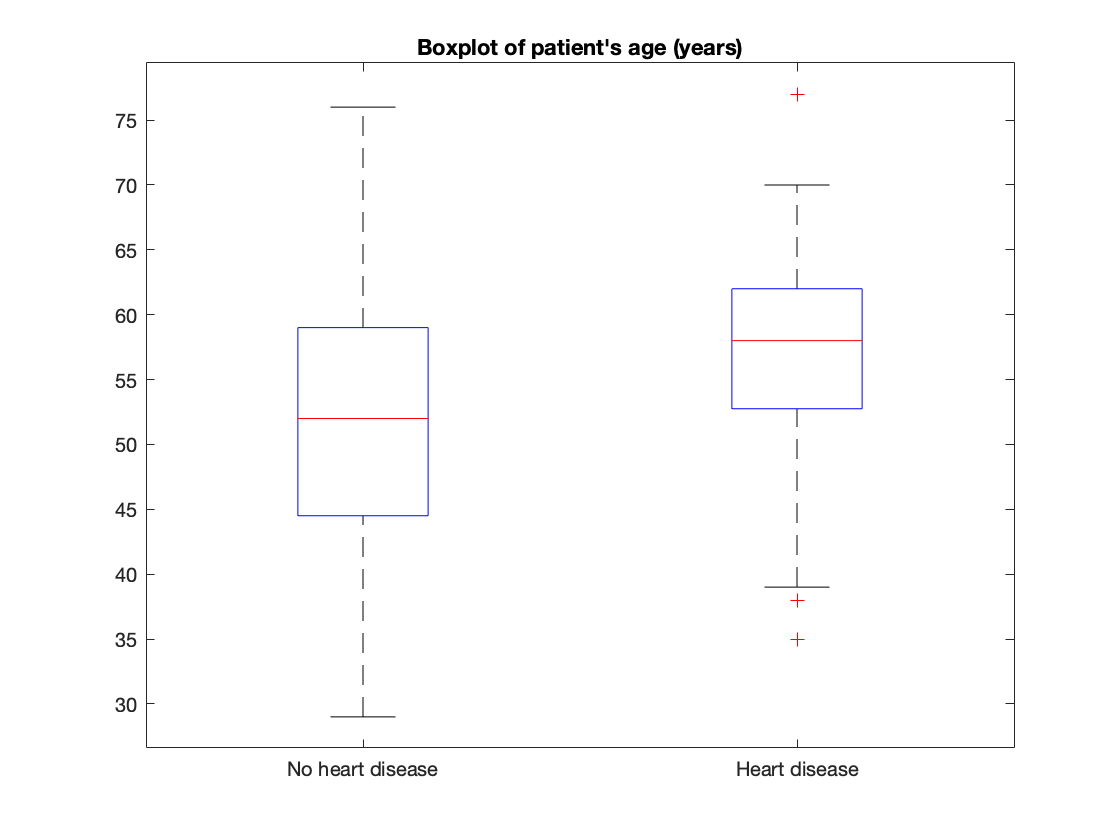

stdData = varfun(@std, numericdata);
rangeData = varfun(@range,numericdata);
iqrData = varfun(@iqr,numericdata);
%Then placing it in a table much easier to see if values were displayed vertically rather then horizontally via rows2vars function:
stats = rows2vars([meanData,stdData,rangeData,iqrData])
% Statistics summary grouped by the predictor/classifier variable "target" for numeric variables:
stat_target = rows2vars(grpstats(dataset,'target',{'mean','std','min','max','range','iqr'},'DataVars',{'age','trestbps','chol','thalach','oldpeak'}),"VariableNamingRule","preserve")
%  Statistics summary grouped by gender for numeric variables:
stat_gender = rows2vars(grpstats(dataset,'sex',{'mean','std','min','max','range','iqr'},'DataVars',{'age','trestbps','chol','thalach','oldpeak'}),"VariableNamingRule","preserve")    

### Visuallising the numeric data of the dataset (boxplots):

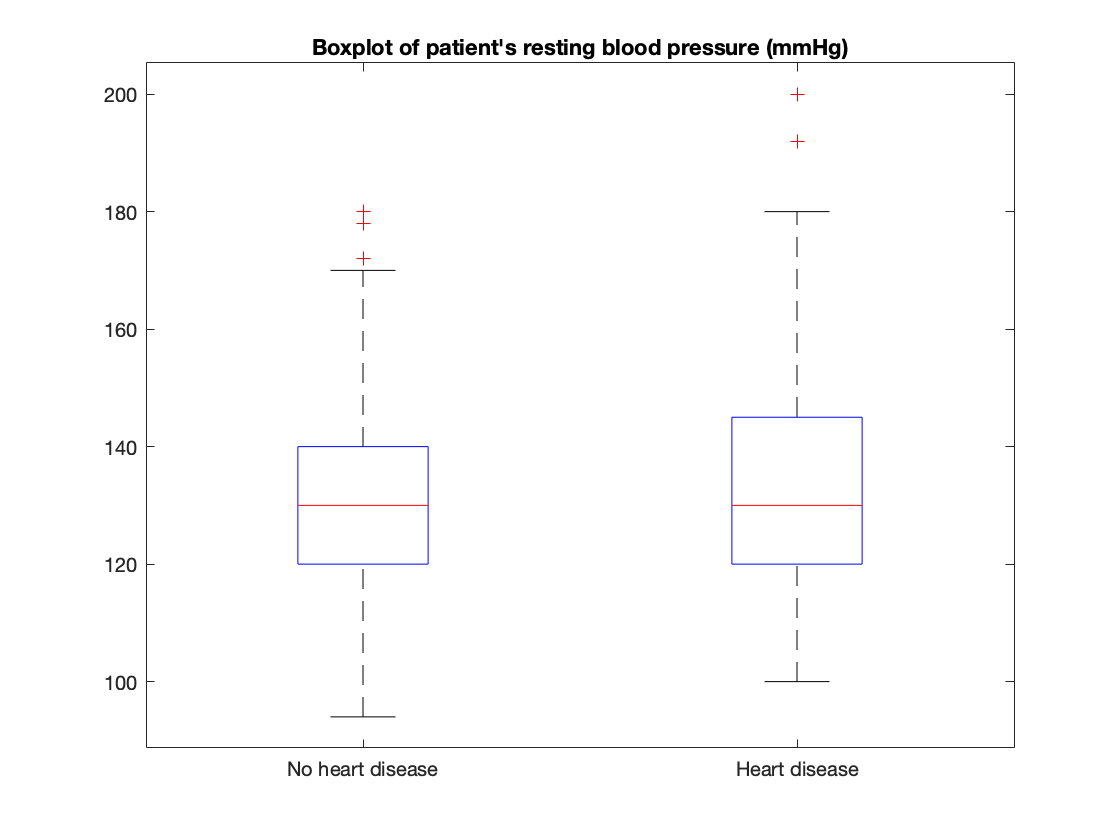

% With boxplot i will plot the numerical dataset filtered by "target" variable, as i replaced the class 1 
% and 0 with their corresponding meaning heart disease and no heart disease by xtickslabels while also

% adding a title by the title function:  

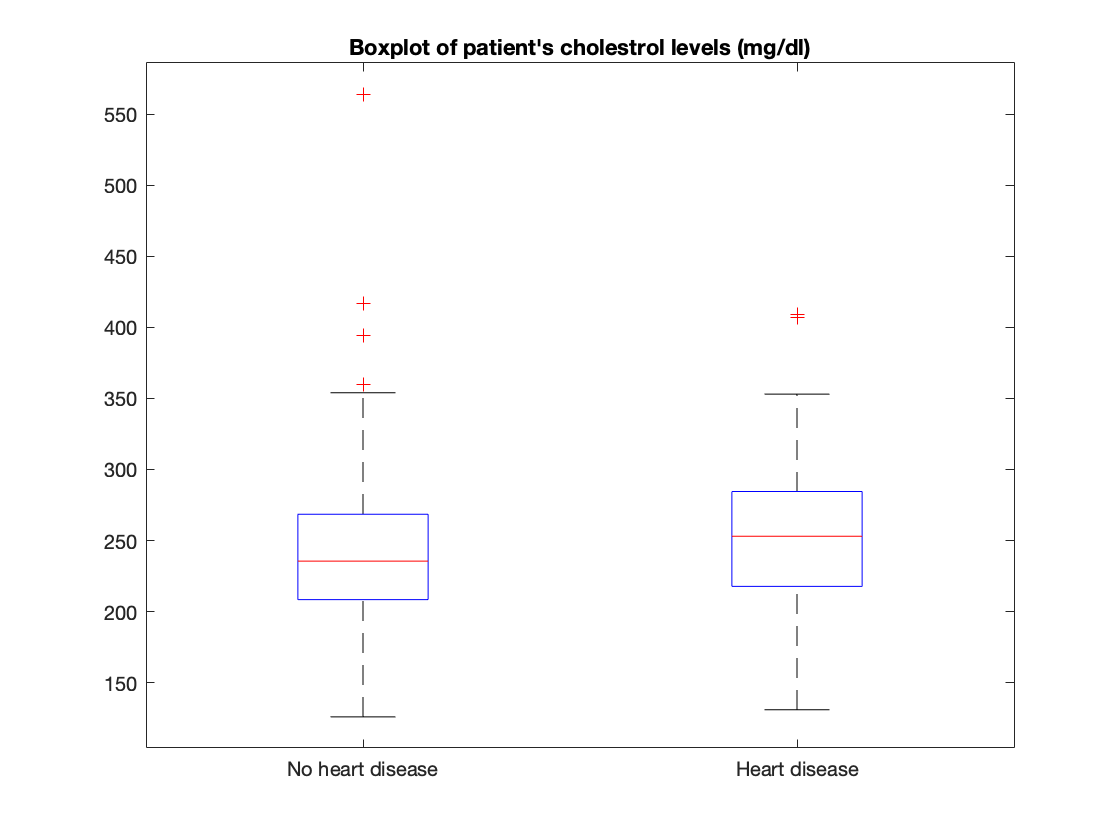

boxplot(dataset.age,dataset.target) 
title("Boxplot of patient's age (years)")
xticklabels({'No heart disease','Heart disease'})

Boxplot of patient age shows that the range (and interquatile range) for the patient not having heart disease is much larger than for the patients having heart disease ; they have a tighter age scale and  a bigger median value for age. 

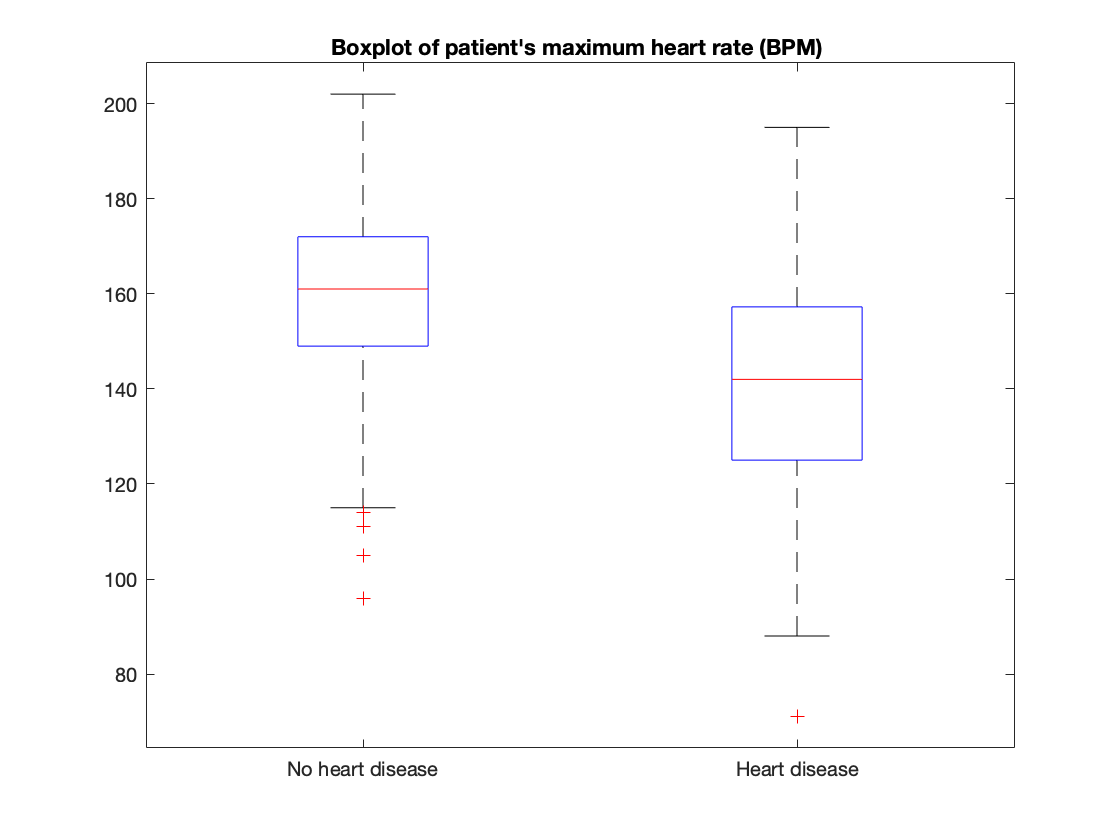

boxplot(dataset.trestbps,dataset.target) 
title("Boxplot of patient's resting blood pressure (mmHg)")
xticklabels({'No heart disease','Heart disease'})

The resting blood pressure boxplot show that the interquatile range is larger for patients with a heart disease although it does have  a smaller median value.  The minimum and maximum resting blood pressure is also higher for patients with heart disease. 

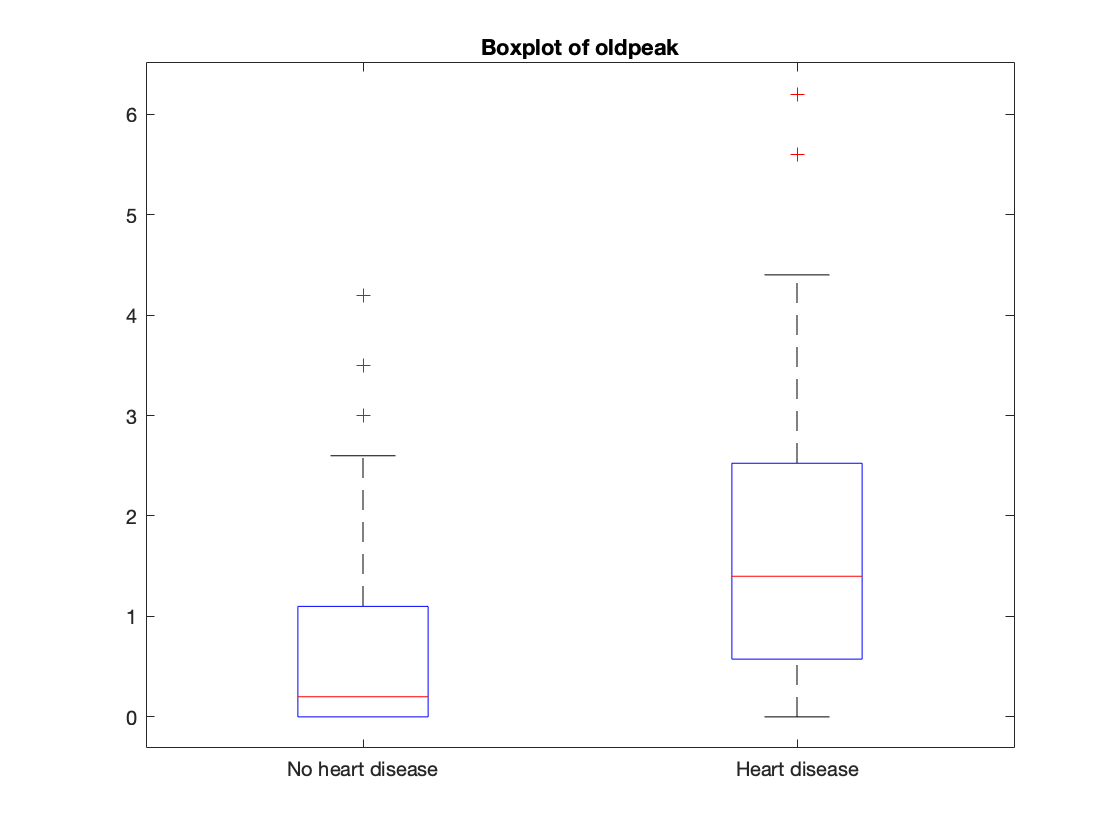

boxplot(dataset.chol,dataset.target) 
title("Boxplot of patient's cholestrol levels (mg/dl)")
xticklabels({'No heart disease','Heart disease'})

Cholestral range and interquartile range values are very simillar for patients that  have heart disease  and those that do not have heart disease.    

boxplot(dataset.thalach,dataset.target) 
title("Boxplot of patient's maximum heart rate (BPM) ")
xticklabels({'No heart disease','Heart disease'})

Boxplot shows that patients that have heart disease  have a lower heart  beat  rate. 

boxplot(dataset.oldpeak,dataset.target) 
title("Boxplot of oldpeak")
xticklabels({'No heart disease','Heart disease'})

Old peak reading is larger for people with heart disease than people who don't .  

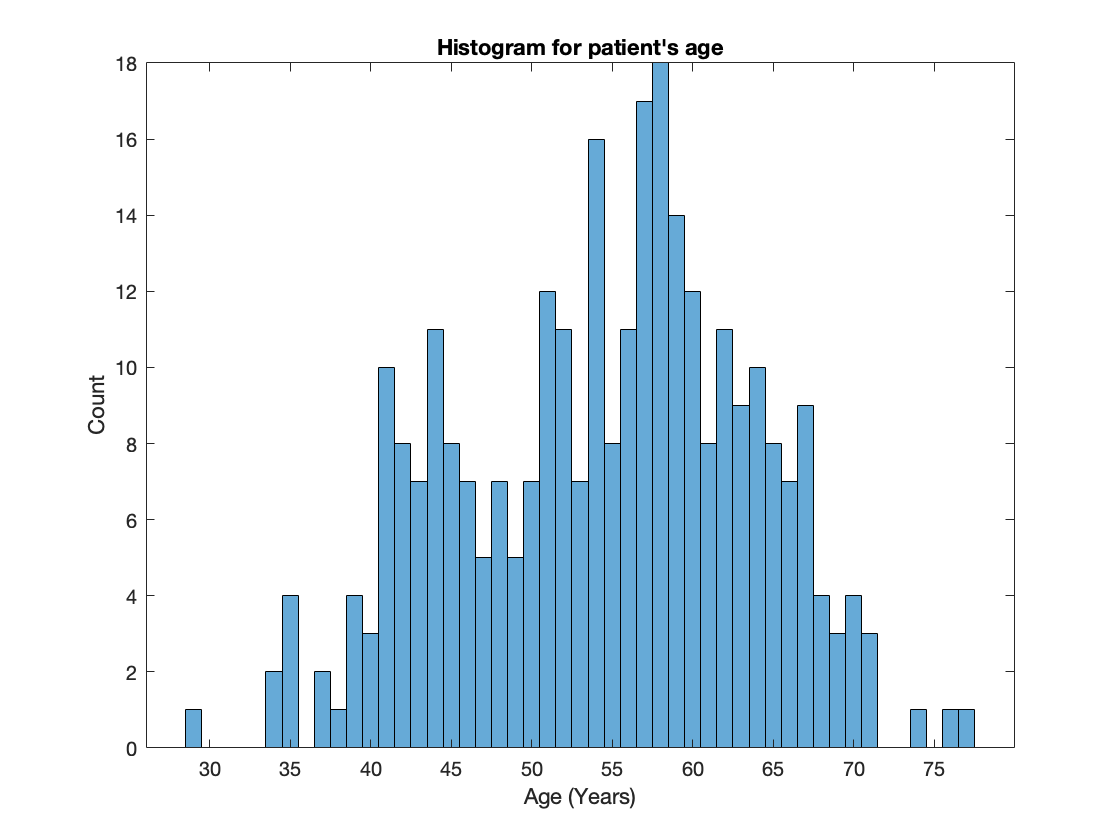

% From the boxplot we can see that there are so many outliers (a form of noisy data) in our numeric data represented

% by the red crosses such that we will take it into account when perfoming the machine learning models.

### Visuallising the distributions of the dataset (histograms):

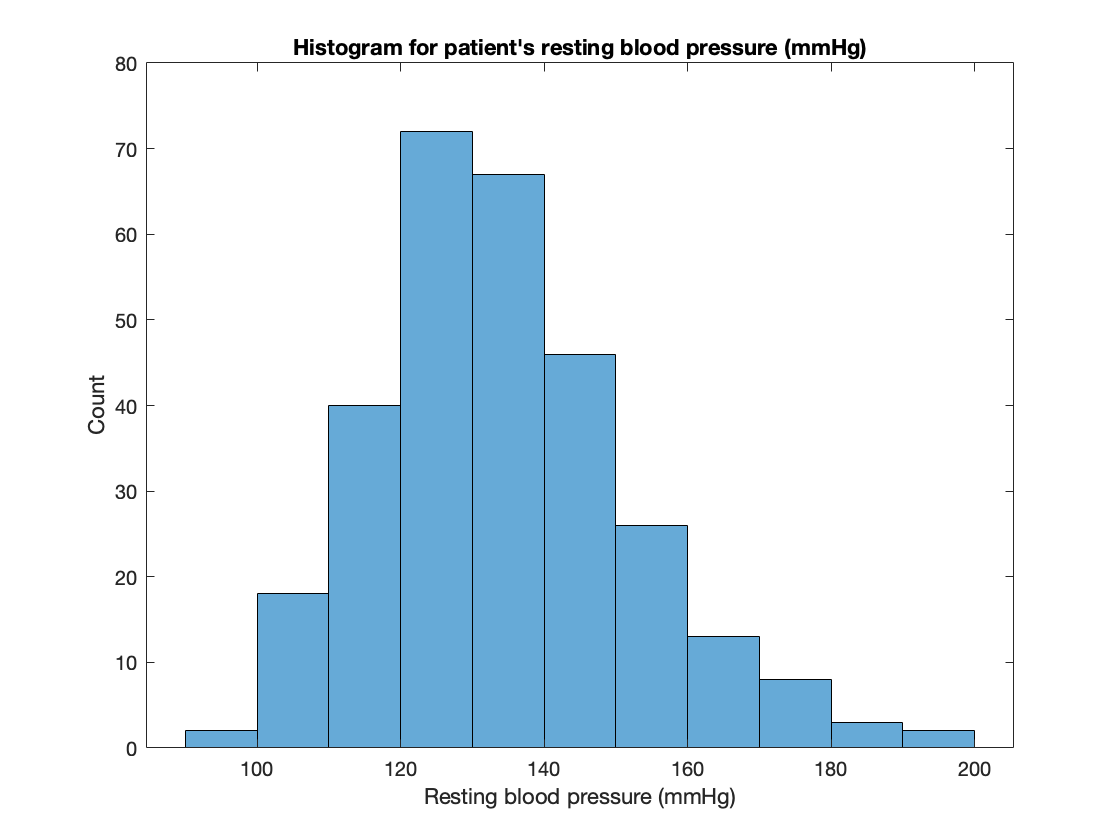

% Visuallising the distribution for each of the numerical data variables by histogram:
histogram(numericdata.age)

title("Histogram for patient's age")
xlabel("Age (Years)")
ylabel("Count")

Histogram for patient age can follow a normal distribution.

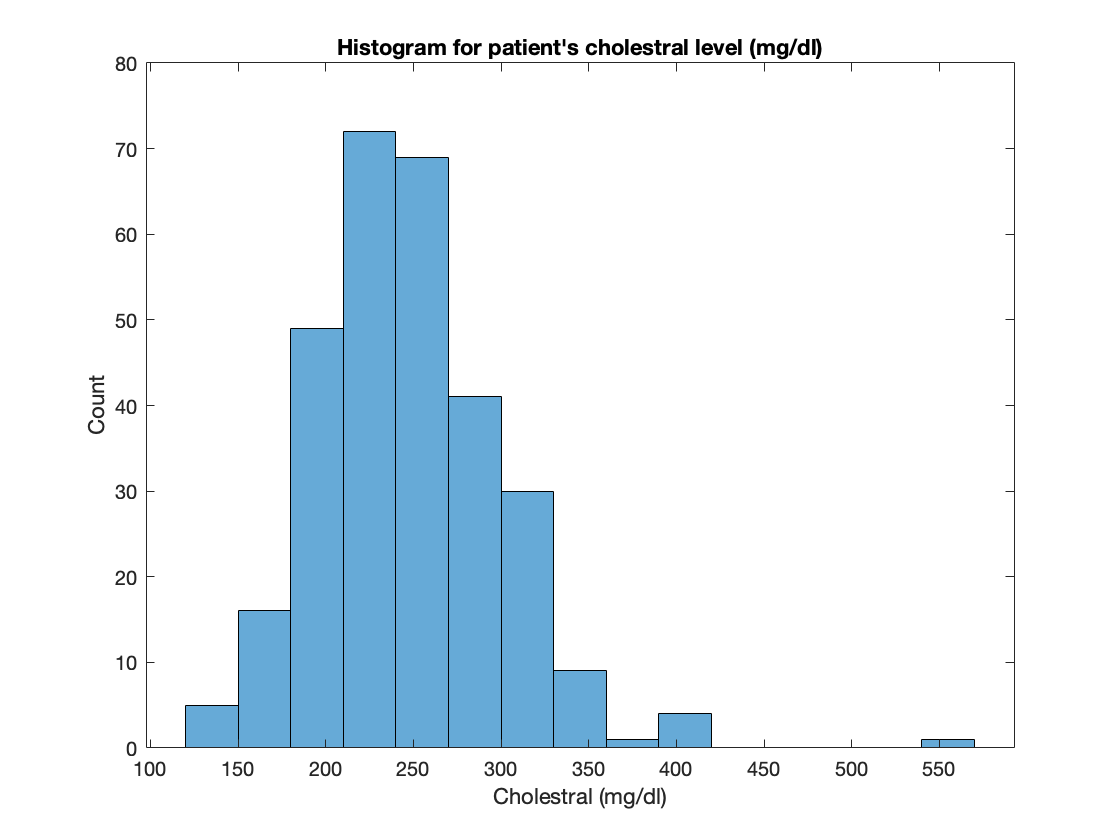

histogram(numericdata.trestbps)

title("Histogram for patient's resting blood pressure (mmHg)")
xlabel("Resting blood pressure (mmHg)")
ylabel("Count")

Historgram for patient resting blood pressure indicate normal distribution. 

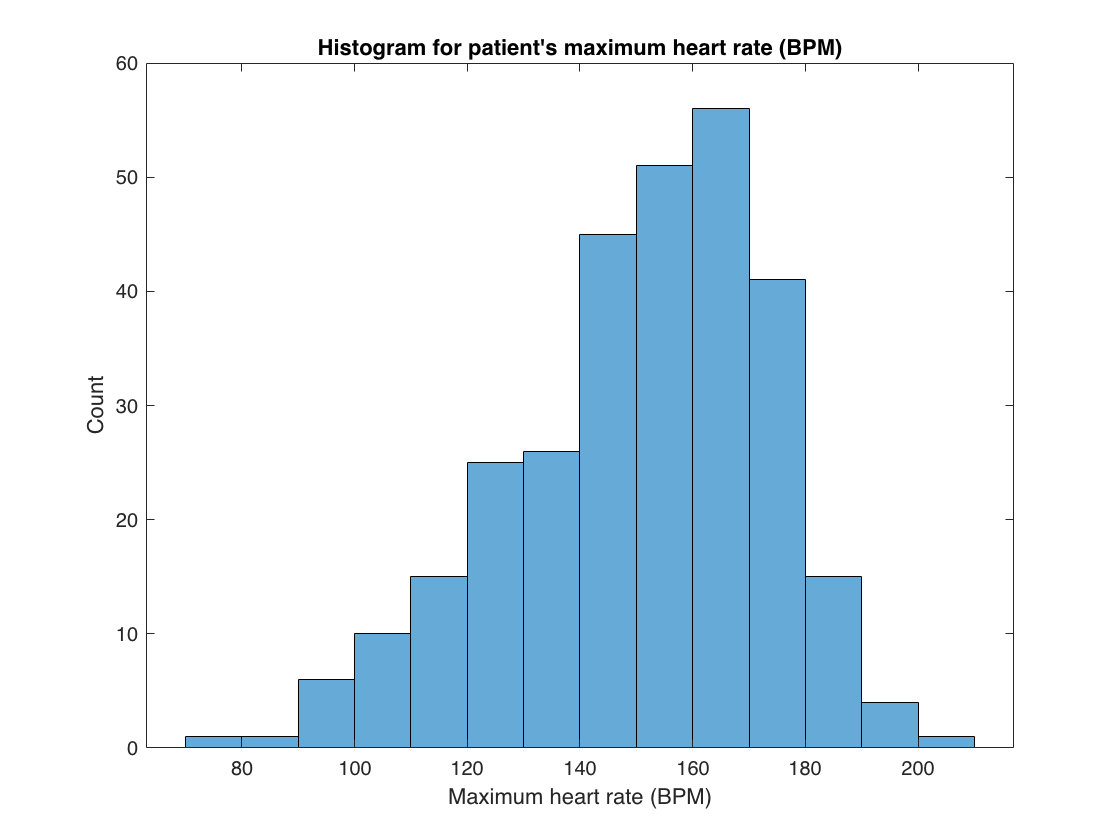

histogram(numericdata.chol)

title("Histogram for patient's cholestral level (mg/dl)")
xlabel("Cholestral (mg/dl)")
ylabel("Count")

Histogram for patient's cholestral indicates a normal distribution.

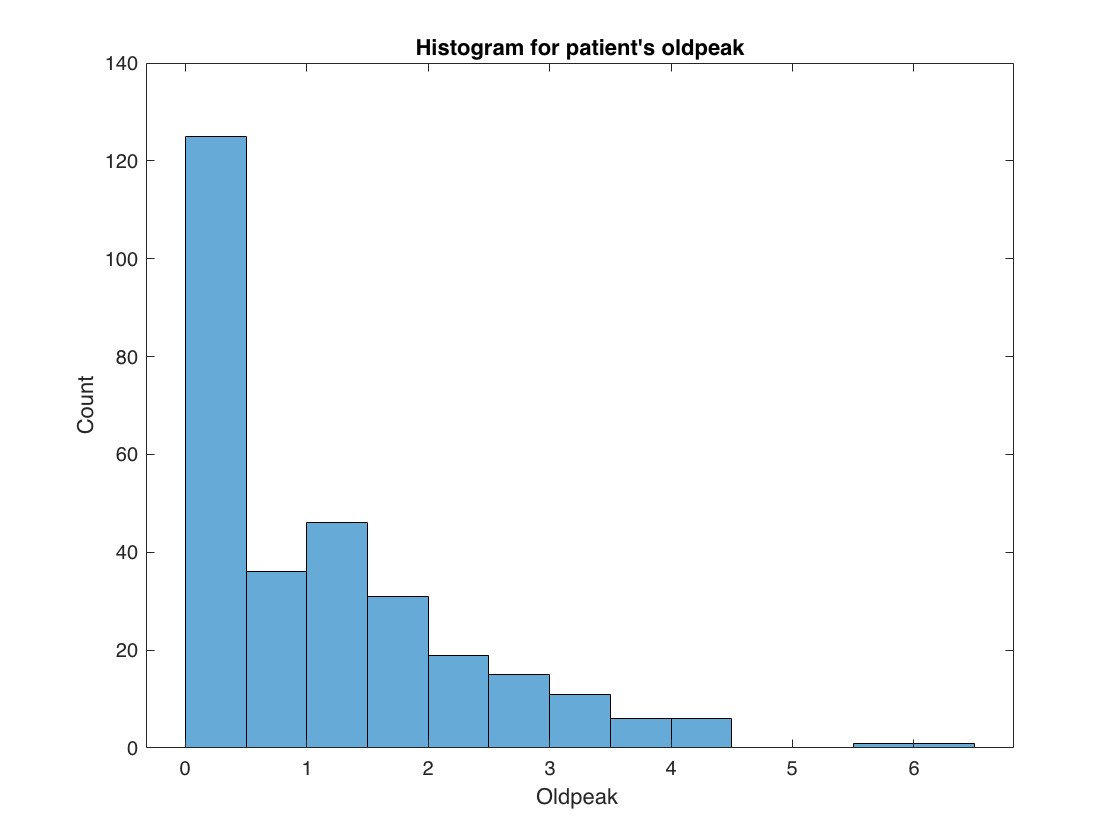

histogram(numericdata.thalach)

title("Histogram for patient's maximum heart rate (BPM)")
xlabel("Maximum heart rate (BPM)")
ylabel("Count")

Histogram for maximum heart rate can follow normal distribution.

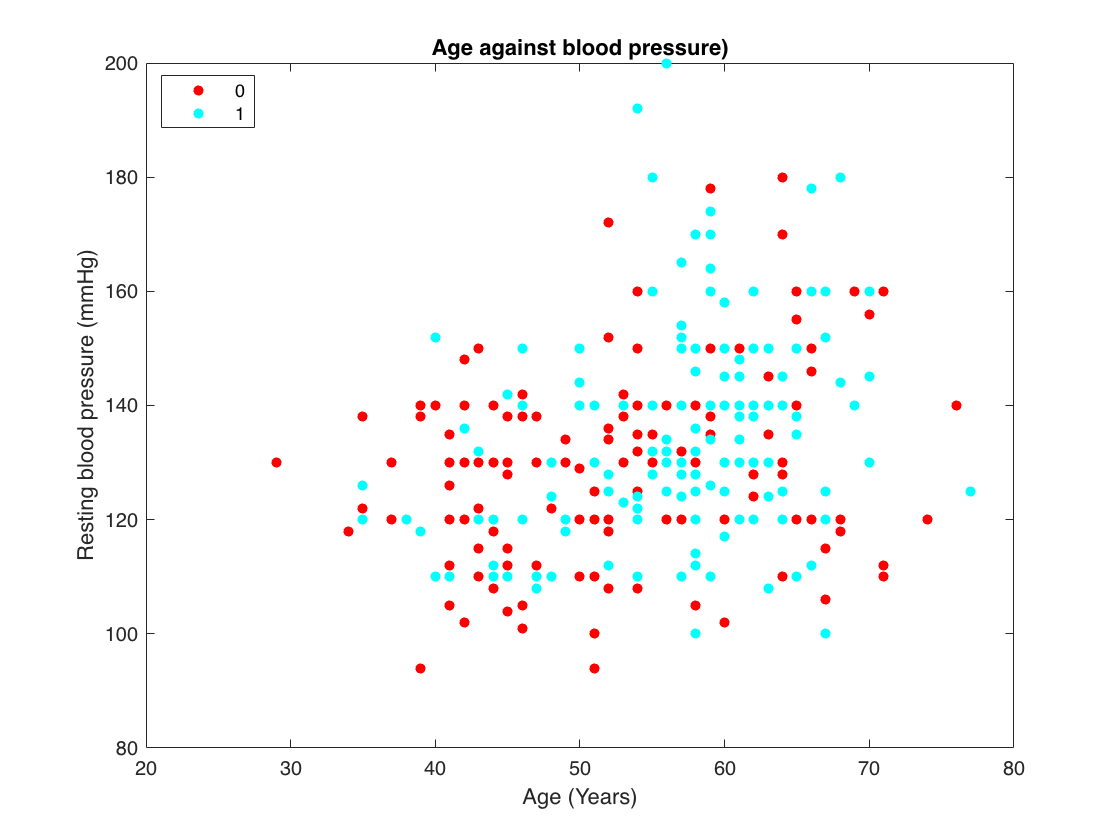

histogram(numericdata.oldpeak)
title("Histogram for patient's oldpeak")
xlabel("Oldpeak ")
ylabel("Count")

Oldpeak does not appear to follow normal distribution as it is negatively skewed.

### Visualise the scatterplots to see relationship between two numeric variables: 

% Visuallising the corellation between two numeric predictor variables for every numeric variable, in total 
% there are 10 scatter plots (5C2),Scatter plot filtered by "target" variable : where 0 is no heart disease
% and 1 is heart disease , by use of gscatter function:

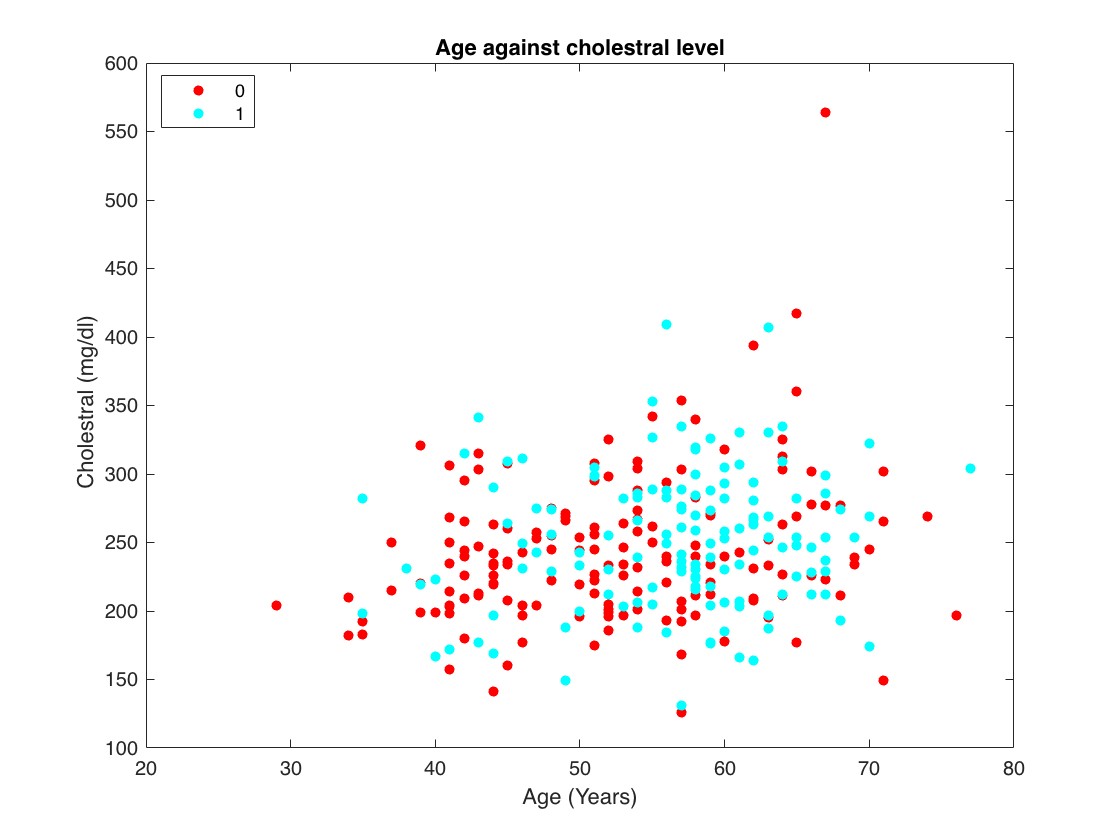

gscatter(dataset.age,dataset.trestbps,dataset.target)

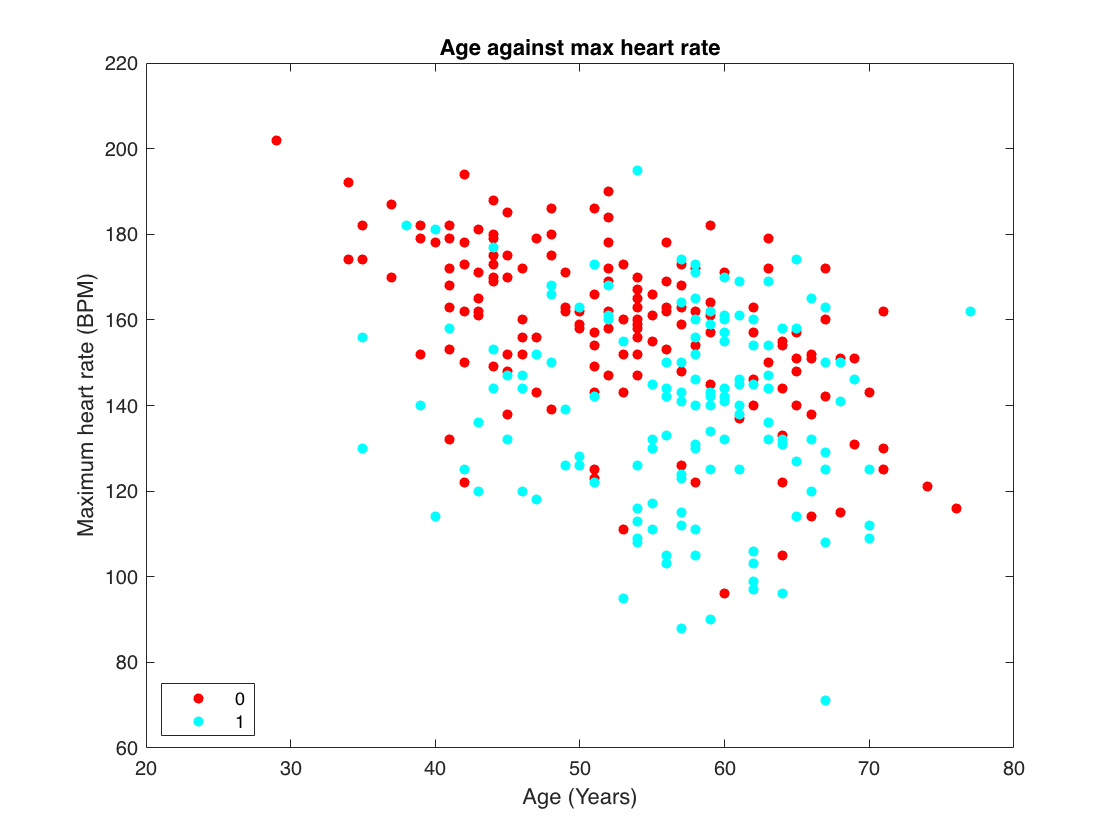

title("Age against blood pressure)")
xlabel("Age (Years)")
ylabel("Resting blood pressure (mmHg)")
gscatter(dataset.age,dataset.chol,dataset.target)

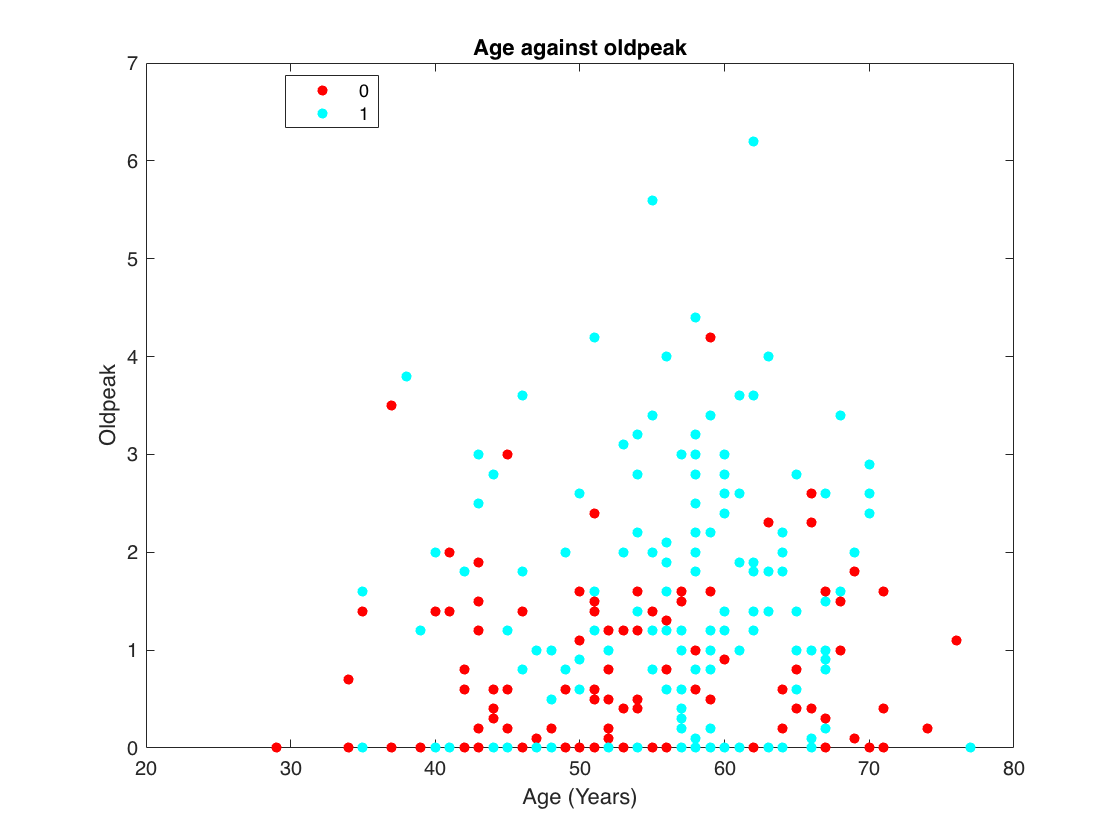

title("Age against cholestral level")
xlabel("Age (Years)")
ylabel(" Cholestral (mg/dl)") 
gscatter(dataset.age,dataset.thalach,dataset.target)

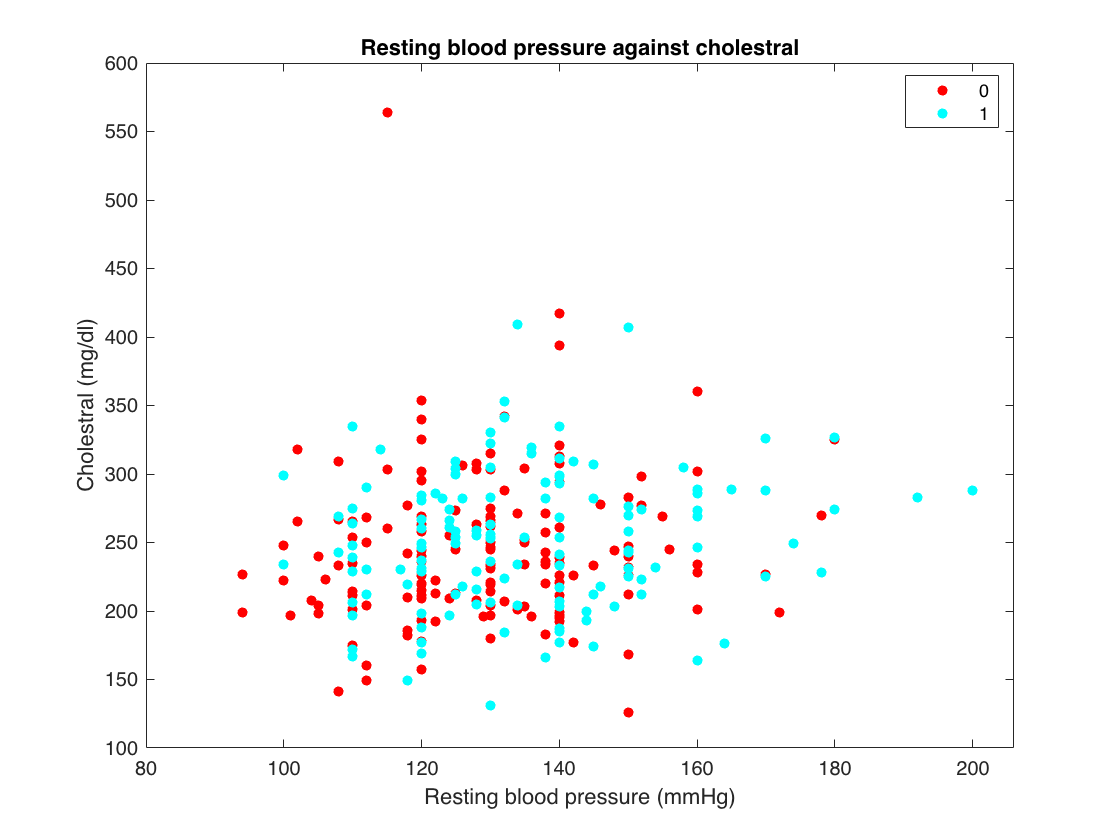

title("Age against max heart rate")
xlabel("Age (Years)")
ylabel("Maximum heart rate (BPM)") 
gscatter(dataset.age,dataset.oldpeak,dataset.target)

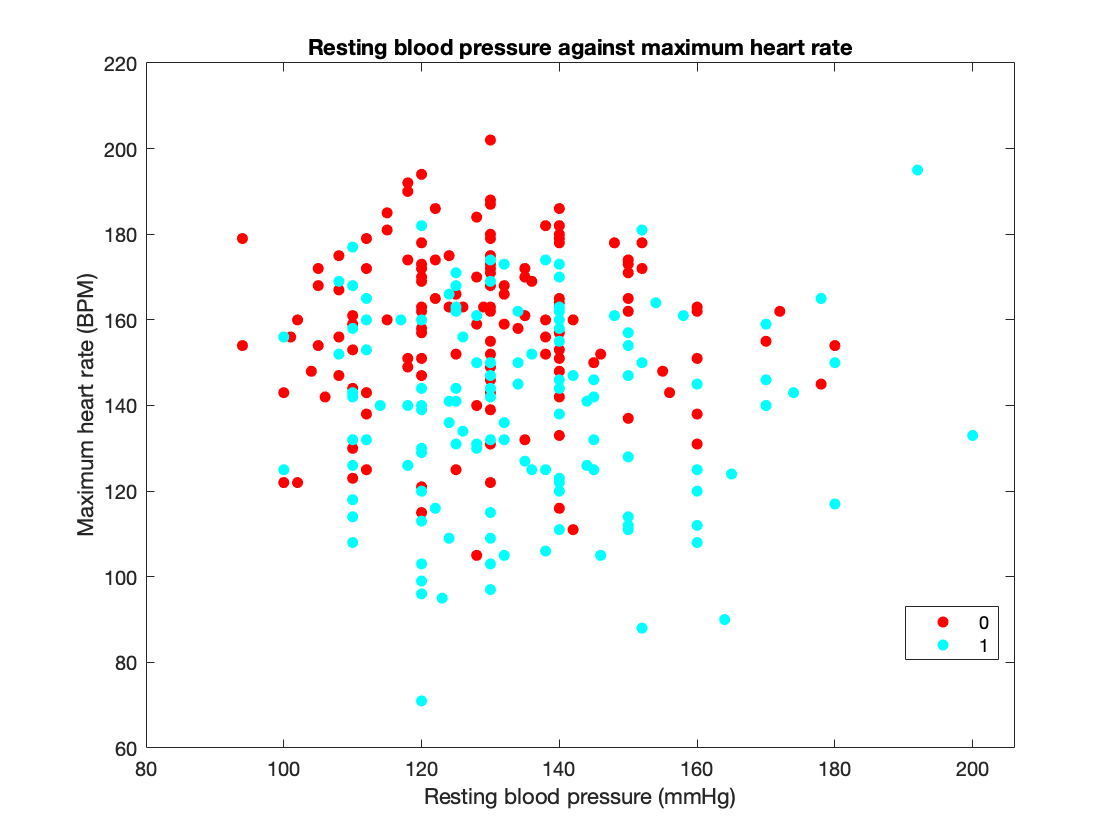

title("Age against oldpeak")
xlabel("Age (Years)")
ylabel("Oldpeak") 
gscatter(dataset.trestbps,dataset.chol,dataset.target)

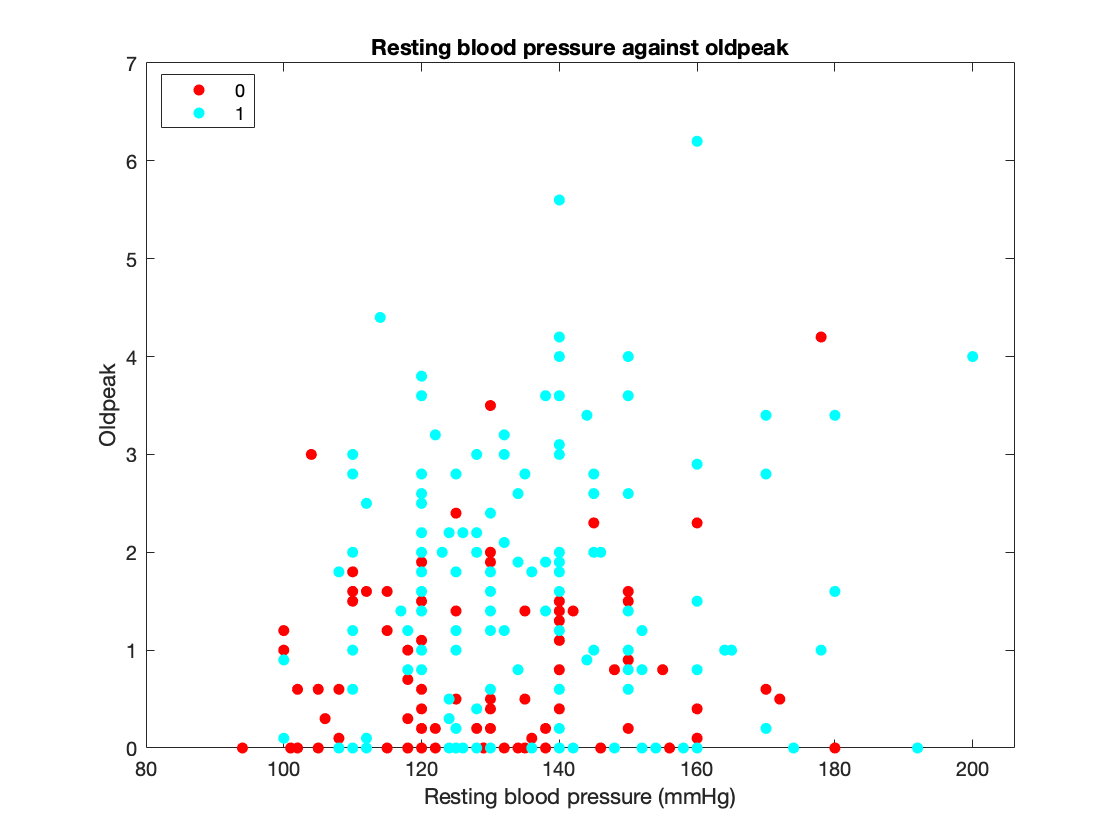

title("Resting blood pressure against cholestral")
xlabel("Resting blood pressure (mmHg)")
ylabel("Cholestral (mg/dl)") 
gscatter(dataset.trestbps,dataset.thalach,dataset.target)

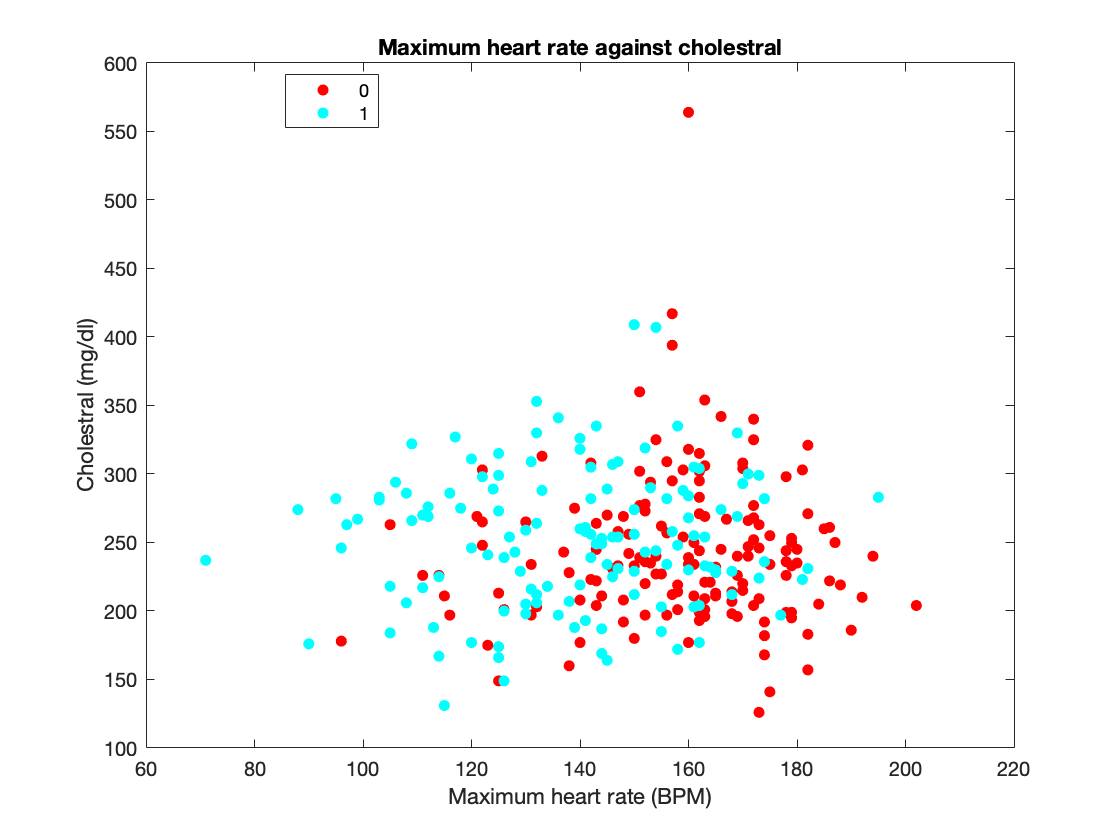

title("Resting blood pressure against maximum heart rate")
xlabel("Resting blood pressure (mmHg)")
ylabel("Maximum heart rate (BPM)") 
gscatter(dataset.trestbps,dataset.oldpeak,dataset.target)

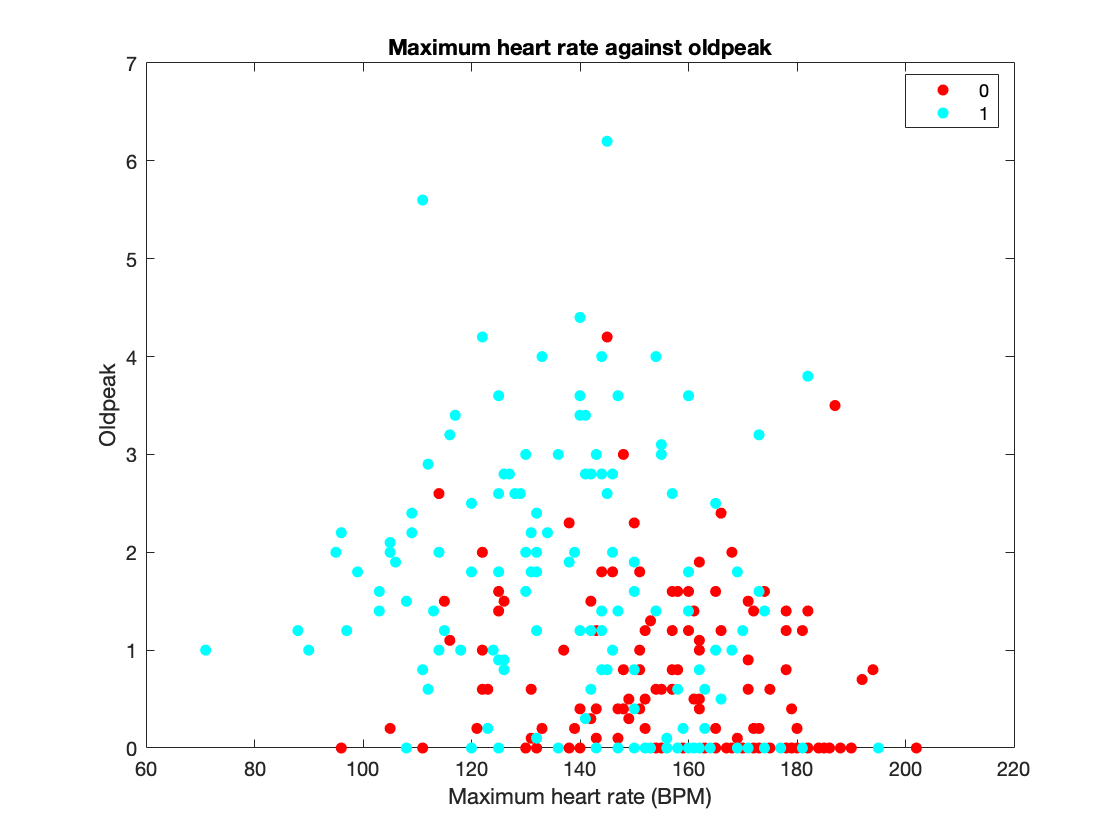

title("Resting blood pressure against oldpeak")
xlabel("Resting blood pressure (mmHg)")
ylabel("Oldpeak") 
gscatter(dataset.thalach,dataset.chol,dataset.target)

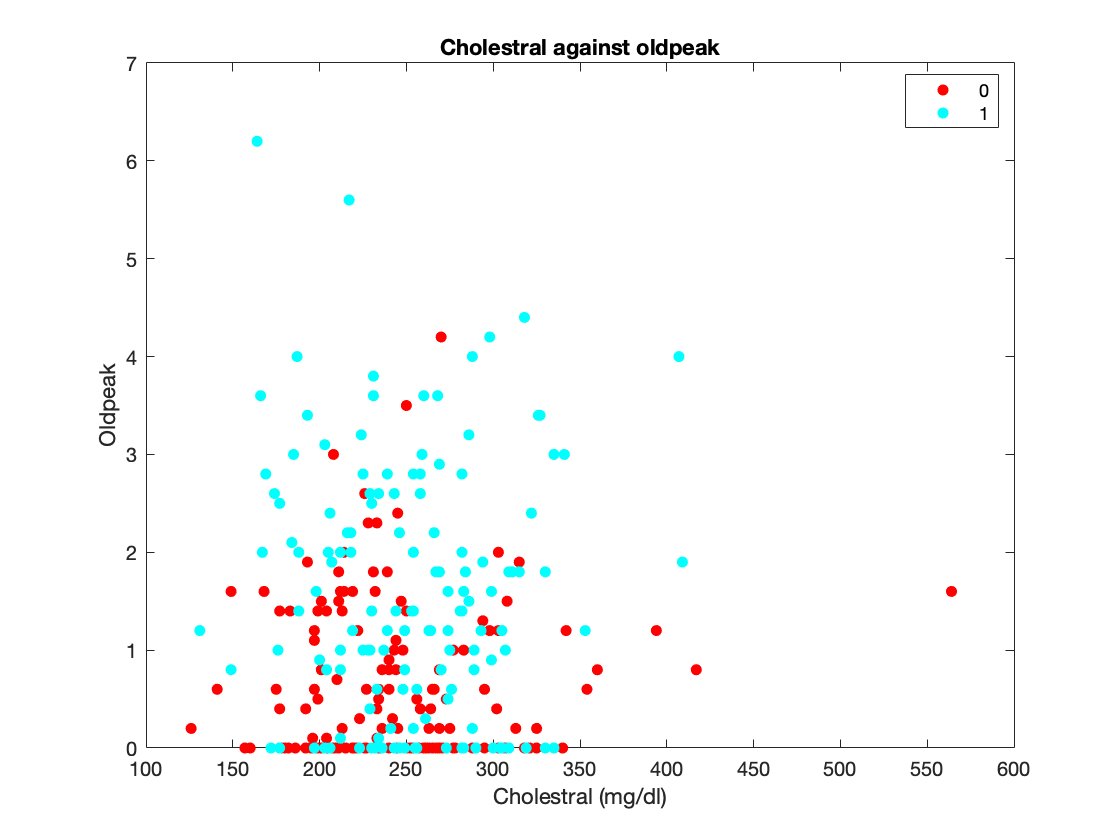

title("Maximum heart rate against cholestral")
xlabel("Maximum heart rate (BPM)")
ylabel("Cholestral (mg/dl)") 
gscatter(dataset.thalach,dataset.oldpeak,dataset.target)

title("Maximum heart rate against oldpeak")
xlabel("Maximum heart rate (BPM)")
ylabel("Oldpeak")
gscatter(dataset.chol,dataset.oldpeak,dataset.target)
title("Cholestral against oldpeak")
xlabel("Cholestral (mg/dl)")
ylabel("Oldpeak") 

### Standardise the dataset + Replot of the histograms:

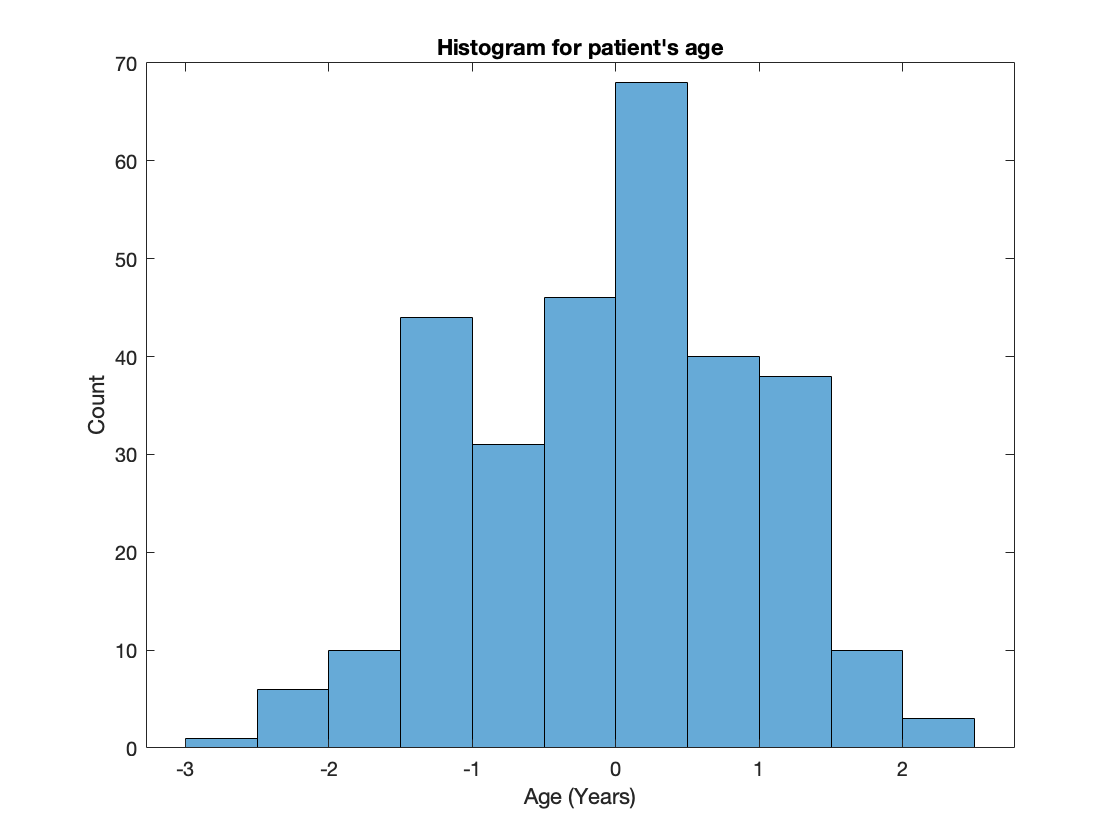

% Standardize dataset so the different numeric variable have a  common scale
dataset.age = normalize(dataset.age);
dataset.trestbps = normalize(dataset.trestbps);
dataset.chol = normalize(dataset.chol);
dataset.thalach = normalize(dataset.thalach);
dataset.oldpeak = normalize(dataset.oldpeak);

numericdata.age = normalize(numericdata.age);
numericdata.trestbps = normalize(numericdata.trestbps);
numericdata.chol = normalize(numericdata.chol);
numericdata.thalach = normalize(numericdata.thalach);
numericdata.oldpeak = normalize(numericdata.oldpeak);


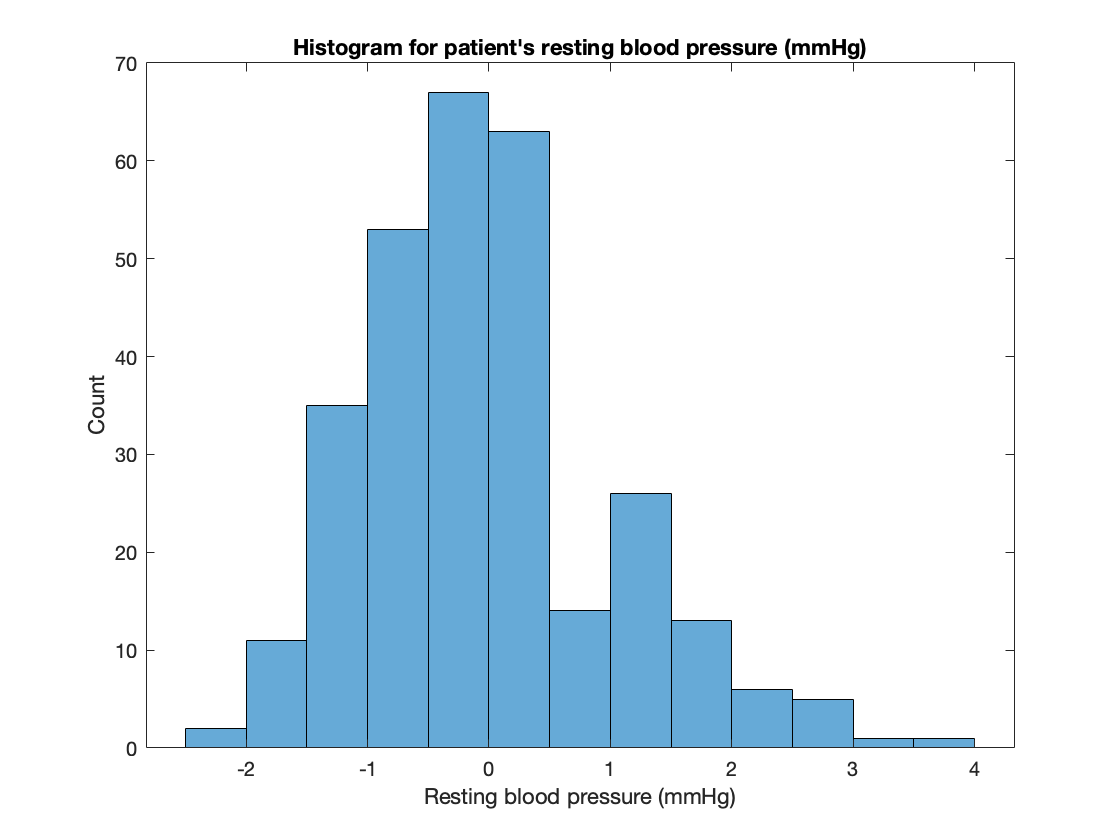

% Replot the histograms to see if the standardized dataset follows a normal
% distribution: 
histogram(dataset.age)
title("Histogram for patient's age")

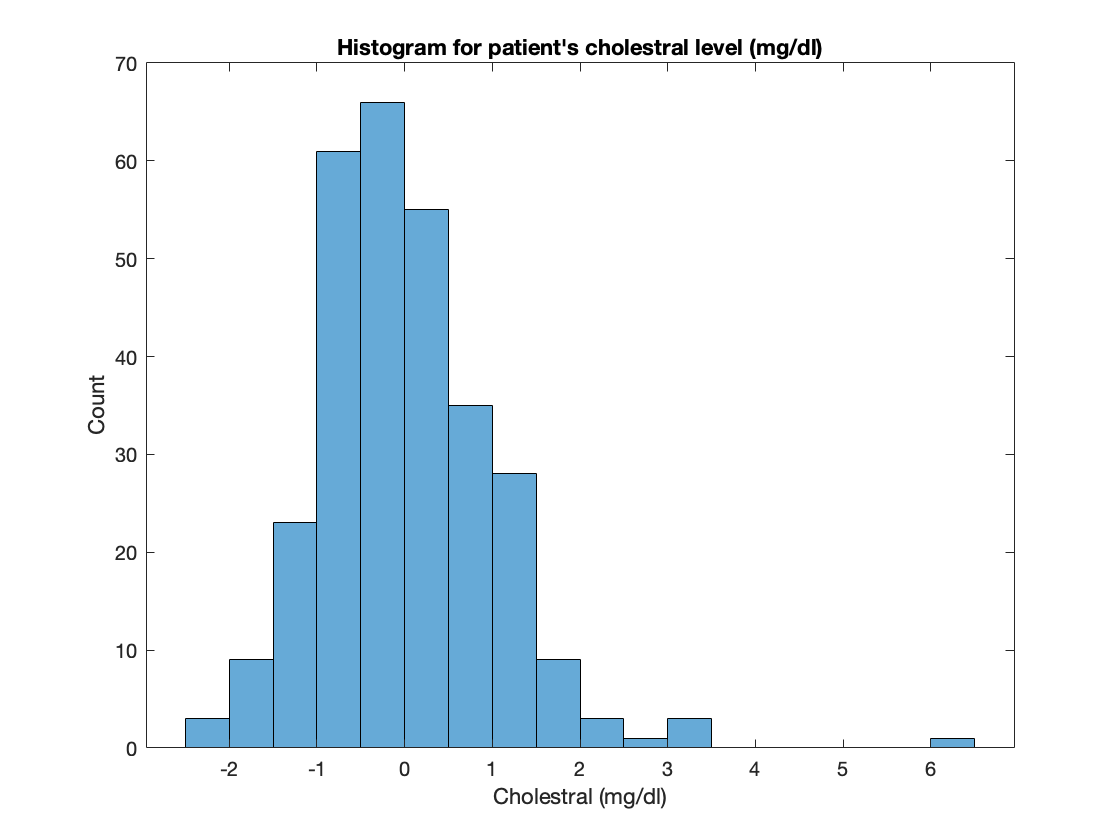

xlabel("Age (Years)")
ylabel("Count")
histogram(dataset.trestbps)
title("Histogram for patient's resting blood pressure (mmHg)")

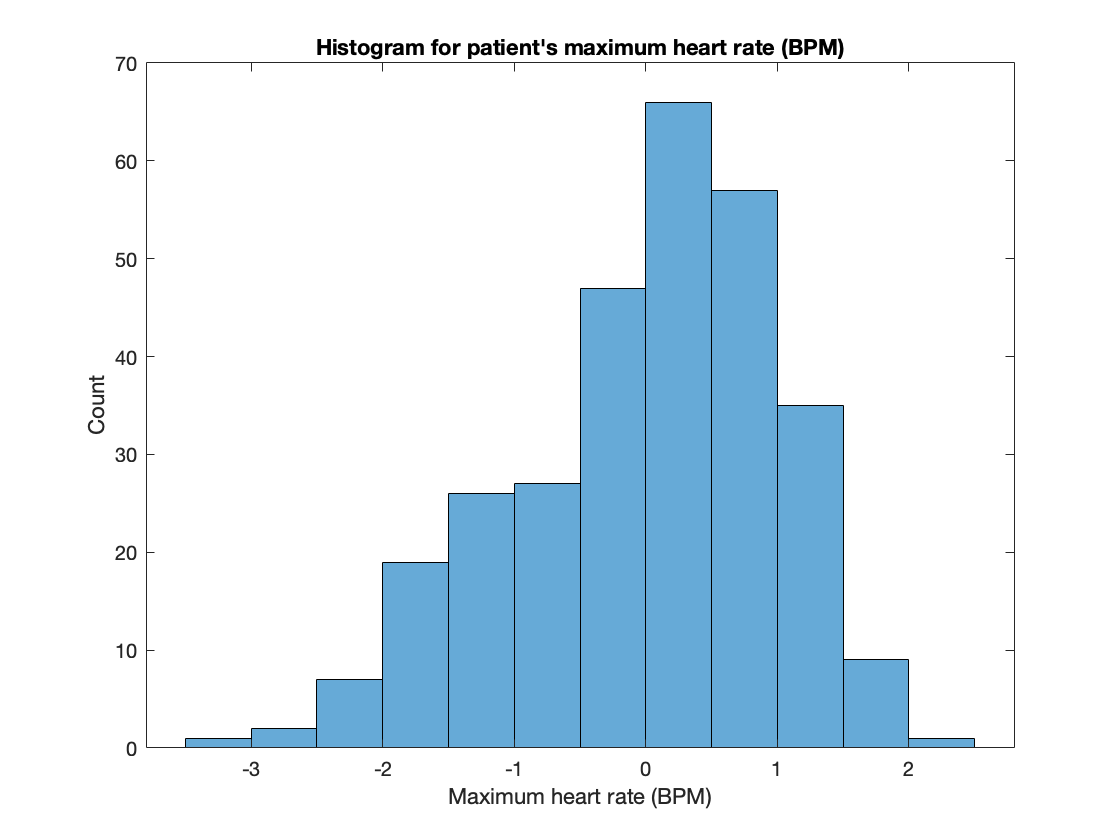

xlabel("Resting blood pressure (mmHg)")
ylabel("Count")
histogram(dataset.chol)
title("Histogram for patient's cholestral level (mg/dl)")

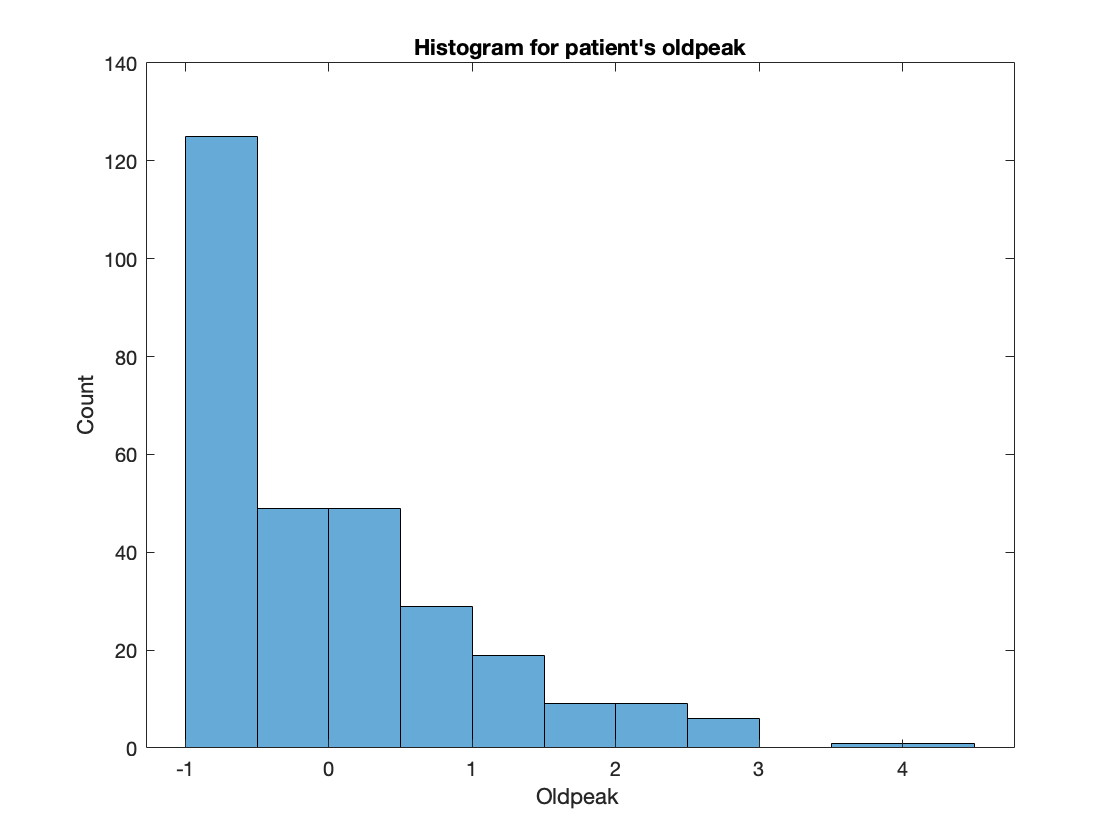

xlabel("Cholestral (mg/dl)")
ylabel("Count")
histogram(dataset.thalach)
title("Histogram for patient's maximum heart rate (BPM)")

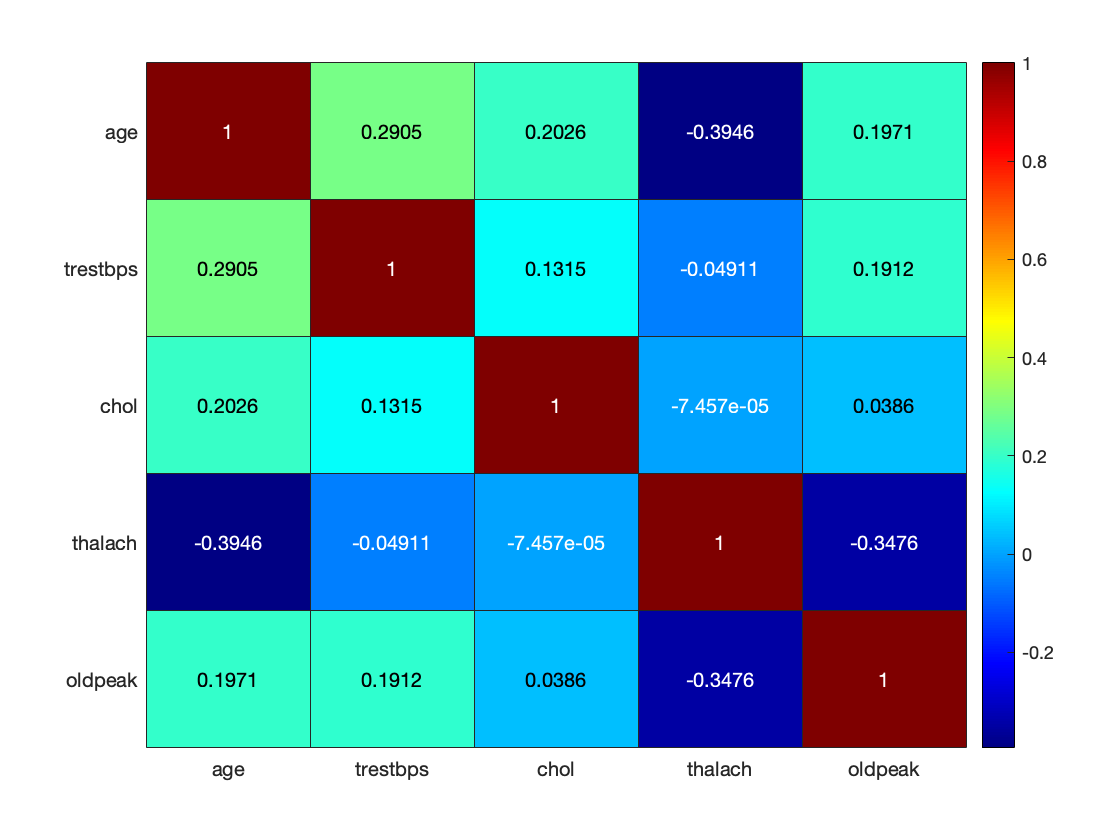

xlabel("Maximum heart rate (BPM)")
ylabel("Count")
histogram(dataset.oldpeak)
title("Histogram for patient's oldpeak")
xlabel("Oldpeak ")
ylabel("Count")

% After standardising the dataset, i can see from the histogram all of the variables except for oldpeak follows a normal distribution 

% To see the corellation between the numeric variables of the dataset i plotted a heatmap of the corellation matrix : 
% This is done via the corr() function embedded with the heatmap function, where i placed argument so that you can see the 
% correlation value for each variable and by color.
heatmap(corr(numericdata.Variables),'Colormap', jet, 'ColorbarVisible', 'on','XDisplayLabels', {'age','trestbps','chol','thalach','oldpeak'},'YDisplayLabels',{'age','trestbps','chol','thalach','oldpeak'})
% From the correlation heatmap, there is no two different numeric variables that are strongly corellated 
% with each other so would not have to drop any features for my algotithms.

### Visuallising the categorical data types of the data:

% Categorical variables (nominal) : sex , cp , fbs , restecg , exang ,

     0      160 
     1      137 


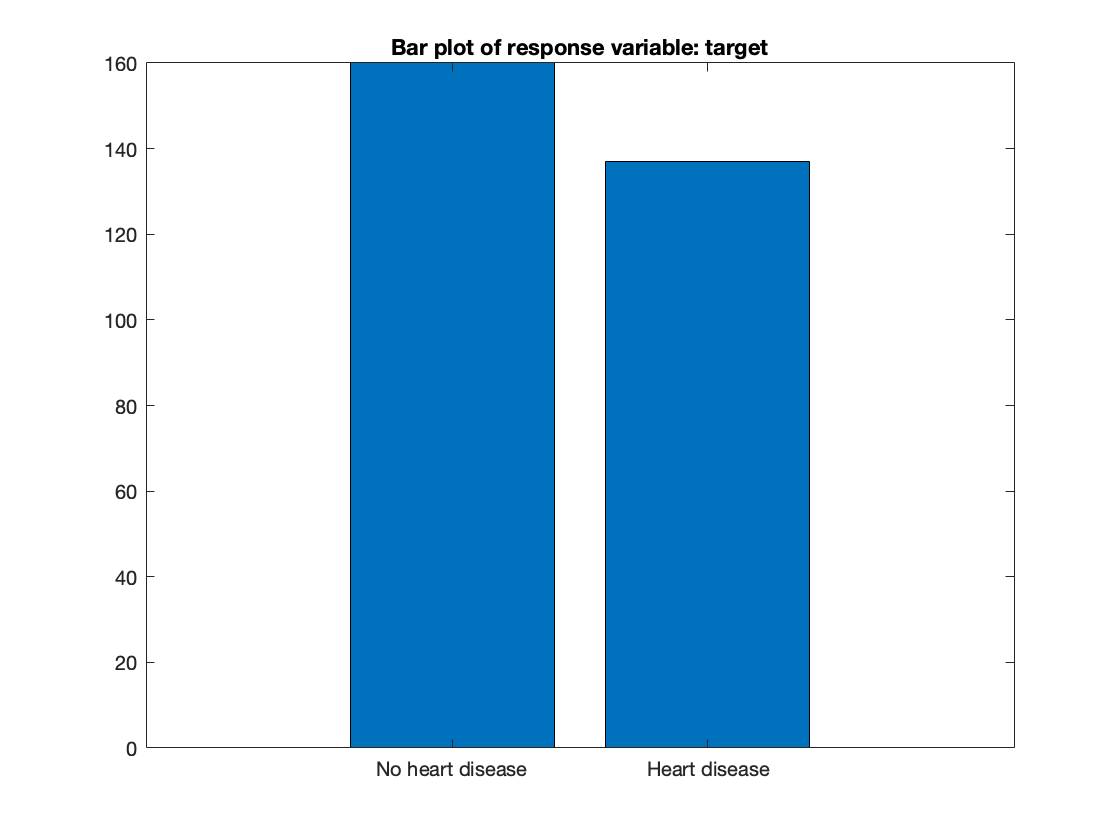

% slope , thal and target (variable of intrest / the predicted/classified variable) dataset.sex)
% and also categorical variable (ordinal) : ca
% Plotting bar plot and filter by target for  predictor variables.

%  First  plot the bar plot of the response variable target

summary(dataset.target) 
%bar plot of the dependent / classifer  variable target, done by using summary funnction to get count of the
% possible outcome 0 and 1 which coresponds to No and Yes with regards to heart disease.
bar([160,137])
title("Bar plot of response variable: target")
xticklabels(["No heart disease","Heart disease"])

     0       96 
     1      201 


Dataset is slightly imbalance as the response variable ("target") variable has approximantly the same amount of outcomes for the classes. So we can compare it as a normal classification problem.

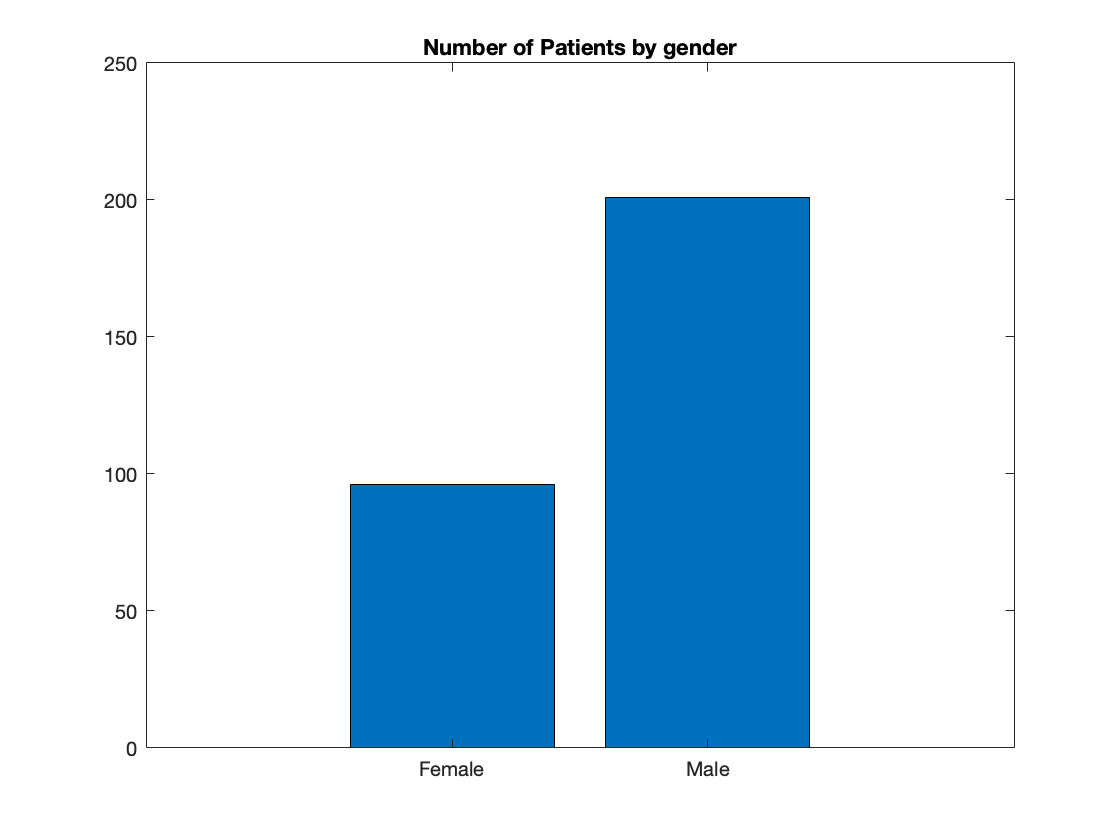

% Now i am going to plot the barplot for each of the other categorical data which are the response variables
% intended to predict the classife variable target. This will be achieved by using the summary function to
% get the count of diffent categories. Then plotting using the bar plot as and replacing the binary/multinomial 

% values with their actual definition:

summary(dataset.sex) % Get the count of the variable

     1       23 
     2       49 
     3       83 
     4      142 


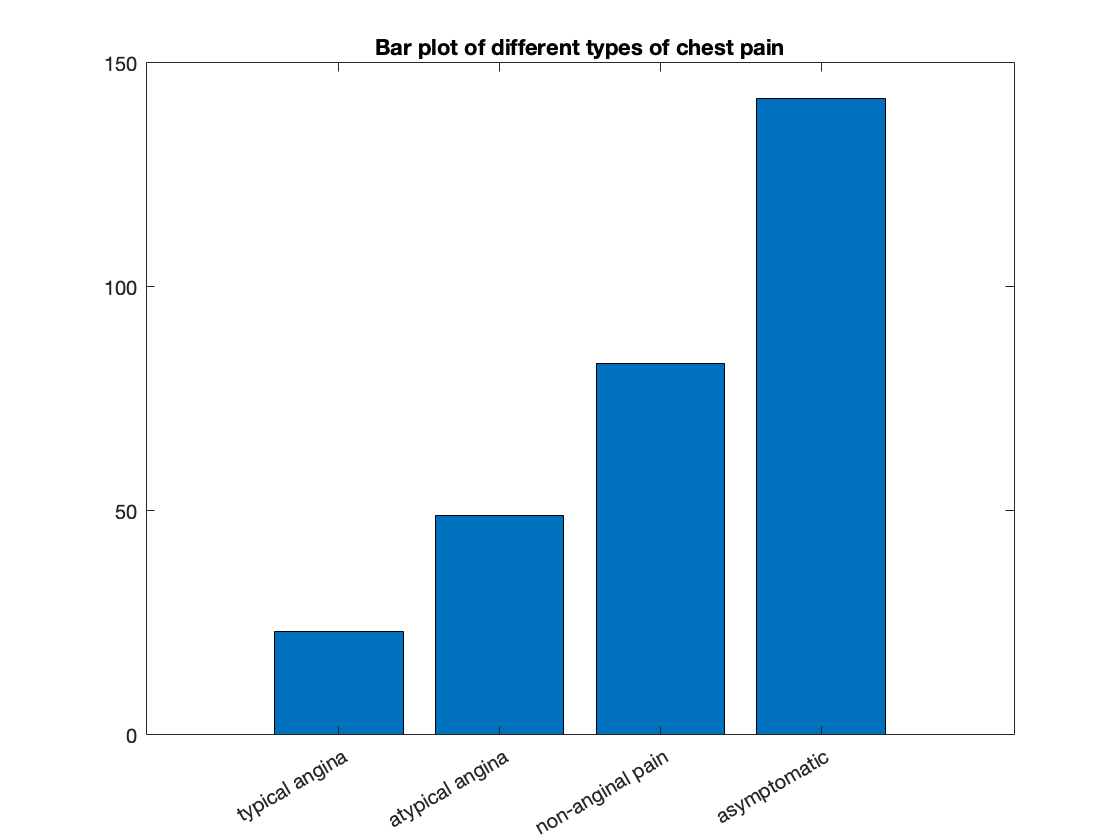

bar([96,201]) % plot values with bar function
title("Number of Patients by gender") % set  the title 
xticklabels(["Female","Male"])% the definition of the value for the variable

There are twice as many male patients as female patient.

summary(dataset.cp) % count for chest pain
bar([23,49,83,142]) % plot the cp values onto the bar plot

     0      254 
     1       43 


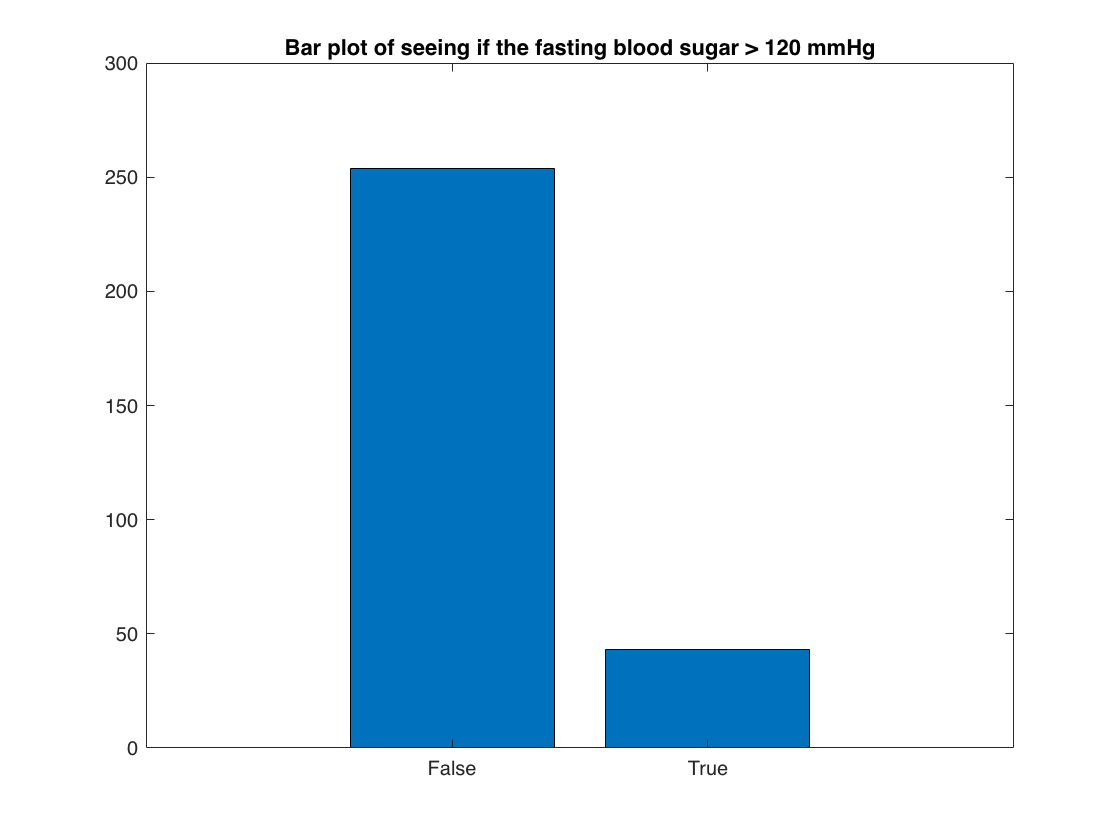

title("Bar plot of different types of chest pain") % set the title
xticklabels(["typical angina", "atypical angina", "non-anginal pain" ,"asymptomatic"]) % set the defined class for the variable
xtickangle(30)% set angle to 30 degrees to see the x labels of barplot to see label  

Asymptomatic type of chest pain is the most common diagnosed chest pain for patients while typical and atypical angina are the least.

summary(dataset.fbs) % count of patient having fasting blood sugar

     0      147 
     1        4 
     2      146 


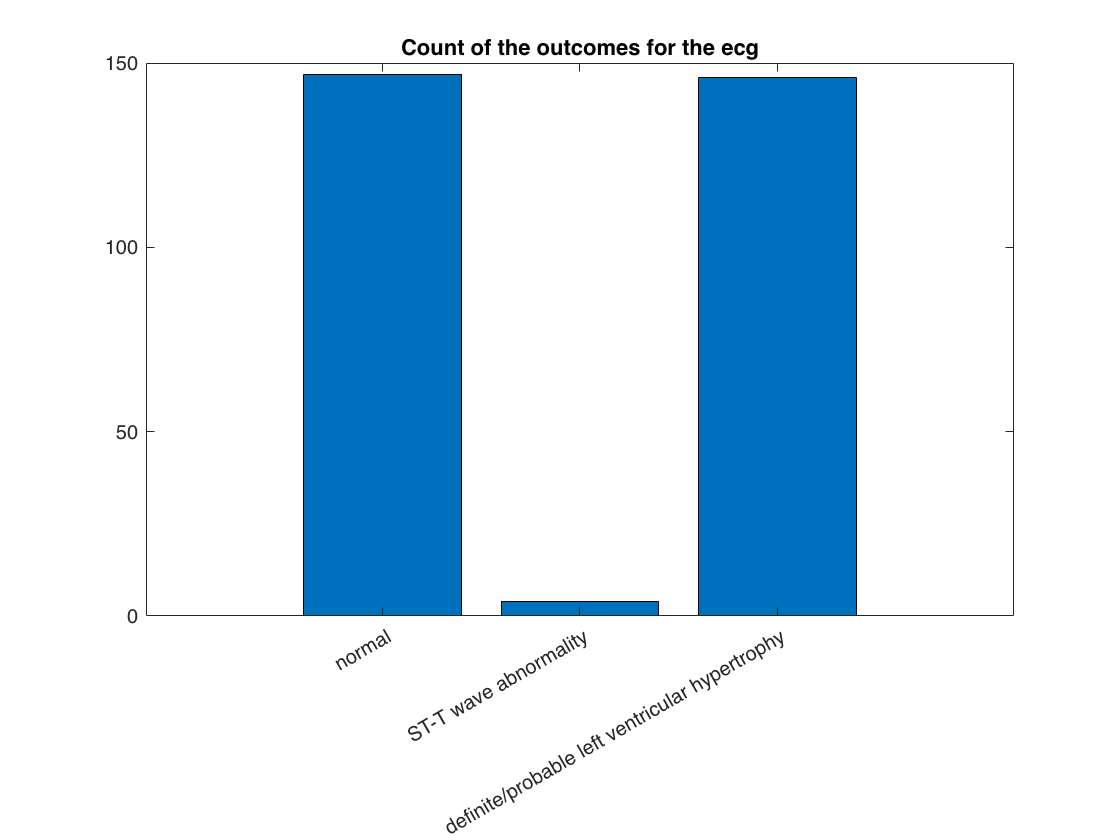

bar([254,43]) % set the values of fbs to bar plot
title("Bar plot of seeing if the fasting blood sugar > 120 mmHg") % set title
xticklabels(["False","True"]) % set label to define the class value of the cp variable

Most people have fasting blood sugar which is less than 120  mmHg which is good.

summary(dataset.restecg) % count of  restecg vairiable
bar([147,4,146]) % set the count of ecg to the bar plot

     0      200 
     1       97 


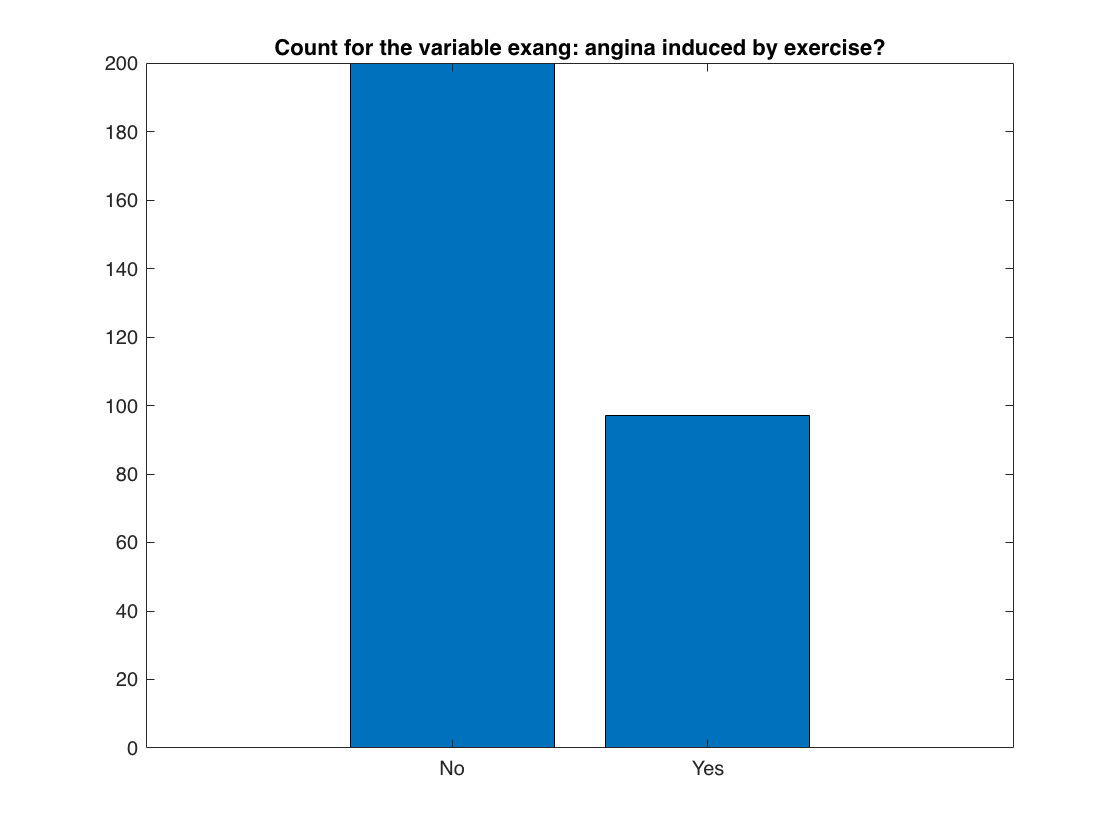

title("Count of the outcomes for the ecg") % title for bar plot
xticklabels(["normal" ,"ST-T wave abnormality","definite/probable left ventricular hypertrophy"]) % defined label for ecg variable classes.
xtickangle(30)% set angle (30 degrees) to see label clearly

Patients ecg results are normal however people that show sign of left ventricular hypertrophy which indicates heart problem have the same count and so are equally as likely as normal ecg result.

summary(dataset.exang) % count of exang variable

     1      139 
     2      137 
     3       21 


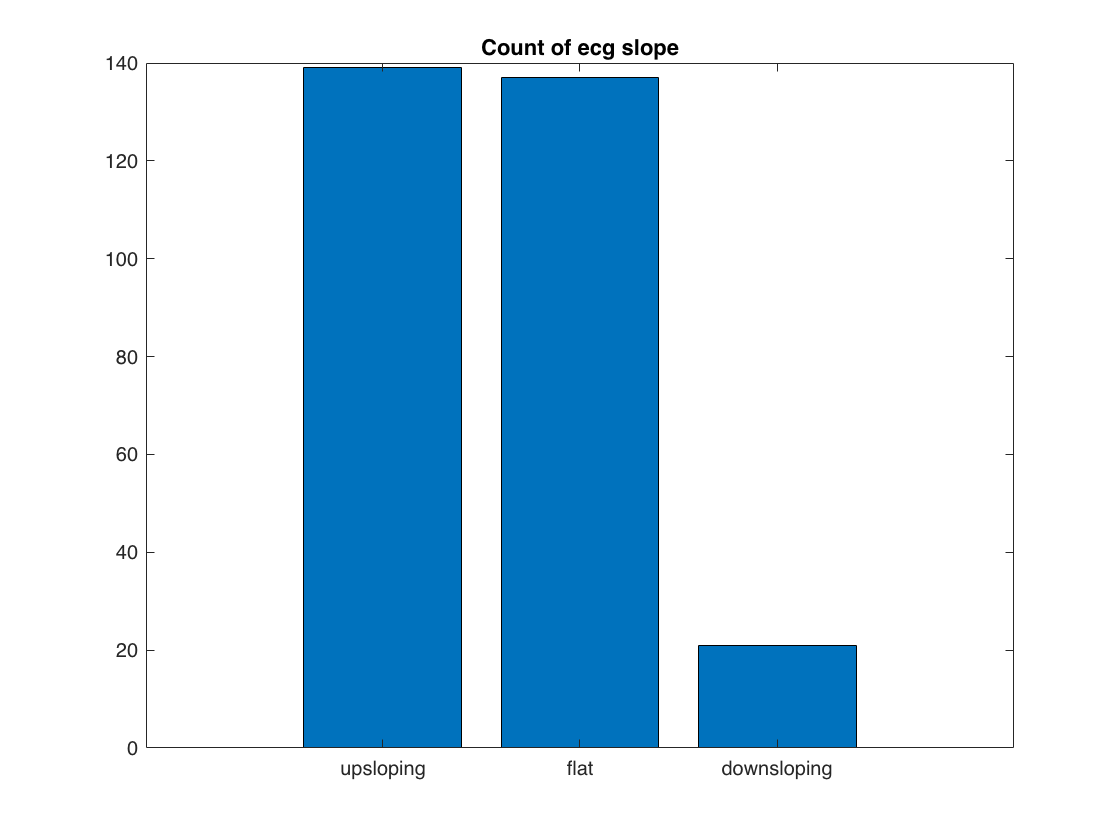

bar([200,97]) % place the count values to the bar plot function to get the plot
title("Count for the variable exang: angina induced by exercise?") % set the title 
xticklabels(["No","Yes"])  % Set X labels to get define the class of the variable

Majority of angina chest pain is not induced by excersise.

summary(dataset.slope) % count  of slope

     3      164 
     6       18 
     7      115 


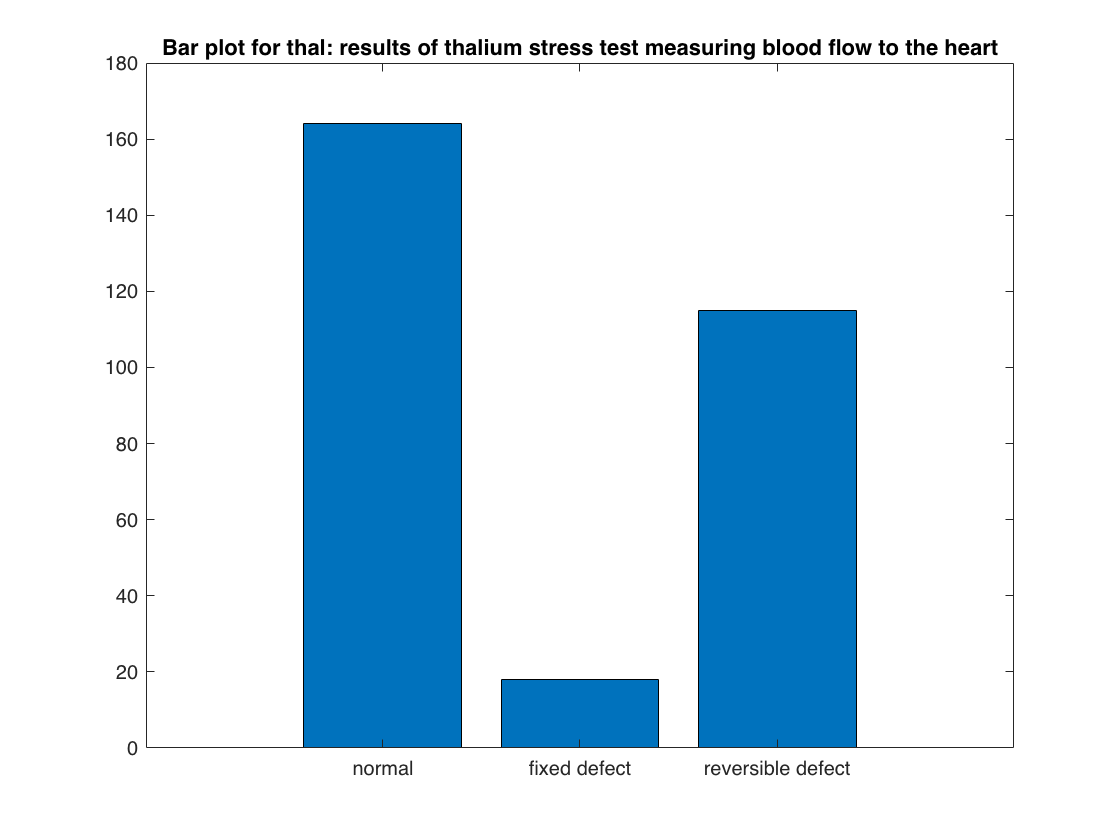

bar([139,137,21]) % set the count of slope to bar plot
title("Count of ecg slope") % set title
xticklabels(["upsloping" ,"flat","downsloping"]) % set x label of the class

Ecg result are mostly upslopping and flat.

summary(dataset.thal) % set count of the thal variable

     0      174 
     1       65 
     2       38 
     3       20 


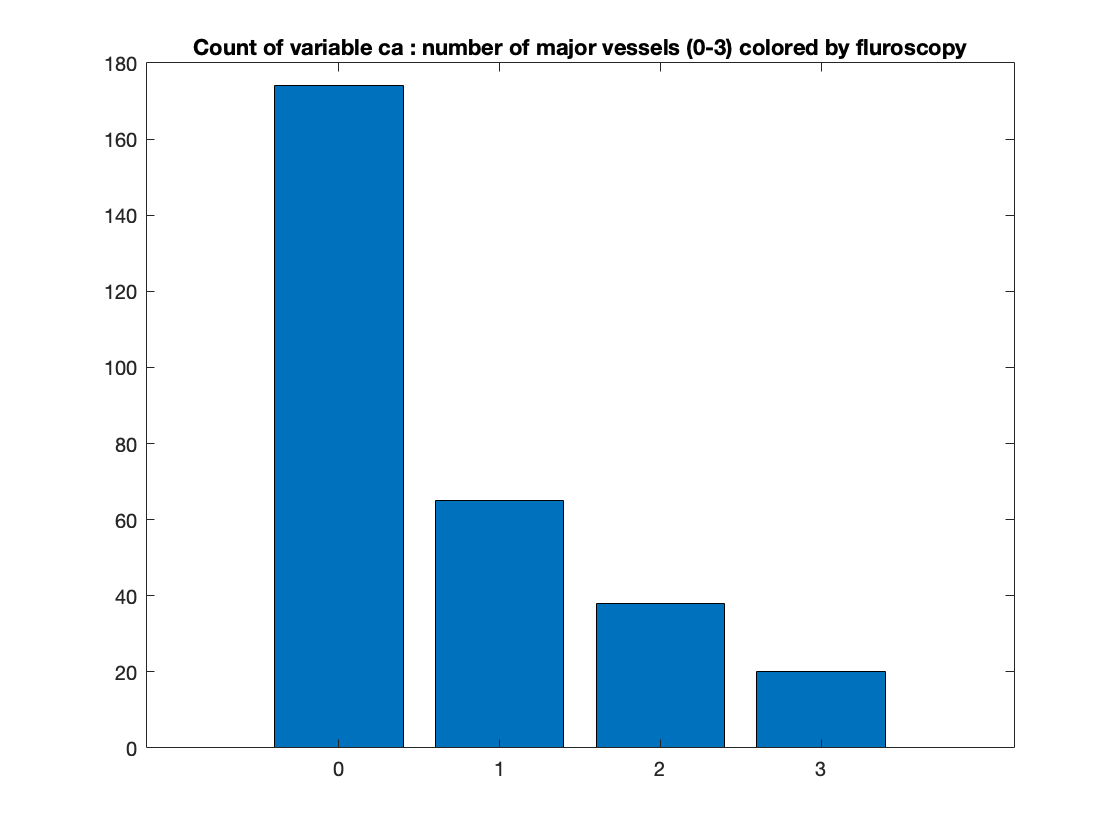

bar([164,18,115]) % place count argument to bar function to plot the bar
title("Bar plot for thal: results of thalium stress test measuring blood flow to the heart") % set title
xticklabels(["normal" ,"fixed defect","reversible defect"]) % set x label for the define class of thal variable

Majority of the thal test is normal with the 2nd most being reversible defect.

summary(dataset.ca) % get count of ca variable
bar([0,1,2,3],[174,65,38,20]) % this time i set the x labels into the barplot since class is in integer form
% only, i also added the count of ca variable as the other input to plot the bar plot
title("Count of variable ca : number of major vessels (0-3) colored by fluroscopy") % set title

The number of major vessels are likely not to be colored than colored at all.

## Splitting the dataset into training and test set to perform the 2 Machine learning algorithims: 

% Split the dataset into training set and testing set randonly : 80% for the training set and
% 20% of the test set:

dataTrain = 238×14 table
      age      sex    cp    trestbps       chol      fbs    restecg    thalach     exang     oldpeak     slope    ca    thal    target
    _______    ___    __    _________    ________    ___    _______    ________    _____    _________    _____    __    ____    ______

     0.9346     1     1       0.74912    -0.27598     1        2       0.017465      0         1.0672      3      0      6        0   
     1.3766     1     4        1.5936      0.7433     0        2        -1.8133      1       

data = dataset;
rng(32) % set a seed for reproducibility 
% Cross validation (train: 80%, test: 20%) % Separate to training and test data

ans =     0.8013    0.1987


cv = cvpartition(size(data,1),'HoldOut',0.20);
dataTrain = data(cv.training,:)  % training data allowed to be seen 
dataTest = data(cv.test,:); % Semicolon inserted for the test data as would diminish authenticity of result for our 2 machine learning algorithms.  
% To confirm that the training and dest split is a 80%:20% split roughly : 
[ height(dataTrain)/height(data),  height(dataTest)/height(data)]

### (Explaing the positive and negative  classes for both  model  to make it easier  for myself  to  evaluate the models)

I defined the class of the case to be :

Positive case : When the patient does not have heart disease (class/label=0) 

Negative case : When the patient does have heart disease (class/label=1) 

And then i defined the True positive (TP) , True Negative (TN) , False Positive (FP) ,  False Negative (FN)  which also are the elements  that make up  the confusion chart. Which i will plot to compare the two machine learning algorithms.

True Positive (TP) : When the class of the predicted (using the model) is  equal to the class of the target variable (in the dataset) [true] and the outcome is positive.  In my case this is when the label/class is 0  (No heart disease)

True Negative (TN) : When the class of the predicted (using the model)  is  equal to the class of the target variable (in the dataset) [true] and the outcome is negative. In my case this is when the label/class is 1 (heart disease).

False Positive (FP) :  When the class of the predicted (using the model)  is not equal to the class of the target variable (in the dataset) [False] and the outcome is negative. In my case this is when the label/class is 0 (No heart disease). Also known as Type 1 error

 False Negative (FN) :  When the class of the predicted (using the model)  is not equal to the class of the target variable (in the dataset) [False] and the outcome is negative. In my case this is when the label/class is 1 (Heart disease). Also known as type 2 error.

I am going to calculate the perfomance metrics  :   Accuracy, Loss, Presicion, Recall ,  Specificity , F1score using TP,TN,FP and FN: 

Accuracy: Mesuares how accurate out model is by calculating the number of correct labels predicted  by the model divided by the sum of the label samples in the dataset. 

Loss (error) : how many labels are wrong divided by the sum of samples in the dataset or (1 - accuracy)

Precision: Precision is the ratio between the True Positives and all the Positives. measure of patients that we correctly identify no  heart disease out of all the  patients actually not having it.

Recall [also known as sensitivity and true positive rate] : measure how accurate the model is at identifing true  positive, in my case patients that don't have heart disease (label =0). 

Specificity: measure how accurate the model is at identifing  true  negative, patients that have heart disease (label = 1).

F1-score: is the Harmonic mean of the Precision and Recall. 

"Understanding Accuracy made us realize, we need a tradeoff between Precision and Recall. We first need to decide which is more important for our classification problem.

For example, for our dataset, we can consider that achieving a high recall is more important than getting a high precision – we would like to detect as many heart patients as possible."   

In this case, we want a high recall and precision becauae we want to avoid patients given a false diagnosis/classification. where they have no heart disease (class=0) but were classifed as heart disease (class = 1) and vise versa. So recall and precision are equaly important in our model.

I will compare the machine learning algorithms by plotting bar plot of the perfomance metrics and also plot the ROC curve and calculate AUC.

[https://www.analyticsvidhya.com/blog/2020/09/precision-recall-machine-learning/](https://www.analyticsvidhya.com/blog/2020/09/precision-recall-machine-learning/)   

[https://cms.uni-konstanz.de/fileadmin/archive/informatik-saupe/fileadmin/informatik/ag-saupe/MLSS_17/mlss-lec8.pdf](https://cms.uni-konstanz.de/fileadmin/archive/informatik-saupe/fileadmin/informatik/ag-saupe/MLSS_17/mlss-lec8.pdf)  

## Machine learning algorithm : Logistic Regression (LR)

Logistic regression predicts the target variable (Y)  which can take two values ( heart  disease = 1 or no heart disease = 0) using the other features of my dataset (X).  Through fitting the training set  using it to learn and predict the classified values for the test set.

## Baseline Model for logistic regression (LR):

% I fitted the model using a classication linear model in-built function then i transfromed it to 
% classification logistic regression model using the name pair values argument where the transformation 
% occurs due to the sigmoid/logit functions, this is done via the 'learner' 'logitistic' name pair values.

% I used the 'ScoreTransform' 'logit name' pair values, the score represents the confidence of a classification 
% into a class, higher, being more confidence. I converted the score to use the logit function in order to get 
% the probability estimate of each class to predict the class being 1 (heart diseas) or 0 (no heart disease).

% But before i fitted the model i got an estimated fit of the model by perfoming K-fold crossvalidation(K=10) 


10 fold cross valdiation loss for baseline logistic regression model = 0.163866

% by getting an estimated loss, this is done by additional name pair value input : 'crossval','on':
rng(32) % set the same  seed for reproducibility of result.
mdlLR_CV = fitclinear(dataTrain,"target",'Learner','logistic','ScoreTransform','logit','crossval','on');
fprintf('\n10 fold cross valdiation loss for baseline logistic regression model = %f',kfoldLoss(mdlLR_CV)) % Gennralisation error
% Fit training set for logistic regression:

Training error for the baseline logistic regression model = 0.121849 

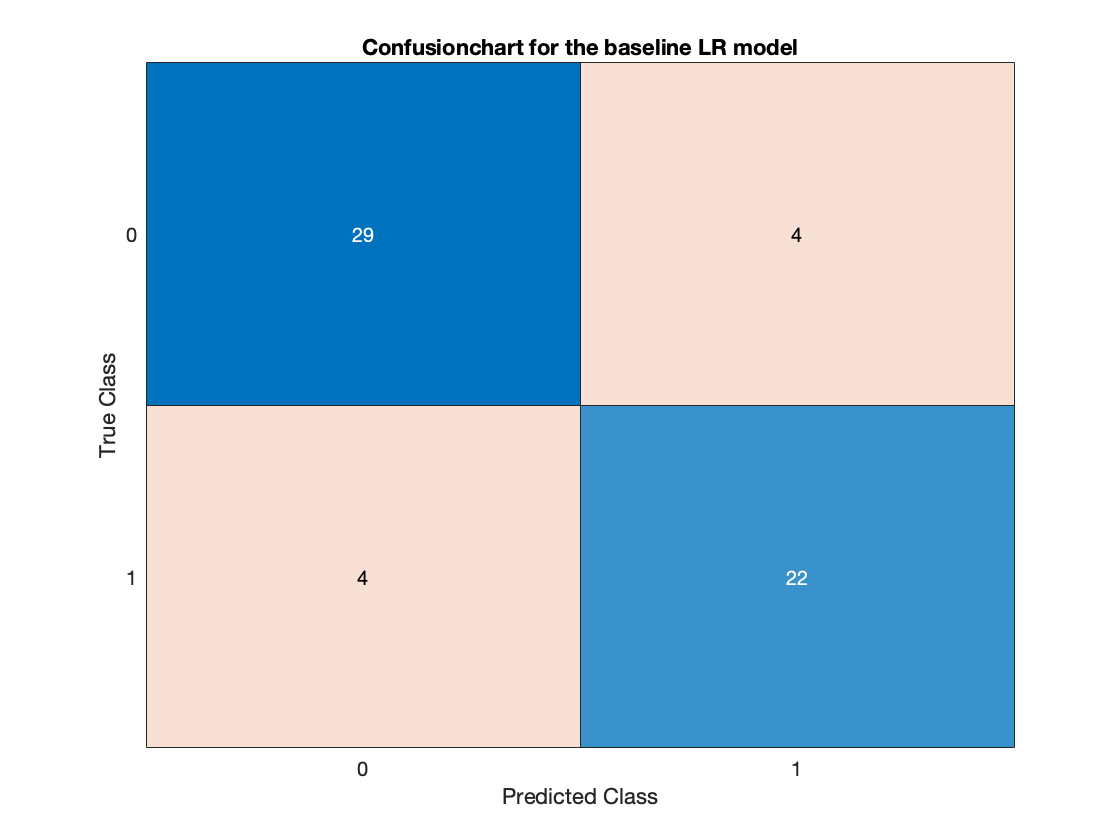

rng(32)  % set the same  seed for reproducibility of result.
% the 1st output is mdlLR: model for logistic regression and 2nd output is fitinfo: the info of fitted model 
mdlLR = fitclinear(dataTrain,"target",'Learner','logistic','ScoreTransform','logit');
fprintf("Training error for the baseline logistic regression model = %f ", loss(mdlLR,dataTrain))
% Using the predict function to predict the Class (1 or 0) on the test set (dataTest)
% the 1st output (Labels_LR) is the predicted class and the 2nd output (Score_LR) is the score 
% (posterior probability used to predict the class) where the 1st column of score is the confidence of it being
% class 0 (No heart disease) and 2nd column of score is the confidence of
% it being class 1 (Heart disease) from the column prespective of which class is positive.
[Labels_LR,Score_LR] = predict(mdlLR,dataTest);

% Plot the confusion chart which is a chart of the confusion matrix [2x2] which contains True positive (TP), 
% False positive (FP) , False Negative (FN) and True negative (TN) cases for the class of response variable target.
confusionchart(dataTest.target,Labels_LR); 
title("Confusionchart for the baseline LR model")
% Calculating the true positive (TP) , False positive (FP), True Negative (TN) , False Negative (FN). 
% This will also help verify  that our confusionchart is right

% True positive (TP) calculated by applying condition prediction is correct & positive class/label is 0 (No heart disease)

True positive (TP) for the baseline LR model = 29

% then sum to get the total amount that this condition was met.
TP_LR = sum(Labels_LR == dataTest.target & Labels_LR=="0");
fprintf("True positive (TP) for the baseline LR model = %d", TP_LR) 
% True negative (TN) calculated by applying condition prediction is correct & negative class/label is 1 

True negative (TN) for the baseline LR model = 22

% (Heart disease) then sum to get total amount that condition was met.
TN_LR = sum(Labels_LR == dataTest.target & Labels_LR=="1");
 fprintf("True negative (TN) for the baseline LR model = %d",TN_LR)
%  False positive (FP) calculated by applying condition prediction is incorrect and positive class/label is 0    

False positive (FP) for the baseline LR model =  4

% (No heart disease) then sum to get the total amount that this condition was met.
FP_LR = sum(Labels_LR ~= dataTest.target & Labels_LR=="0");
fprintf("False positive (FP) for the baseline LR model =  %d",sum(Labels_LR ~= dataTest.target & Labels_LR=="0"))
%  False negative (FN) calculated by applying condition prediction is incorrect and negative class/label is 1    

False negative (FN) for the baseline LR model =  4

% (heart disease) then sum to get the total amount that this condition was met.
FN_LR = sum(Labels_LR ~= dataTest.target & Labels_LR=="1");
fprintf("False negative (FN) for the baseline LR model =  %d",FN_LR)
% Using TP ,FP,FP ,FN, i calculated the metrics accuracy,loss,presicion,recall,specificity,f1score of our model:

Accuracy for the baseline LR model =  0.864407

%accuracy = (TP + TN)/(TP+TN+FP+FN)
accuracy_LR = (TP_LR + TN_LR)/(TP_LR + TN_LR + FP_LR + FN_LR);
fprintf("Accuracy for the baseline LR model =  %f", accuracy_LR )

Loss (error) for the baseline LR model =  0.135593

% loss (error) : loss = 1 - accuracy
loss_LR = 1 - accuracy_LR ;
fprintf("Loss (error) for the baseline LR model =  %f", loss_LR)

Precision for the baseline LR model =  0.878788

% Precision: precision_LR = TP/(TP+FP)
Precision_LR = (TP_LR)/(TP_LR  + FP_LR);
fprintf("Precision for the baseline LR model =  %f", Precision_LR)

Recall for the baseline LR model =  0.878788

% recall: recall_LR = TP/(TP + FN)
recall_LR = (TP_LR)/(TP_LR  + FN_LR);
fprintf("Recall for the baseline LR model =  %f", recall_LR)

Specificity for the baseline LR model =  0.846154

%Specificity: Specificity = TN/(TN+FP)
Specificity_LR = (TN_LR)/(TN_LR  + FP_LR);
fprintf("Specificity for the baseline LR model =  %f", Specificity_LR )

F1 Score for the baseline LR model = 0.878788

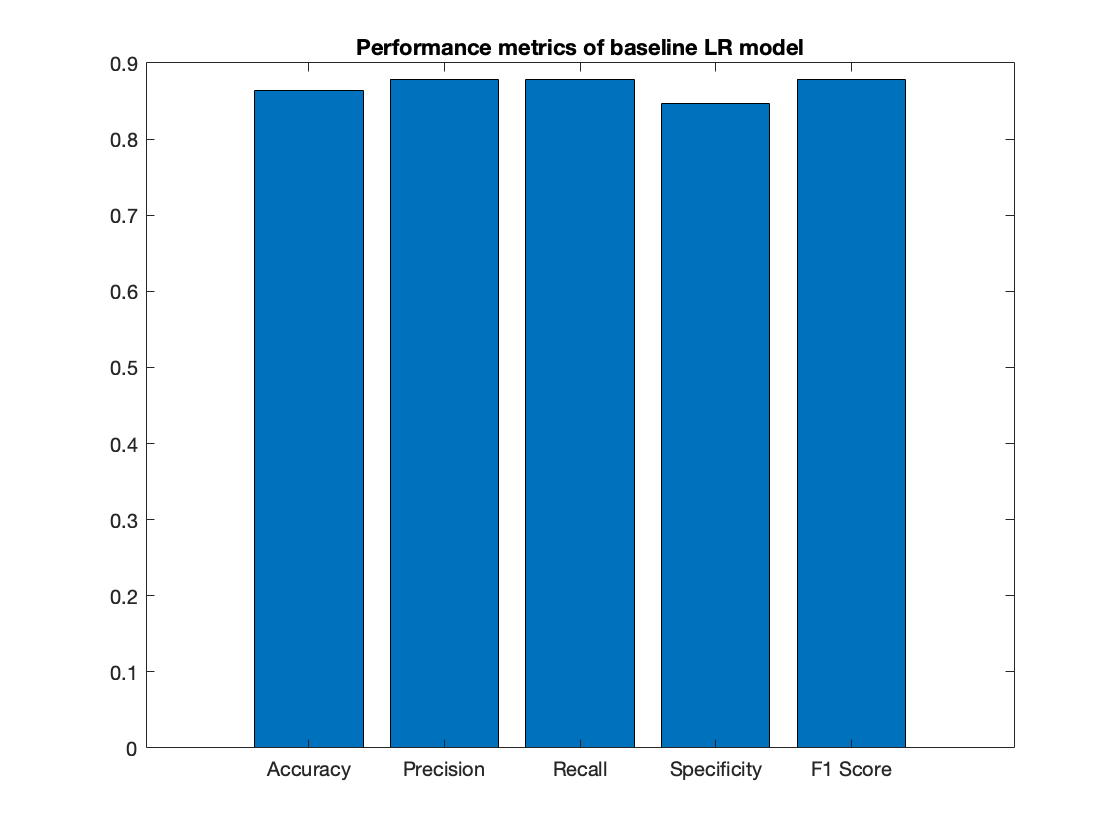

 %F1-score: f1score =  2 * (precision* recall)/(precision + recall) 
 F1Score_LR = 2*(Precision_LR*recall_LR)/(Precision_LR + recall_LR);
 fprintf("F1 Score for the baseline LR model = %f",F1Score_LR)
% Plotting the bar plot of the perfomance metrics: 

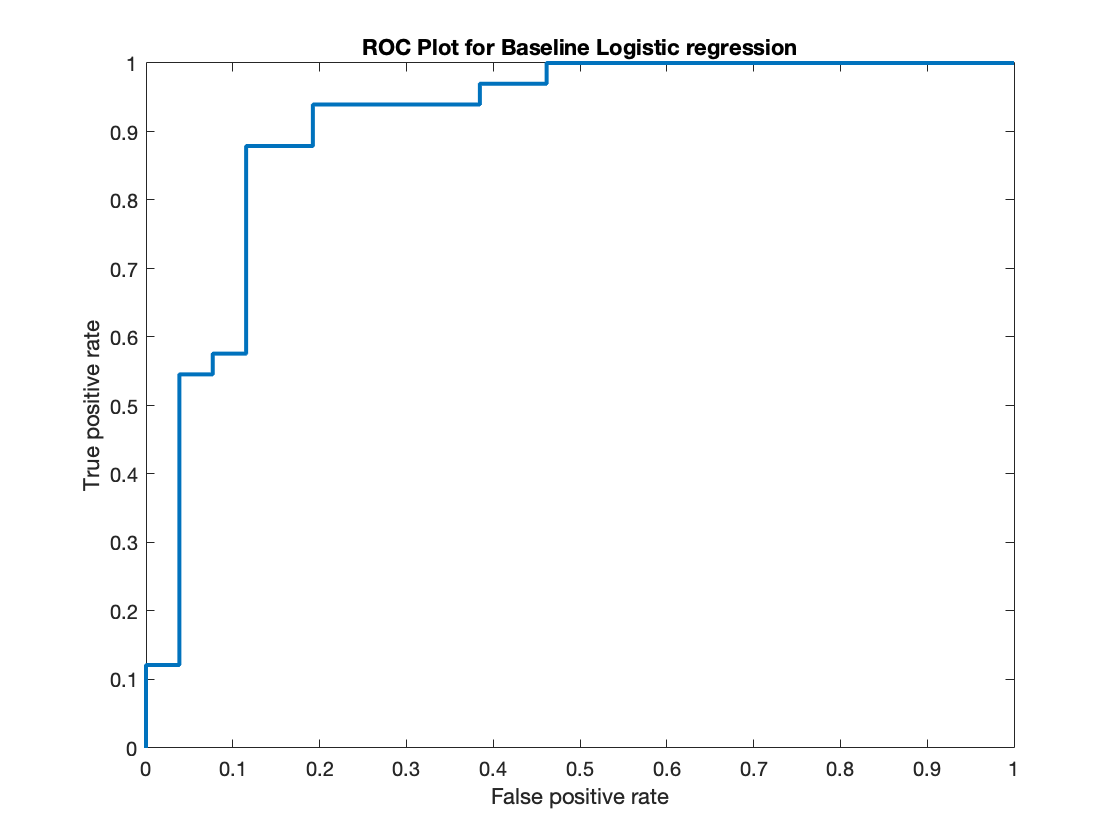

 bar([accuracy_LR,Precision_LR,recall_LR,Specificity_LR,F1Score_LR])
 title("Performance metrics of baseline LR model")
 xticklabels(["Accuracy","Precision","Recall","Specificity","F1 Score"])
% I am plotting the ROC curve using the perfcurve function , where the  first input is the observations we
% want to predict, the 2nd input is the score : probability confidence that the class is  positive,select 1st 
% column for score is if you want the positive class to be 0 (No heart disease) and for 2nd column if you 
% want the positive class to be 1 (Heart disease) in my case i want it to be class=0 (No heart disease), 
% as confirmed by the positive class label.

% Outputs i get from the perfcurve is the False positive rate (FPR) ,true positive rate (TPR), the threshold 
% is empty(~) as  it  default is  0.5 to classify class , as last output is AUC (Area under curve)

% Then use plot() function to plot ROC curve where FPR on x-axis and TPR is on y-axis
[FPRLR,TPRLR,~,AUC_LR]=perfcurve(categorical(dataTest.target),abs(Score_LR(:,1)),categorical("0"));
plot(FPRLR,TPRLR,"LineWidth",2)

xlabel('False positive rate')
ylabel('True positive rate')

AUC (Baseline model:LR) = 0.909

title('ROC Plot for Baseline Logistic regression') 
% print out the value for AUC: 
fprintf("AUC (Baseline model:LR) = %.3f",AUC_LR) 

### Applying Hyperparameter tuning to optimise the Logistic regression (LR) model

|=====================================================================================================|
| Iter | Eval   | Objective   | Objective   | BestSoFar   | BestSoFar   |       Lambda | Regularizati-|
|      | result |             | runtime     | (observed)  | (estim.)    |              | on           |
|=====================================================================================================|
|    1 | Best   |     0.16807 |     0.17117 |     0.16807 |     0.16807 |   2.3023e-06 |        ridge |
|    2 | Accept |     0.16807 |     0.18222 |     0.16807 |     0.16807 |   6.0128e-05 |        lasso |
|    3 | Accept |     0.46639 |      0.1404 |     0.16807 |     0.18225 |       1.2711 |        lasso |
|    4 | Best   |     0.15126 |     0.12308 |     0.15126 |     0.15135 |     0.010698 |        ridge |
|    5 | Accept |     0.15546 |     0.14212 |     0.15126 |     0.15127 |   0.00088529 |        ridge |
|    6 | Accept |     0.16807 |     0.14084 |     0.15126 |     

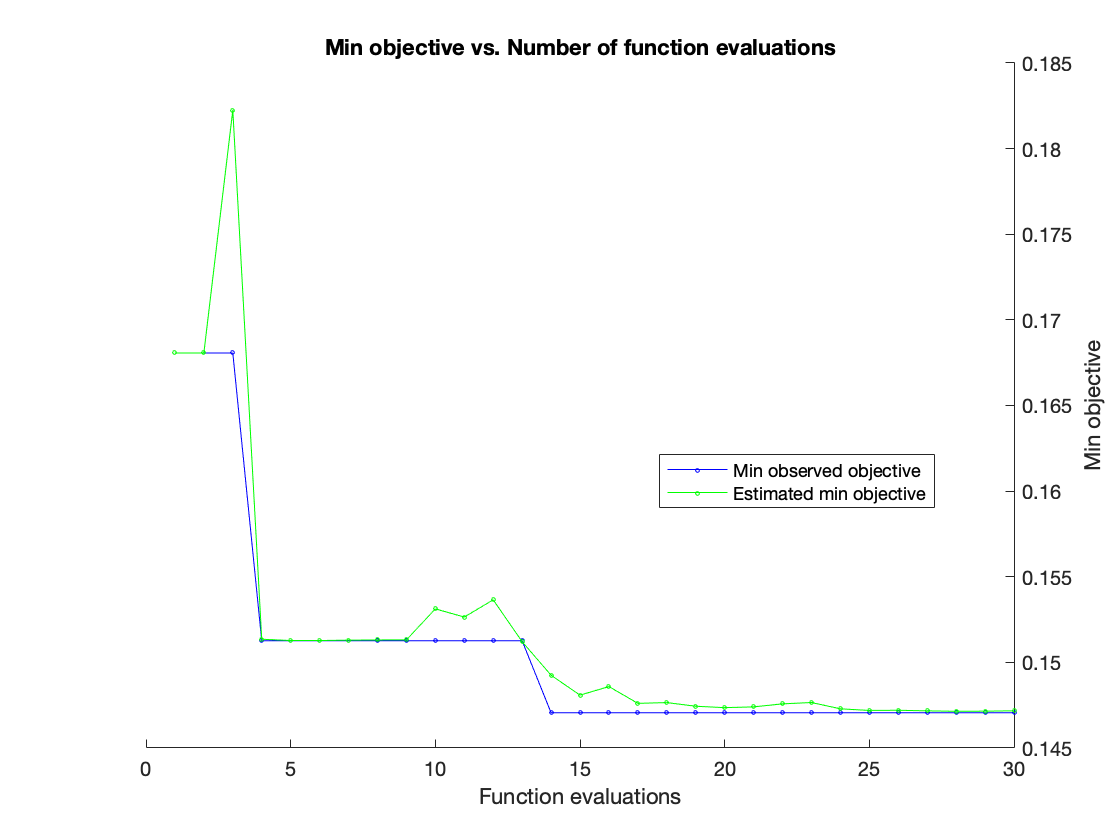

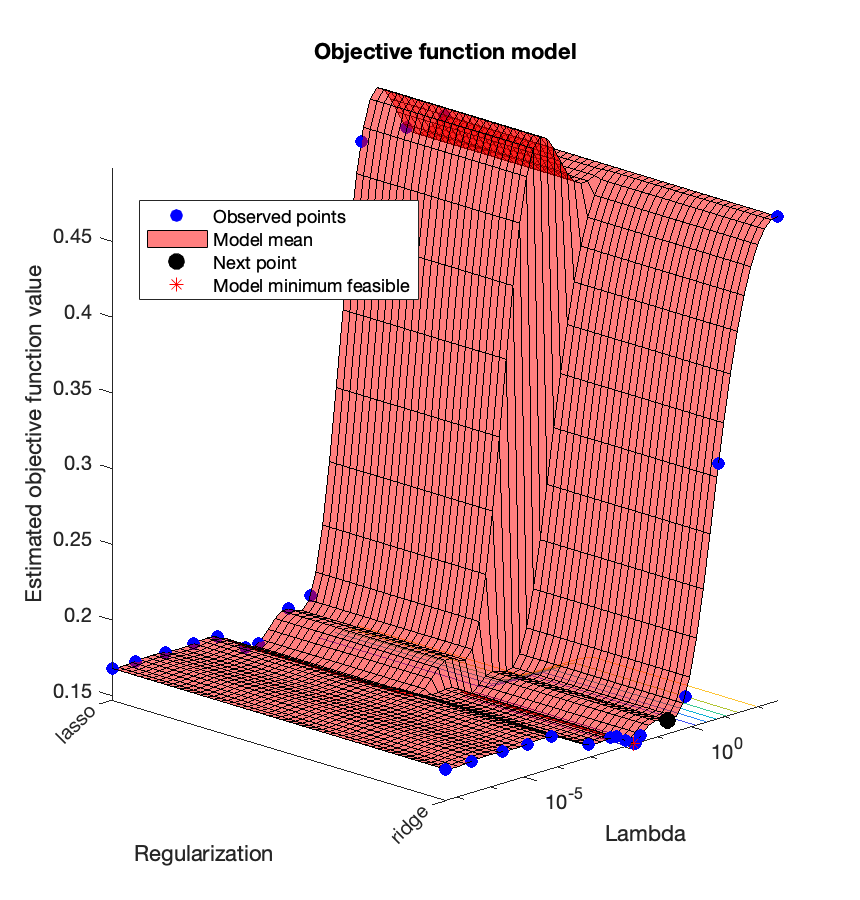


__________________________________________________________
Optimization completed.
MaxObjectiveEvaluations of 30 reached.
Total function evaluations: 30
Total elapsed time: 42.6308 seconds
Total objective function evaluation time: 3.2978

Best observed feasible point:
     Lambda     Regularization
    ________    ______________

    0.020753        ridge     

Observed objective function value = 0.14706
Estimated objective function value = 0.14729
Function evaluation time = 0.094227

Best estimated feasible point (according to models):
     Lambda     Regularization
    ________    ______________

    0.019412        ridge     

Estimated objective function value = 0.14717
Estimated function evaluation time = 0.095326



mdlLR_HPT =   ClassificationLinear
    PredictorNames: {'age'  'sex'  'cp'  'trestbps'  'chol'  'fbs'  'restecg'  'thalach'  'exang'  'oldpeak'  'slope'  'ca'  'thal'}
      ResponseName: 'target'
        ClassNames: [0    1]
    ScoreTransform: 'logit'
              Beta: [27×1 double]
              Bias: -0.2074
            Lambda: 0.0194
           Learner: 'logistic'


  Properties, Methods


% Applying Hyperparameter tuning to my logistical regression model now to get a optimized model.
 % This is done by selecting the hypoparemters lambda and regression type to get a best fitted optimal model 

% Lamba penalizes the function to prevent it from overfitting 
 rng(32) % set the same seed for reproducibility
 mdlLR_HPT = fitclinear(dataTrain,"target",'Learner','logistic','ScoreTransform','logit',"OptimizeHyperparameters",{'Lambda' 'Regularization'})

## **Optimised Model for Logistic Regression  (LR):**

% Hyperparemeter optimised model : sub the parameter values lambda and regularisation type
% Cross validate to get Gennralisation error
% if statement is added in  case hyperparameter parameter regularization regression type optimal solution 
% is Lasso regression and the fitted model to calculate the generalisation error can be corrected instantly.
rng(32) % set seed for reproducibility 
if mdlLR_HPT.Regularization == 'ridge (L2)'
    mdlLR_HP_CV  = fitclinear(dataTrain,"target",'Learner','logistic','ScoreTransform','logit','Lambda',mdlLR_HPT.Lambda,'Regularization','ridge','crossval','on'); % ridge if ridge
else 


10 fold cross valdiation loss for optimised logistic regression model = 0.142857

    mdlLR_HP_CV  = fitclinear(dataTrain,"target",'Learner','logistic','ScoreTransform','logit','Lambda',mdlLR_HPT.Lambda,'Regularization','lasso','crossval','on'); % lasso  if not ridge
end    
fprintf('\n10 fold cross valdiation loss for optimised logistic regression model = %f',kfoldLoss(mdlLR_HP_CV)) % Gennralisation error
rng(32)% Set seed for reproducible result 
% need to replace incase regularization argument changes to lasso if it is not ridge (for name pair values)
% this is where the if statemennt comes in, where we can change the fiited model conditional on
% the Regularization argument is optimal  in the hyperparameter tuning stage (previous stage):
if mdlLR_HPT.Regularization == 'ridge (L2)'
    mdlLR_HP = fitclinear(dataTrain,"target",'Learner','logistic','ScoreTransform','logit','Lambda',mdlLR_HPT.Lambda,'Regularization','ridge') % ridge if ridge

mdlLR_HP =   ClassificationLinear
    PredictorNames: {'age'  'sex'  'cp'  'trestbps'  'chol'  'fbs'  'restecg'  'thalach'  'exang'  'oldpeak'  'slope'  'ca'  'thal'}
      ResponseName: 'target'
        ClassNames: [0    1]
    ScoreTransform: 'logit'
              Beta: [27×1 double]
              Bias: -0.2074
            Lambda: 0.0194
           Learner: 'logistic'


  Properties, Methods


else 

Training error for the optimal logistic regression model = 0.126050 

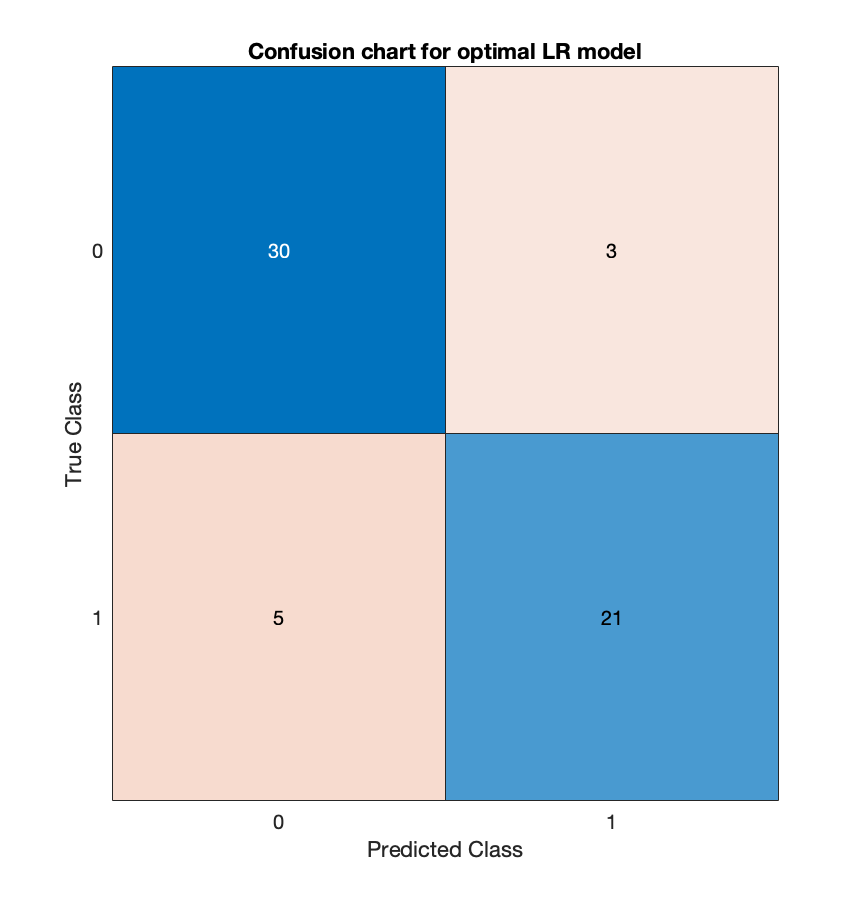

    mdlLR_HP = fitclinear(dataTrain,"target",'Learner','logistic','ScoreTransform','logit','Lambda',mdlLR_HPT.Lambda,'Regularization','lasso') % lasso  if not ridge
end    
 fprintf("Training error for the optimal logistic regression model = %f ", loss(mdlLR_HP,dataTrain))
% Predicting the labels of my testset: 
 [Labels_LR_HP,Scores_LR_HP] = predict(mdlLR_HP,dataTest);

% Plotting confusionchart to measure how well the model did:  
confusionchart(dataTest.target,Labels_LR_HP) 
title("Confusion chart for optimal LR model")
% Calculating the true positive (TP) , False positive (FP), True Negative (TN) , False Negative (FN). 
% This will also help verify  that our confusionchart is right

True positive (TP) for the optimal LR model = 30

TP_LR_HP = sum(Labels_LR_HP == dataTest.target & Labels_LR_HP=="0"); %  True positive
fprintf("True positive (TP) for the optimal LR model = %d", TP_LR_HP) 

True negative (TN) for the optimal LR model = 21

TN_LR_HP = sum(Labels_LR_HP == dataTest.target & Labels_LR_HP=="1"); % True negative
fprintf("True negative (TN) for the optimal LR model = %d",TN_LR_HP)

False positive (FP) for the optimal LR model =  4

FP_LR_HP = sum(Labels_LR_HP ~= dataTest.target & Labels_LR_HP=="0"); % False positive
fprintf("False positive (FP) for the optimal LR model =  %d",sum(Labels_LR ~= dataTest.target & Labels_LR=="0"))

False negative (FN) for the optimal LR model =  3

FN_LR_HP = sum(Labels_LR_HP ~= dataTest.target & Labels_LR_HP=="1"); % False negative
fprintf("False negative (FN) for the optimal LR model =  %d",FN_LR_HP)
% Using TP ,FP,FP ,FN, i calculated the metrics accuracy,loss,presicion,recall,specificity,f1score of our model:

Accuracy for the optimal LR model =  0.864407

accuracy_LR_HP = (TP_LR_HP + TN_LR_HP)/(TP_LR_HP+TN_LR_HP+FP_LR_HP+FN_LR_HP); % accuracy
fprintf("Accuracy for the optimal LR model =  %f", accuracy_LR_HP )

Loss (error) for the optimal LR model =  0.135593

loss_LR_HP = 1 - accuracy_LR_HP; % loss
fprintf("Loss (error) for the optimal LR model =  %f", loss_LR_HP)

Precision for the optimal LR model =  0.857143

Precision_LR_HP = TP_LR_HP/(TP_LR_HP+FP_LR_HP); % precision
fprintf("Precision for the optimal LR model =  %f", Precision_LR_HP)

Recall for the optimal LR model =  0.909091

recall_LR_HP = TP_LR_HP/(TP_LR_HP + FN_LR_HP); % recall
fprintf("Recall for the optimal LR model =  %f", recall_LR_HP)

Specificity for the optimal LR model =  0.807692

Specificity_LR_HP = TN_LR_HP/(TN_LR_HP+FP_LR_HP); % specificity
fprintf("Specificity for the optimal LR model =  %f", Specificity_LR_HP )

F1 Score for the optimal LR model = 0.882353

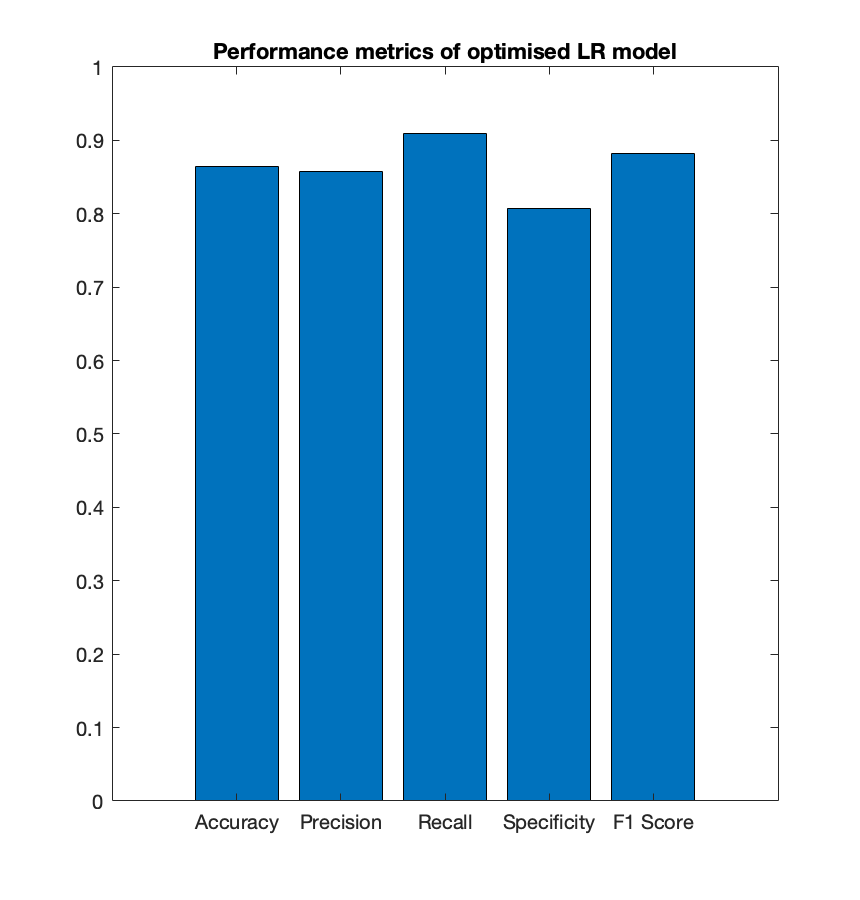

F1Score_LR_HP =  2 * (Precision_LR_HP * recall_LR_HP)/(Precision_LR_HP + recall_LR_HP); % F1 score
 fprintf("F1 Score for the optimal LR model = %f",F1Score_LR_HP)
 % Plot the performance metrics of the model: 
bar([accuracy_LR_HP,Precision_LR_HP,recall_LR_HP,Specificity_LR_HP,F1Score_LR_HP])

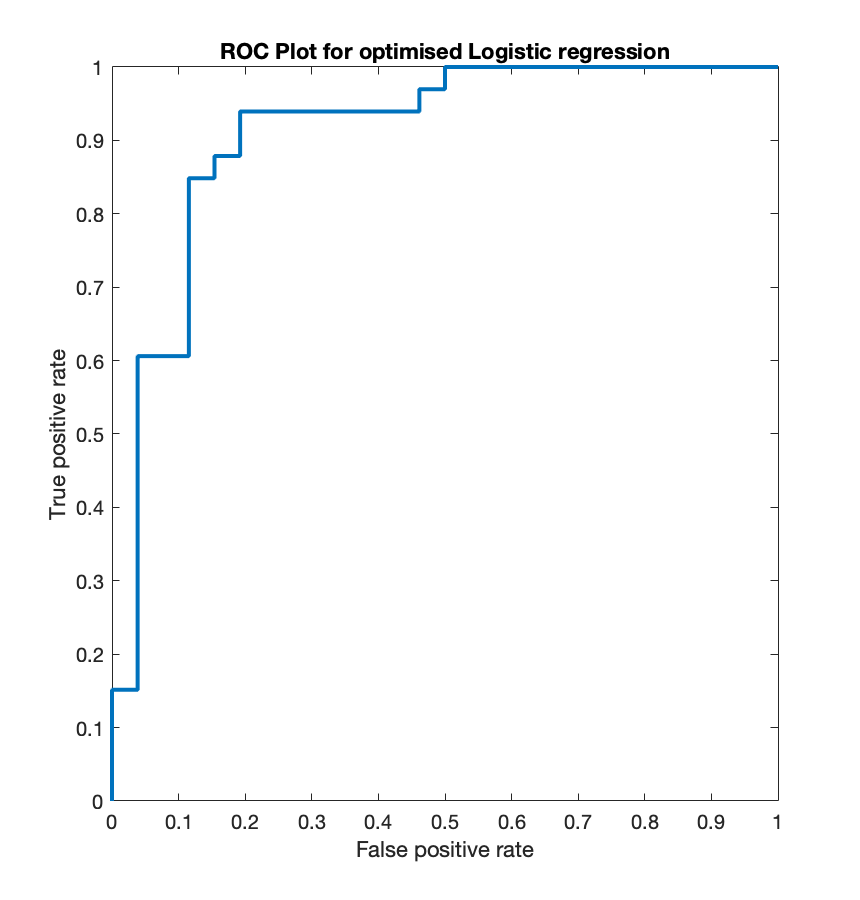

title("Performance metrics of optimised LR model")
xticklabels(["Accuracy","Precision","Recall","Specificity","F1 Score"])
 % Outputs i get from the perfcurve is the False positive rate (FPR) ,true positive rate (TPR), the threshold 
% is empty(~) as  it  default is  0.5 to classify class , as last output is AUC (Area under curve)
% Then use plot() function to plot ROC curve where FPR on x-axis and TPR is on y-axis
[FPRLR_HP,TPRLR_HP,~,AUC_LRHP]=perfcurve(categorical(dataTest.target),abs(Scores_LR_HP(:,1)),categorical("0"));
plot(FPRLR_HP,TPRLR_HP,"LineWidth",2)
xlabel('False positive rate')

ylabel('True positive rate')

AUC (Optimised LR) = 0.909

title('ROC Plot for optimised Logistic regression') 
fprintf('AUC (Optimised LR) = %.3f',AUC_LRHP)
 % Optimised model is just the repeated steps of the baseline model.

## Machine learning algorithm : Naive Bayes

Naive bayes is another classification model used to classify response  variable, by calculating the prior probability and likelihood probability to fit a posterior probability for each observation , and use the posterior probability  to predict the class is heart disease (=1) or not heart disease (=0)

### Naive Bayes (NB)  Model ( Baseline)

% before i fitted the model i got an estimated fit of the model by perfoming K-fold crossvalidation(K=10) 
% by getting an estimated loss, this is done by additional name pair value input : 'crossval','on' into the 
% inbuilt function fitcnb, i also assume Guassian distribution for the model:
rng(32) % Set seed for reproducible result 
mdlNBCV = fitcnb(dataTrain,"target","crossval","on","KFold",10);
% using the crossvalidation function to cross validate my data into K fold which in this case is 10 on the training set to estimate the loss of the model as well as how model fits:


10 fold cross valdiation loss for baseline NB model = 0.172269

fprintf('\n10 fold cross valdiation loss for baseline NB model = %f',kfoldLoss(mdlNBCV)) % Gennralisation error
% Fit the naive bayes model with the training data via fitcn
% The default distribution is guassian
rng(32)  % Set seed for reproducible result

mdlNB =   ClassificationNaiveBayes
            PredictorNames: {'age'  'sex'  'cp'  'trestbps'  'chol'  'fbs'  'restecg'  'thalach'  'exang'  'oldpeak'  'slope'  'ca'  'thal'}
              ResponseName: 'target'
     CategoricalPredictors: [2 3 6 7 9 11 12 13]
                ClassNames: [0    1]
            ScoreTransform: 'none'
           NumObservations: 238
         DistributionNames: {'normal'  'mvmn'  'mvmn'  'normal'  'normal'  'mvmn'  'mvmn'  'normal'  'mvmn'  'normal'  'mvmn'  'mvmn'  'mvmn'}
    DistributionParameters: {2×13 cell}
         CategoricalLevels: {[]  [2×1 double]  [4×1 double]  []  []  [2×1 double]  [3×1 double]  []  [2×1 double]  []  [3×1 double]  [4×1 double]  [3×1 double]}


  Properties, Methods


mdlNB = fitcnb(dataTrain,"target")

Training error for the baseline NB model = 0.151261 

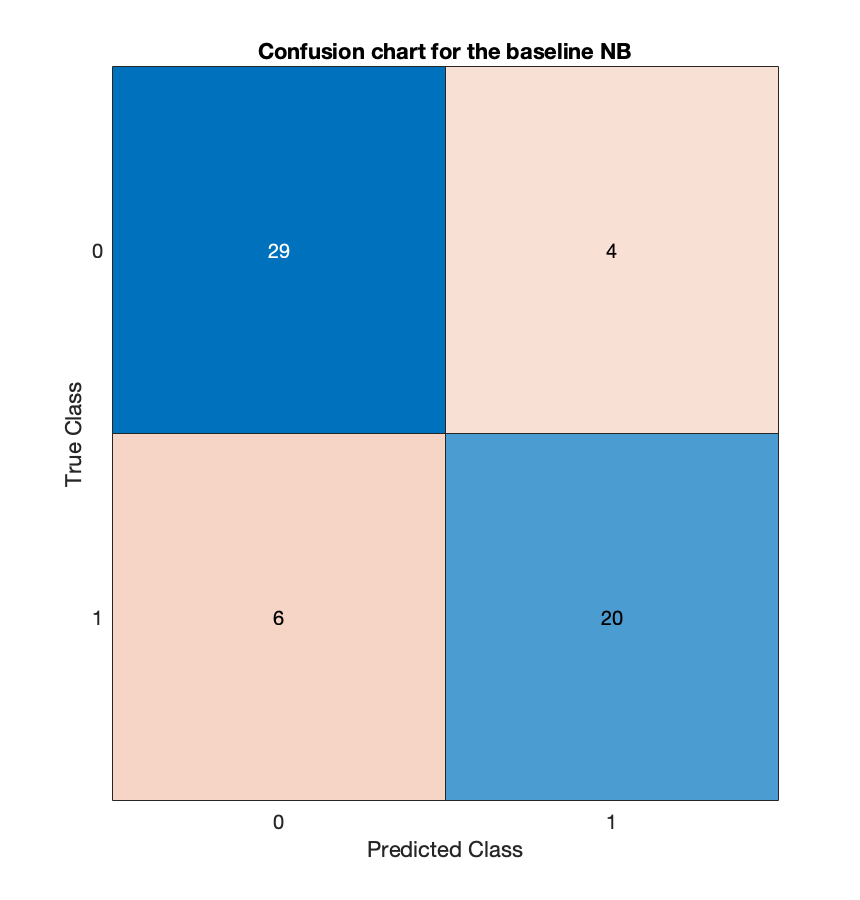

fprintf("Training error for the baseline NB model = %f ", loss(mdlNB,dataTrain)) % training error
% Predicting the "target" variable using predict function where 1st output gives the predicted class/label 
% and 2nd output gives the score confidence of each class
[LabelsNB,ScoresNB] = predict(mdlNB,dataTest);
% Confusion chart measures perfomance of the model on test data
confusionchart(dataTest.target,predict(mdlNB,dataTest)); 

title("Confusion chart for the baseline NB")
% Calculating the true positive (TP) , False positive (FP), True Negative (TN) , False
% Negative (FN), This will also help verify  that our confusionchart is right.
 TP_NB = sum(LabelsNB == dataTest.target & LabelsNB=="0") ; %True Positive (TP) 

True positive (TP) for the baseline NB model = 29

fprintf("True positive (TP) for the baseline NB model = %d", TP_NB) 
TN_NB = sum(LabelsNB == dataTest.target & LabelsNB=="1") ; %  True Negative (TN)

True negative (TN) for the baseline NB model = 20

fprintf("True negative (TN) for the baseline NB model = %d", TN_NB) 
FP_NB = sum(LabelsNB ~= dataTest.target & LabelsNB=="0") ;%  False positive (FP) 

False positive (FP) for the baseline NB model = 6

fprintf("False positive (FP) for the baseline NB model = %d", FP_NB) 
FN_NB = sum(LabelsNB ~= dataTest.target & LabelsNB=="1") ; %False negative (FN) 

False negative (FN) for the baseline NB model = 4

fprintf("False negative (FN) for the baseline NB model = %d", FN_NB) 
% From TP ,FP,FP , FN calculate the metrics accuracy,loss,presicion,recall,specificity,f1score of our model
Accuracy_NB = (TP_NB + TN_NB)/(TP_NB+TN_NB+FP_NB+FN_NB); % accuracy

Accuracy for the baseline NB model = 0.830508

fprintf("Accuracy for the baseline NB model = %f", Accuracy_NB) 
Loss_NB = 1 - Accuracy_NB ; % loss error

Loss (error) for the baseline NB model = 0.169492

fprintf("Loss (error) for the baseline NB model = %f", Loss_NB) 
Precision_NB = TP_NB/(TP_NB+FP_NB); % Precision

Precision for the baseline NB model = 0.828571

fprintf("Precision for the baseline NB model = %f", Precision_NB)
recall_NB = TP_NB/(TP_NB + FN_NB); % Recall

Recall for the baseline NB model = 0.878788

fprintf("Recall for the baseline NB model = %f", recall_NB)
Specificity_NB = TN_NB/(TN_NB+FP_NB); %Specificity 

Specificity for the baseline NB model = 0.769231

fprintf("Specificity for the baseline NB model = %f",Specificity_NB)
 %F1-score: 
F1Score_NB =  2 * (Precision_NB * recall_NB)/(Precision_NB + recall_NB) ;

F1Score for the baseline NB model = 0.852941

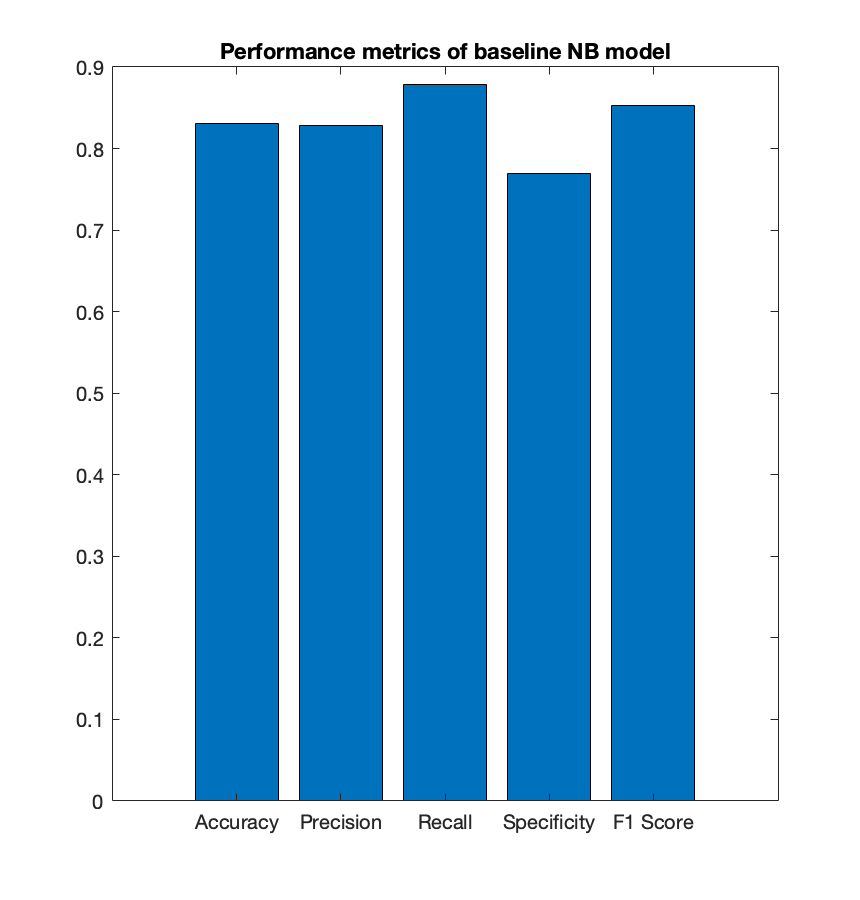

fprintf("F1Score for the baseline NB model = %f",F1Score_NB)
% Bar plot of the perfomance metrics: 
bar([Accuracy_NB,Precision_NB,recall_NB,Specificity_NB,F1Score_NB])
title("Performance metrics of baseline NB model")

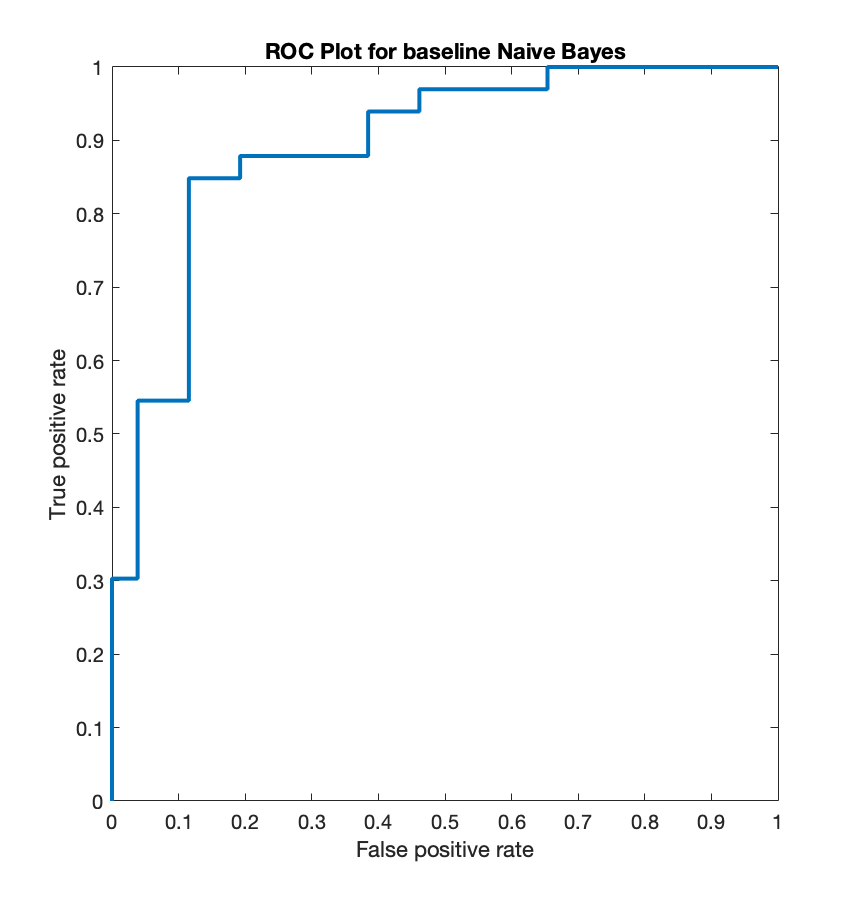

xticklabels(["Accuracy","Precision","Recall","Specificity","F1 Score"])
% Outputs i get from the perfcurve is the False positive rate (FPR) ,true positive rate (TPR), the threshold 
% is empty(~) as  it  default is  0.5 to classify class , as last output is AUC (Area under curve)
% Then use plot() function to plot ROC curve where FPR on x-axis and TPR is on y-axis
[FPRNB,TPRNB,~,AUC_NB]=perfcurve(categorical(dataTest.target),abs(ScoresNB(:,1)),categorical("0"));
plot(FPRNB,TPRNB,"LineWidth",2)
xlabel('False positive rate')
ylabel('True positive rate')

title('ROC Plot for baseline Naive Bayes') 

AUC (Baseline model: NB) = 0.893

fprintf('AUC (Baseline model: NB) = %.3f',AUC_NB)

## Applying Hyperparameter tuning to optimise the Naive Bayes (NB) model

Tuning my hypoparemter to see which distribution fits best for my model

|=====================================================================================================|
| Iter | Eval   | Objective   | Objective   | BestSoFar   | BestSoFar   | Distribution-|        Width |
|      | result |             | runtime     | (observed)  | (estim.)    | Names        |              |
|=====================================================================================================|
|    1 | Best   |     0.18067 |    0.078396 |     0.18067 |     0.18067 |       normal |            - |
|    2 | Accept |     0.18067 |    0.058856 |     0.18067 |     0.18067 |       normal |            - |
|    3 | Best   |     0.16807 |     0.22665 |     0.16807 |     0.16807 |       kernel |      0.73149 |
|    4 | Accept |     0.36555 |     0.17201 |     0.16807 |     0.16807 |       kernel |     0.011794 |
|    5 | Accept |     0.38655 |     0.16055 |     0.16807 |     0.16808 |       kernel |    0.0048091 |
|    6 | Accept |     0.19328 |     0.17845 |     0.16807 |     

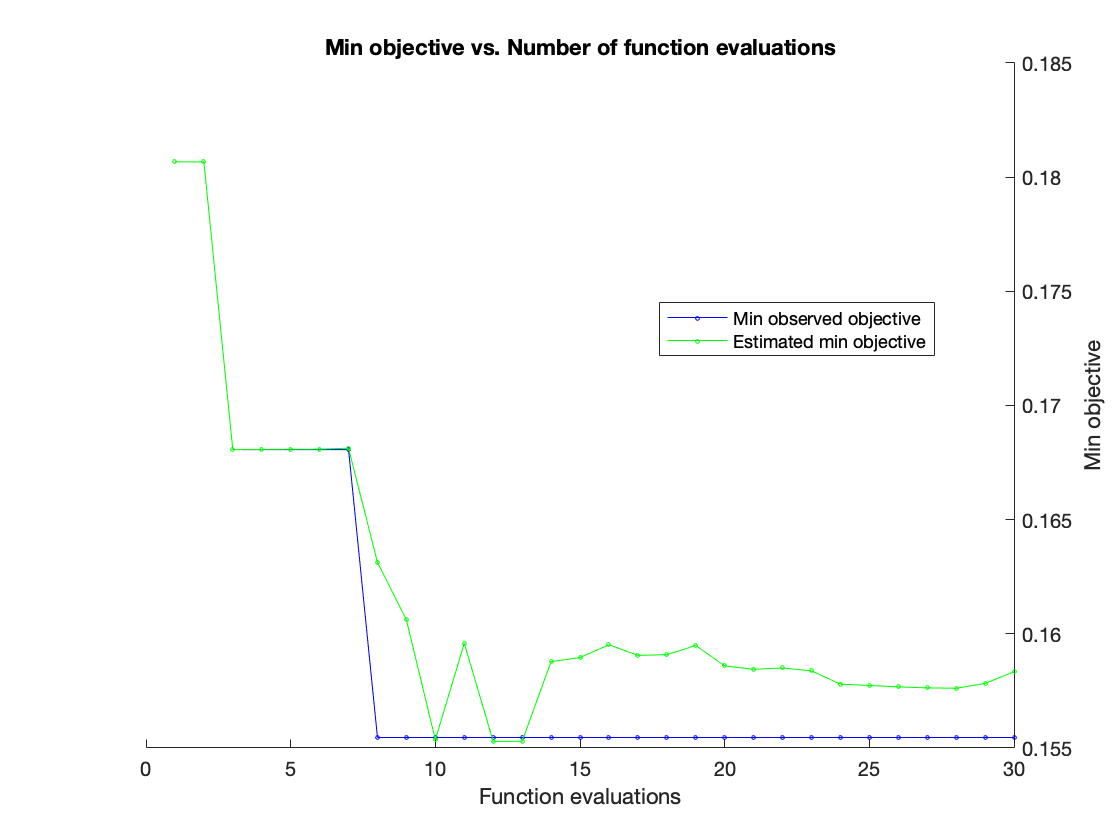

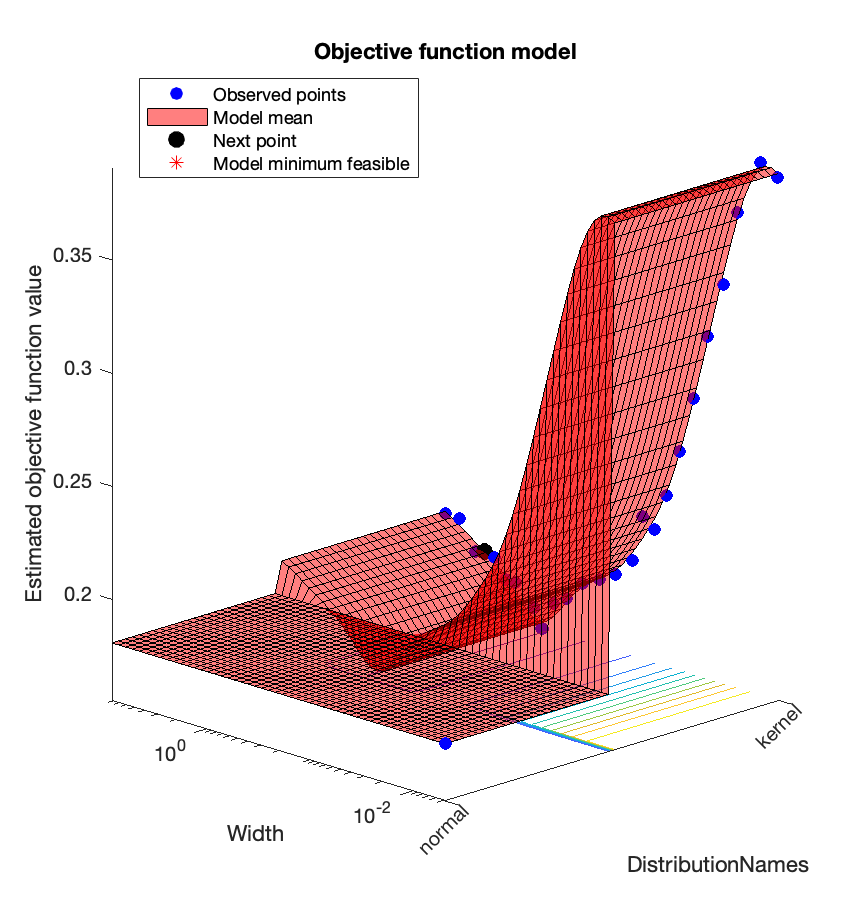


__________________________________________________________
Optimization completed.
MaxObjectiveEvaluations of 30 reached.
Total function evaluations: 30
Total elapsed time: 28.974 seconds
Total objective function evaluation time: 4.9325

Best observed feasible point:
    DistributionNames     Width 
    _________________    _______

         kernel          0.96092

Observed objective function value = 0.15546
Estimated objective function value = 0.15834
Function evaluation time = 0.16856

Best estimated feasible point (according to models):
    DistributionNames     Width 
    _________________    _______

         kernel          0.96092

Estimated objective function value = 0.15834
Estimated function evaluation time = 0.17077



mdlNB_HPT =   ClassificationNaiveBayes
                       PredictorNames: {'age'  'sex'  'cp'  'trestbps'  'chol'  'fbs'  'restecg'  'thalach'  'exang'  'oldpeak'  'slope'  'ca'  'thal'}
                         ResponseName: 'target'
                CategoricalPredictors: [2 3 6 7 9 11 12 13]
                           ClassNames: [0    1]
                       ScoreTransform: 'none'
                      NumObservations: 238
    HyperparameterOptimizationResults: [1×1 BayesianOptimization]
                    DistributionNames: {'kernel'  'mvmn'  'mvmn'  'kernel'  'kernel'  'mvmn'  'mvmn'  'kernel'  'mvmn'  'kernel'  'mvmn'  'mvmn'  'mvmn'}
               DistributionParameters: {2×13 cell}
                    CategoricalLevels: {[]  [2×1 double]  [4×1 double]  []  []  [2×1 double]  [3×1 double]  []  [2×1 double]  []  [3×1 double]  [4×1 double]  [3×1 double]}
                               Kernel: {'normal'  []  []  'norma

% Naive bayes with hyperparmeter tuning in order to find the best width i need to scale my data for the numeric variables 
rng(32) % Set seed for reproducible result , will optimise to find optimsed parameter distribution name and Kernel smoothing window width value
mdlNB_HPT= fitcnb(dataTrain,"target","OptimizeHyperparameters",'auto')

### **Naive Bayes (NB)  Optimised model :**

% Crossvalidate the hypoparameter model (optimised model) to get the genralisation error:
rng(32) % for reproducibility 1,4,5,8,10
% use of if statement in case the distribution name in normal where there
% is no width parameter or kernel where there is a width parameter for optimisation
if mdlNB_HPT.DistributionNames{1,1} == 'normal' % test by saying if the first variable of the distribution is normal (as 1st variable is a numerical variable) 
   mdlNB_HP_CV= fitcnb(dataTrain,"target","DistributionNames",mdlNB_HPT.DistributionNames,'crossval','on'); % if normal 
else
    mdlNB_HP_CV= fitcnb(dataTrain,"target","DistributionNames",mdlNB_HPT.DistributionNames,'Width',mdlNB_HPT.Width,'CrossVal','on'); % if distribution is kernel
end    
fprintf('\n10 fold cross valdiation loss for optimised naive bayesian classifier:%f',kfoldLoss(mdlNB_HP_CV)) % Gennralisation error


10 fold cross valdiation loss for optimised naive bayesian classifier:0.159664

%Now i can fit my model using the if statement in case the distribution changes the next time i run it: 
if mdlNB_HPT.DistributionNames{1,1} == 'normal' % test by saying if the first variable of the distribution is normal (as 1st variable is a numerical variable) 
   mdlNB_HP= fitcnb(dataTrain,"target","DistributionNames",mdlNB_HPT.DistributionNames); % if normal distribution
else
    mdlNB_HP= fitcnb(dataTrain,"target","DistributionNames",mdlNB_HPT.DistributionNames,'Width',mdlNB_HPT.Width); % if kernal distribution
end    
fprintf("Training error for the optimal NB model = %f ", loss(mdlNB_HP,dataTrain)) % Training error 

Training error for the optimal NB model = 0.151261 

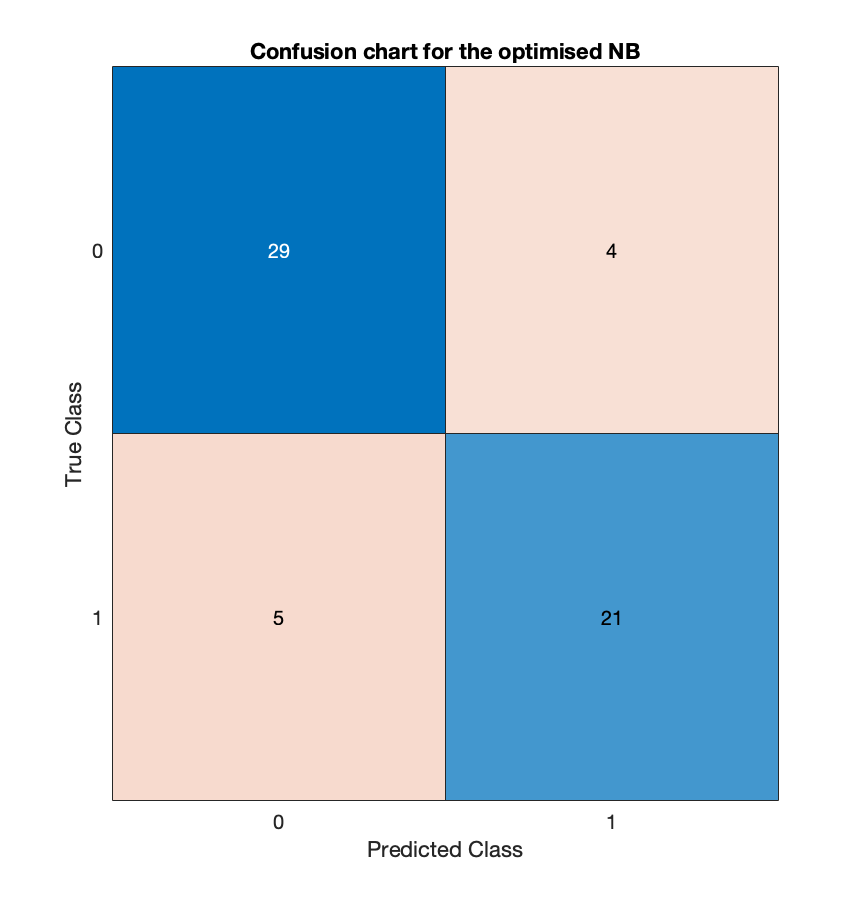

% Predicting the "target" variable using predict function where 1st output gives the predicted class/label 
% and 2nd output gives the score confidence of each class
[LabelsNB_HP,ScoresNB_HP] = predict(mdlNB_HP,dataTest);
confusionchart(dataTest.target,predict(mdlNB_HP,dataTest)); % Confusion chart for optimised model
title("Confusion chart for the optimised NB")

% Calculating the true positive (TP) , False positive (FP), True Negative (TN) , False
% Negative (FN), This will also help verify  that our confusionchart is right.
TP_NB_HP = sum(LabelsNB_HP == dataTest.target & LabelsNB_HP=="0"); %True Positive (TP)
fprintf("True positive (TP) for the optimal NB model = %d", TP_NB_HP) 

True positive (TP) for the optimal NB model = 29

TN_NB_HP = sum(LabelsNB_HP == dataTest.target & LabelsNB_HP=="1"); %  True Negative (TN)
fprintf("True Negative (TN) for the optimal NB model = %d", TN_NB_HP) 

True Negative (TN) for the optimal NB model = 21

FP_NB_HP = sum(LabelsNB_HP ~= dataTest.target & LabelsNB_HP=="0"); % False positive (FP)
fprintf("False positive (FP) for the optimal NB model = %d", FP_NB_HP) 

False positive (FP) for the optimal NB model = 5

FN_NB_HP = sum(LabelsNB_HP ~= dataTest.target & LabelsNB_HP=="1"); %  False negative (FN): 
fprintf("False negative (FN) for the optimal NB model = %d", FN_NB_HP) 

False negative (FN) for the optimal NB model = 4

% TP , TN , FP , FN used to calculate the performance metrics and verify confusionchart of optimal model
Accuracy_NB_HP = (TP_NB_HP + TN_NB_HP)/(TP_NB_HP+TN_NB_HP+FP_NB_HP+FN_NB_HP); % accuracy 
fprintf("Accuracy for the optimal NB model = %f", Accuracy_NB_HP) 

Accuracy for the optimal NB model = 0.847458

loss_NB_HP = 1 - Accuracy_NB_HP;  % loss error
fprintf("Loss (error) for the optimal NB model = %f", loss_NB_HP) 

Loss (error) for the optimal NB model = 0.152542

Precision_NB_HP = TP_NB_HP/(TP_NB_HP+FP_NB_HP); % Precision
fprintf("Precision for the optimal NB model = %f", Precision_NB_HP) 

Precision for the optimal NB model = 0.852941

recall_NB_HP = TP_NB_HP/(TP_NB_HP + FN_NB_HP); % Recall 
fprintf("Recall for the optimal NB model = %f", recall_NB_HP) 

Recall for the optimal NB model = 0.878788

Specificity_NB_HP = TN_NB_HP/(TN_NB_HP+FP_NB_HP); %Specificity
fprintf("Specificity for the optimal NB model = %f", Specificity_NB_HP)  

Specificity for the optimal NB model = 0.807692

F1Score_NB_HP =  2 * (Precision_NB_HP * recall_NB_HP)/(Precision_NB_HP + recall_NB_HP) ; %F1-score
fprintf("F1Score for the optimal NB model = %f", recall_NB_HP) 

F1Score for the optimal NB model = 0.878788

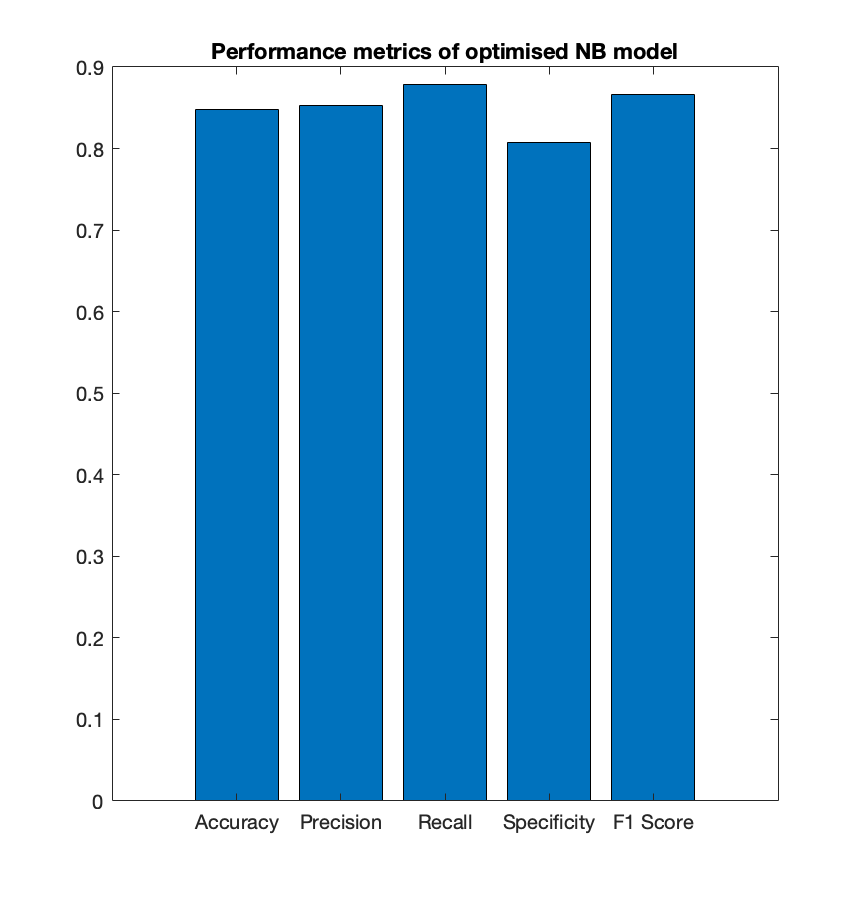

% Bar plot of the perfomance metrics: 
bar([Accuracy_NB_HP,Precision_NB_HP,recall_NB_HP,Specificity_NB_HP,F1Score_NB_HP])
title("Performance metrics of optimised NB model")
xticklabels(["Accuracy","Precision","Recall","Specificity","F1 Score"])

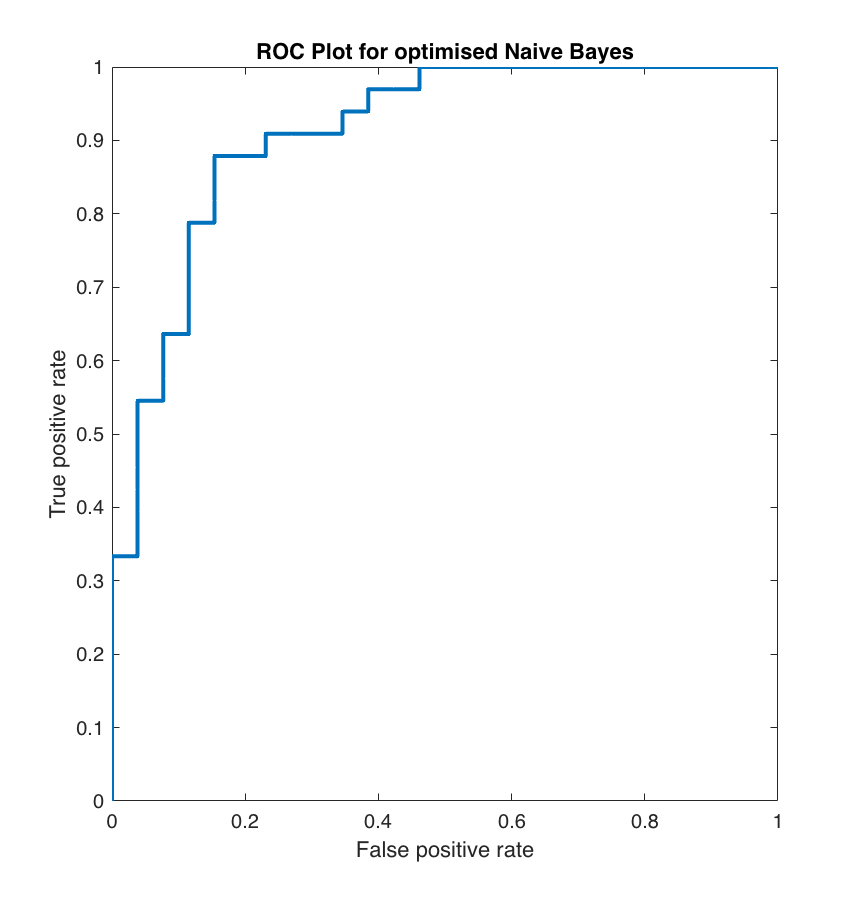

% Then use plot() function to plot ROC curve where FPR on x-axis and TPR is on y-axis
[FPRNB_HP,TPRNB_HP,~,AUC_NB_HP]=perfcurve(categorical(dataTest.target),abs(ScoresNB_HP(:,1)),categorical("0"));
plot(FPRNB_HP,TPRNB_HP,"LineWidth",2)
xlabel('False positive rate')
ylabel('True positive rate')
title('ROC Plot for optimised Naive Bayes') 

fprintf('AUC (Optimised NB) = %.3f',AUC_NB)

AUC (Optimised NB) = 0.893

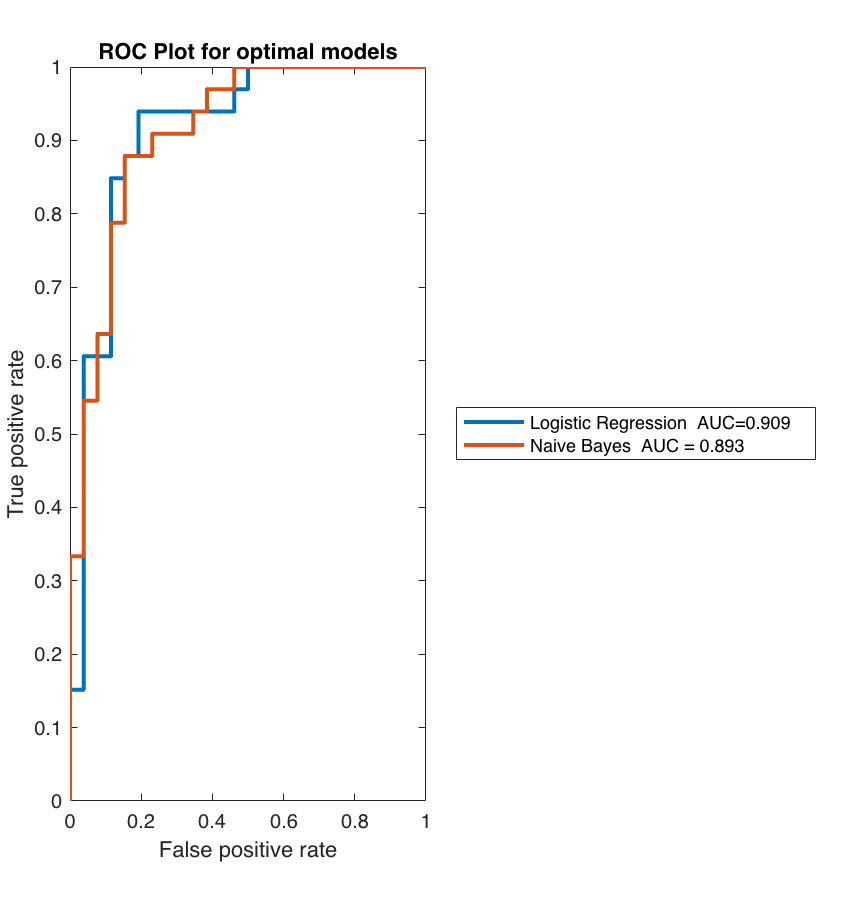

% Plot the ROC CURVE FOR OPTIMAL MODEL Logistic regression and Naive bayes together. On same figure
rng(32)
[FPRLR_HP,TPRLR_HP,~,AUC_LRHP]=perfcurve(categorical(dataTest.target),abs(Scores_LR_HP(:,1)),categorical("0"));
plot(FPRLR_HP,TPRLR_HP,"LineWidth",2) % optimal logistic regression roc curve.
hold on 
[FPRNB_HP,TPRNB_HP,~,AUC_NB_HP]=perfcurve(categorical(dataTest.target),abs(ScoresNB_HP(:,1)),categorical("0"));
plot(FPRNB_HP,TPRNB_HP,"LineWidth",2) % optimal naive bayes roc curve.
hold off
xlabel('False positive rate')
ylabel('True positive rate')
title('ROC Plot for optimal models')
legend("Logistic Regression  AUC=0.909","Naive Bayes  AUC = 0.893","Location","eastoutside") 

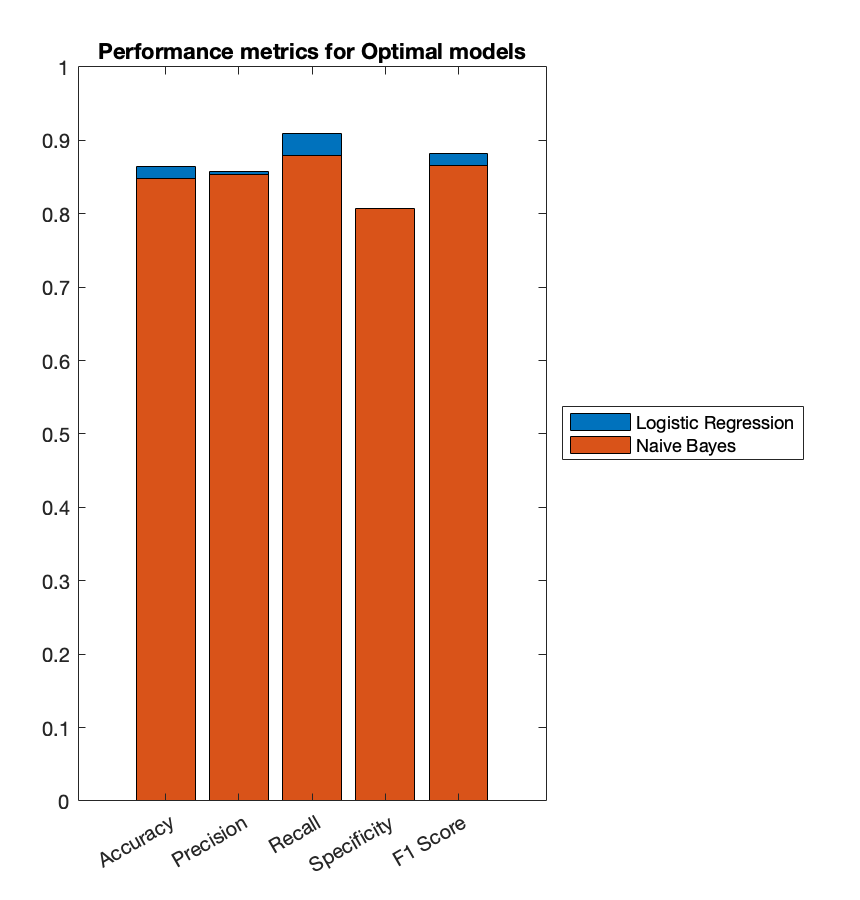

% Plot the BAR CHART OF PERFORMANCE METRICS FOR OPTIMAL MODEL Logistic
% regression and Naive bayes. on same figure.
rng(32)
bar([accuracy_LR_HP,Precision_LR_HP,recall_LR_HP,Specificity_LR_HP,F1Score_LR_HP]) % for optimised logistic regression
hold on % allow to plot on same figure 
bar([Accuracy_NB_HP,Precision_NB_HP,recall_NB_HP,Specificity_NB_HP,F1Score_NB_HP]) % For optimised naive bayes
hold off % stop other graphs plotting
xticklabels(["Accuracy","Precision","Recall","Specificity","F1 Score"])
title("Performance metrics for Optimal models")
legend("Logistic Regression","Naive Bayes","Location","eastoutside")